% clear;
% clc;
% close all;


% Constantes
mu = 3.986004418e14;
J2 = 1.082635854e-3;
R = 6378.137e3;
a = 7211.54e3;
e = 0;
n = sqrt(mu ./ a.^3);
INC     = deg2rad(45);
Omega   = deg2rad(45);
omega   = deg2rad(30);
theta_0 = deg2rad(0);

% Lapso temporal
t = linspace(0, 2*pi/n, 1e6);

% Condiciones iniciales
[posECI, velECI] = OE2ECI(mu, a, e, INC, Omega, omega, theta_0);
x0I = posECI(1);
y0I = posECI(2);
z0I = posECI(3);
dx0I = velECI(1);
dy0I = velECI(2);
dz0I = velECI(3);
x0   = 0;
y0   = 0;
z0   = 0;
dx0  = 0;
dy0  = 0;
dz0  = 0;

% Solución analítica
xB = (cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(Omega) - sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(INC).*sin(Omega)).*((640.*a.*n - 480.*a.*n.*cos(n.*t) - 2560.*a.*e.^2.*n + 3840.*a.*e.^4.*n - 2560.*a.*e.^6.*n + 640.*a.*e.^8.*n + 1920.*a.*e.^2.*n.*cos(n.*t) - 2880.*a.*e.^4.*n.*cos(n.*t) + 1920.*a.*e.^6.*n.*cos(n.*t) - 480.*a.*e.^8.*n.*cos(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*x0 + (160.*sin(n.*t).*a - 640.*sin(n.*t).*a.*e.^2 + 960.*sin(n.*t).*a.*e.^4 - 640.*sin(n.*t).*a.*e.^6 + 160.*sin(n.*t).*a.*e.^8)./(160.*a.*n.*(e.^2 - 1).^4).*dx0 + (320.*a - 320.*a.*cos(n.*t) - 1280.*a.*e.^2 + 1920.*a.*e.^4 - 1280.*a.*e.^6 + 320.*a.*e.^8 + 1280.*a.*e.^2.*cos(n.*t) - 1920.*a.*e.^4.*cos(n.*t) + 1280.*a.*e.^6.*cos(n.*t) - 320.*a.*e.^8.*cos(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*dy0 + (-(60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 120.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 960.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(160.*a.*n.*(e.^2 - 1).^4)).*t.*J2 + (-(60.*R.^2.*n - 60.*R.^2.*n.*cos(n.*t) - 30.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*cos(2.*INC + n.*t) - 90.*R.^2.*n.*cos(2.*INC - n.*t) + 180.*R.^2.*n.*cos(2.*INC) - 60.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0) - 60.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 15.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 15.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 10.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 10.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 120.*R.^2.*n.*cos(2.*omega + 2.*theta_0) + 90.*R.^2.*e.*n.*cos(- 2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 + n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 - n.*t) - 660.*R.^2.*e.^2.*n.*cos(2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*cos(2.*omega - n.*t) - 60.*R.^2.*e.*n.*cos(2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*cos(2.*omega + theta_0 - n.*t) - 40.*R.^2.*e.*n.*cos(2.*omega + theta_0 + 2.*n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - 3.*theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 25.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 80.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0) + 60.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 60.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC - theta_0 + n.*t) + 240.*R.^2.*e.^2.*n.*cos(2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega) - 70.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 - n.*t) + 40.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 2.*n.*t) - 50.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 3.*n.*t) - 120.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0) - 120.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0) - 240.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 240.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 10.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 25.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 25.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 640.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0) - 80.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0) + 330.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega + n.*t) + 330.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega - n.*t) + 30.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0 + n.*t) + 30.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 240.*R.^2.*e.*n.*cos(2.*omega + theta_0) + 480.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + n.*t) - 50.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 - n.*t) + 50.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 3.*n.*t) - 32.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 4.*n.*t) - 40.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0) - 40.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0))./(160.*a.*n.*(e.^2 - 1).^4)).*J2) - (sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(Omega) + cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(INC).*sin(Omega)).*((-(960.*a.*n.^2 - 3840.*a.*e.^2.*n.^2 + 5760.*a.*e.^4.*n.^2 - 3840.*a.*e.^6.*n.^2 + 960.*a.*e.^8.*n.^2)./(160.*a.*n.*(e.^2 - 1).^4)).*x0.*t + (960.*a.*n.*sin(n.*t) - 3840.*a.*e.^2.*n.*sin(n.*t) + 5760.*a.*e.^4.*n.*sin(n.*t) - 3840.*a.*e.^6.*n.*sin(n.*t) + 960.*a.*e.^8.*n.*sin(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*x0 + (160.*a.*n - 640.*a.*e.^2.*n + 960.*a.*e.^4.*n - 640.*a.*e.^6.*n + 160.*a.*e.^8.*n)./(160.*a.*n.*(e.^2 - 1).^4).*y0 + (-(640.*sin((n.*t)./2).^2.*a - 2560.*sin((n.*t)./2).^2.*a.*e.^2 + 3840.*sin((n.*t)./2).^2.*a.*e.^4 - 2560.*sin((n.*t)./2).^2.*a.*e.^6 + 640.*sin((n.*t)./2).^2.*a.*e.^8)./(160.*a.*n.*(e.^2 - 1).^4)).*dx0 + (-(480.*a.*n - 1920.*a.*e.^2.*n + 2880.*a.*e.^4.*n - 1920.*a.*e.^6.*n + 480.*a.*e.^8.*n)./(160.*a.*n.*(e.^2 - 1).^4)).*dy0.*t + (640.*sin(n.*t).*a - 2560.*sin(n.*t).*a.*e.^2 + 3840.*sin(n.*t).*a.*e.^4 - 2560.*sin(n.*t).*a.*e.^6 + 640.*sin(n.*t).*a.*e.^8)./(160.*a.*n.*(e.^2 - 1).^4).*dy0 + (-(720.*R.^2.*e.^2.*n.^3.*sin(2.*omega) + 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC - 2.*omega) - 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC + 2.*omega))./(160.*a.*n.*(e.^2 - 1).^4)).*t.^2.*J2 + (480.*R.^2.*n.^2 + 180.*R.^2.*n.^2.*sin(INC + omega + theta_0).^2 - 720.*R.^2.*e.*n.^2 + 180.*R.^2.*n.^2.*sin(- INC + omega + theta_0).^2 - 360.*R.^2.*n.^2.*sin(omega + theta_0).^2 - 720.*R.^2.*n.^2.*sin(INC).^2 + 360.*R.^2.*e.*n.^2.*sin(INC + omega + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(INC + omega + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(omega + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(- INC + theta_0./2 + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 360.*R.^2.*e.*n.^2.*sin(- INC + omega + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(- INC + omega + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + theta_0).^2 - 120.*R.^2.*e.^2.*n.^2.*sin(INC + omega + 2.*theta_0).^2 - 480.*R.^2.*e.^2.*n.^2.*sin(omega + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 - 720.*R.^2.*e.*n.^2.*sin(omega + theta_0./2).^2 - 240.*R.^2.*e.*n.^2.*sin(omega + (3.*theta_0)./2).^2 + 1920.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0).^2 - 240.*R.^2.*e.*n.^2.*cos(theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(INC + theta_0./2 + (n.*t)./2).^2 + 480.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0 + (n.*t)./2).^2)./(160.*a.*n.*(e.^2 - 1).^4).*t.*J2 + (140.*R.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) - 60.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 120.*R.^2.*n.*sin(n.*t) + 10.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 180.*R.^2.*n.*sin(2.*INC + n.*t) + 180.*R.^2.*n.*sin(2.*INC - n.*t) + 45.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0) + 45.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) + 30.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 70.*R.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 30.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 5.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 5.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*sin(2.*omega + 2.*theta_0) + 70.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0) + 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0) + 540.*R.^2.*e.*n.*sin(- 2.*INC + theta_0 + n.*t) + 540.*R.^2.*e.*n.*sin(2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.*sin(2.*INC + theta_0 - n.*t) - 1080.*R.^2.*e.^2.*n.*sin(2.*omega + n.*t) - 840.*R.^2.*e.^2.*n.*sin(2.*omega - n.*t) + 720.*R.^2.*e.*n.*sin(2.*INC - theta_0) - 120.*R.^2.*e.*n.*sin(2.*omega + theta_0 + n.*t) + 280.*R.^2.*e.*n.*sin(2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + theta_0 + 2.*n.*t) + 140.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 70.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + 10.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0) + 360.*R.^2.*e.*n.*sin(theta_0 + n.*t) + 120.*R.^2.*e.*n.*sin(theta_0 - n.*t) - 180.*R.^2.*e.*n.*sin(2.*INC - theta_0 + n.*t) + 1920.*R.^2.*e.^2.*n.*sin(2.*omega) + 960.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega) - 960.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega) + 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 3.*n.*t) + 90.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0) + 90.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0) - 360.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 210.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 360.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) + 10.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 320.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0) + 50.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0) - 480.*R.^2.*e.*n.*sin(theta_0) + 540.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega + n.*t) + 540.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega - n.*t) - 720.*R.^2.*e.*n.*sin(2.*INC + theta_0) + 60.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) + 60.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 - n.*t) - 10.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) - 180.*R.^2.*e.*n.*sin(2.*omega + theta_0) + 720.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) + 40.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + n.*t) + 20.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 84.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) + 14.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 4.*n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*J2) + sin(INC).*sin(Omega).*((8.*a.*n.*cos(n.*t) - 32.*a.*e.^2.*n.*cos(n.*t) + 48.*a.*e.^4.*n.*cos(n.*t) - 32.*a.*e.^6.*n.*cos(n.*t) + 8.*a.*e.^8.*n.*cos(n.*t))./(8.*a.*n.*(e.^2 - 1).^4).*z0 + (8.*sin(n.*t).*a - 32.*sin(n.*t).*a.*e.^2 + 48.*sin(n.*t).*a.*e.^4 - 32.*sin(n.*t).*a.*e.^6 + 8.*sin(n.*t).*a.*e.^8)./(8.*a.*n.*(e.^2 - 1).^4).*dz0 + (6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega))./(8.*a.*n.*(e.^2 - 1).^4).*t.*J2 + (48.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(omega).*sin(theta_0) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(omega) + 6.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(n.*t).*sin(omega) - 6.*R.^2.*e.*n.*sin(2.*INC).*sin(n.*t).*cos(omega) - 6.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 5.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) + 7.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) + 5.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*sin(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*cos(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*cos(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(3.*n.*t).*sin(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(3.*n.*t).*cos(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(3.*n.*t).*cos(omega) - 7.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 3.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(3.*n.*t).*sin(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) - 18.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*cos(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega) - 56.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) - 28.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*sin(theta_0) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(theta_0).*sin(omega) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*cos(theta_0) + 18.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*sin(omega).*sin(theta_0))./(8.*a.*n.*(e.^2 - 1).^4).*J2);
yB = (cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*sin(Omega) + sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(INC).*cos(Omega)).*((640.*a.*n - 480.*a.*n.*cos(n.*t) - 2560.*a.*e.^2.*n + 3840.*a.*e.^4.*n - 2560.*a.*e.^6.*n + 640.*a.*e.^8.*n + 1920.*a.*e.^2.*n.*cos(n.*t) - 2880.*a.*e.^4.*n.*cos(n.*t) + 1920.*a.*e.^6.*n.*cos(n.*t) - 480.*a.*e.^8.*n.*cos(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*x0 + (160.*sin(n.*t).*a - 640.*sin(n.*t).*a.*e.^2 + 960.*sin(n.*t).*a.*e.^4 - 640.*sin(n.*t).*a.*e.^6 + 160.*sin(n.*t).*a.*e.^8)./(160.*a.*n.*(e.^2 - 1).^4).*dx0 + (320.*a - 320.*a.*cos(n.*t) - 1280.*a.*e.^2 + 1920.*a.*e.^4 - 1280.*a.*e.^6 + 320.*a.*e.^8 + 1280.*a.*e.^2.*cos(n.*t) - 1920.*a.*e.^4.*cos(n.*t) + 1280.*a.*e.^6.*cos(n.*t) - 320.*a.*e.^8.*cos(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*dy0 + (-(60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 120.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 960.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(160.*a.*n.*(e.^2 - 1).^4)).*t.*J2 + (-(60.*R.^2.*n - 60.*R.^2.*n.*cos(n.*t) - 30.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*cos(2.*INC + n.*t) - 90.*R.^2.*n.*cos(2.*INC - n.*t) + 180.*R.^2.*n.*cos(2.*INC) - 60.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0) - 60.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 15.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 15.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 10.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 10.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 120.*R.^2.*n.*cos(2.*omega + 2.*theta_0) + 90.*R.^2.*e.*n.*cos(- 2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 + n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 - n.*t) - 660.*R.^2.*e.^2.*n.*cos(2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*cos(2.*omega - n.*t) - 60.*R.^2.*e.*n.*cos(2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*cos(2.*omega + theta_0 - n.*t) - 40.*R.^2.*e.*n.*cos(2.*omega + theta_0 + 2.*n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - 3.*theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 25.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 80.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0) + 60.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 60.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC - theta_0 + n.*t) + 240.*R.^2.*e.^2.*n.*cos(2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega) - 70.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 - n.*t) + 40.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 2.*n.*t) - 50.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 3.*n.*t) - 120.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0) - 120.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0) - 240.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 240.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 10.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 25.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 25.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 640.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0) - 80.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0) + 330.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega + n.*t) + 330.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega - n.*t) + 30.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0 + n.*t) + 30.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 240.*R.^2.*e.*n.*cos(2.*omega + theta_0) + 480.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + n.*t) - 50.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 - n.*t) + 50.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 3.*n.*t) - 32.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 4.*n.*t) - 40.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0) - 40.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0))./(160.*a.*n.*(e.^2 - 1).^4)).*J2) - (sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*sin(Omega) - cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(INC).*cos(Omega)).*((-(960.*a.*n.^2 - 3840.*a.*e.^2.*n.^2 + 5760.*a.*e.^4.*n.^2 - 3840.*a.*e.^6.*n.^2 + 960.*a.*e.^8.*n.^2)./(160.*a.*n.*(e.^2 - 1).^4)).*x0.*t + (960.*a.*n.*sin(n.*t) - 3840.*a.*e.^2.*n.*sin(n.*t) + 5760.*a.*e.^4.*n.*sin(n.*t) - 3840.*a.*e.^6.*n.*sin(n.*t) + 960.*a.*e.^8.*n.*sin(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*x0 + (160.*a.*n - 640.*a.*e.^2.*n + 960.*a.*e.^4.*n - 640.*a.*e.^6.*n + 160.*a.*e.^8.*n)./(160.*a.*n.*(e.^2 - 1).^4).*y0 + (-(640.*sin((n.*t)./2).^2.*a - 2560.*sin((n.*t)./2).^2.*a.*e.^2 + 3840.*sin((n.*t)./2).^2.*a.*e.^4 - 2560.*sin((n.*t)./2).^2.*a.*e.^6 + 640.*sin((n.*t)./2).^2.*a.*e.^8)./(160.*a.*n.*(e.^2 - 1).^4)).*dx0 + (-(480.*a.*n - 1920.*a.*e.^2.*n + 2880.*a.*e.^4.*n - 1920.*a.*e.^6.*n + 480.*a.*e.^8.*n)./(160.*a.*n.*(e.^2 - 1).^4)).*dy0.*t + (640.*sin(n.*t).*a - 2560.*sin(n.*t).*a.*e.^2 + 3840.*sin(n.*t).*a.*e.^4 - 2560.*sin(n.*t).*a.*e.^6 + 640.*sin(n.*t).*a.*e.^8)./(160.*a.*n.*(e.^2 - 1).^4).*dy0 + (-(720.*R.^2.*e.^2.*n.^3.*sin(2.*omega) + 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC - 2.*omega) - 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC + 2.*omega))./(160.*a.*n.*(e.^2 - 1).^4)).*t.^2.*J2 + (480.*R.^2.*n.^2 + 180.*R.^2.*n.^2.*sin(INC + omega + theta_0).^2 - 720.*R.^2.*e.*n.^2 + 180.*R.^2.*n.^2.*sin(- INC + omega + theta_0).^2 - 360.*R.^2.*n.^2.*sin(omega + theta_0).^2 - 720.*R.^2.*n.^2.*sin(INC).^2 + 360.*R.^2.*e.*n.^2.*sin(INC + omega + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(INC + omega + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(omega + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(- INC + theta_0./2 + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 360.*R.^2.*e.*n.^2.*sin(- INC + omega + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(- INC + omega + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + theta_0).^2 - 120.*R.^2.*e.^2.*n.^2.*sin(INC + omega + 2.*theta_0).^2 - 480.*R.^2.*e.^2.*n.^2.*sin(omega + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 - 720.*R.^2.*e.*n.^2.*sin(omega + theta_0./2).^2 - 240.*R.^2.*e.*n.^2.*sin(omega + (3.*theta_0)./2).^2 + 1920.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0).^2 - 240.*R.^2.*e.*n.^2.*cos(theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(INC + theta_0./2 + (n.*t)./2).^2 + 480.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0 + (n.*t)./2).^2)./(160.*a.*n.*(e.^2 - 1).^4).*t.*J2 + (140.*R.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) - 60.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 120.*R.^2.*n.*sin(n.*t) + 10.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 180.*R.^2.*n.*sin(2.*INC + n.*t) + 180.*R.^2.*n.*sin(2.*INC - n.*t) + 45.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0) + 45.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) + 30.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 70.*R.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 30.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 5.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 5.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*sin(2.*omega + 2.*theta_0) + 70.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0) + 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0) + 540.*R.^2.*e.*n.*sin(- 2.*INC + theta_0 + n.*t) + 540.*R.^2.*e.*n.*sin(2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.*sin(2.*INC + theta_0 - n.*t) - 1080.*R.^2.*e.^2.*n.*sin(2.*omega + n.*t) - 840.*R.^2.*e.^2.*n.*sin(2.*omega - n.*t) + 720.*R.^2.*e.*n.*sin(2.*INC - theta_0) - 120.*R.^2.*e.*n.*sin(2.*omega + theta_0 + n.*t) + 280.*R.^2.*e.*n.*sin(2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + theta_0 + 2.*n.*t) + 140.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 70.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + 10.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0) + 360.*R.^2.*e.*n.*sin(theta_0 + n.*t) + 120.*R.^2.*e.*n.*sin(theta_0 - n.*t) - 180.*R.^2.*e.*n.*sin(2.*INC - theta_0 + n.*t) + 1920.*R.^2.*e.^2.*n.*sin(2.*omega) + 960.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega) - 960.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega) + 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 3.*n.*t) + 90.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0) + 90.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0) - 360.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 210.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 360.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) + 10.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 320.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0) + 50.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0) - 480.*R.^2.*e.*n.*sin(theta_0) + 540.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega + n.*t) + 540.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega - n.*t) - 720.*R.^2.*e.*n.*sin(2.*INC + theta_0) + 60.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) + 60.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 - n.*t) - 10.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) - 180.*R.^2.*e.*n.*sin(2.*omega + theta_0) + 720.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) + 40.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + n.*t) + 20.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 84.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) + 14.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 4.*n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*J2) - cos(Omega).*sin(INC).*((8.*a.*n.*cos(n.*t) - 32.*a.*e.^2.*n.*cos(n.*t) + 48.*a.*e.^4.*n.*cos(n.*t) - 32.*a.*e.^6.*n.*cos(n.*t) + 8.*a.*e.^8.*n.*cos(n.*t))./(8.*a.*n.*(e.^2 - 1).^4).*z0 + (8.*sin(n.*t).*a - 32.*sin(n.*t).*a.*e.^2 + 48.*sin(n.*t).*a.*e.^4 - 32.*sin(n.*t).*a.*e.^6 + 8.*sin(n.*t).*a.*e.^8)./(8.*a.*n.*(e.^2 - 1).^4).*dz0 + (6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega))./(8.*a.*n.*(e.^2 - 1).^4).*t.*J2 + (48.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(omega).*sin(theta_0) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(omega) + 6.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(n.*t).*sin(omega) - 6.*R.^2.*e.*n.*sin(2.*INC).*sin(n.*t).*cos(omega) - 6.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 5.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) + 7.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) + 5.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*sin(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*cos(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*cos(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(3.*n.*t).*sin(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(3.*n.*t).*cos(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(3.*n.*t).*cos(omega) - 7.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 3.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(3.*n.*t).*sin(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) - 18.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*cos(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega) - 56.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) - 28.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*sin(theta_0) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(theta_0).*sin(omega) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*cos(theta_0) + 18.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*sin(omega).*sin(theta_0))./(8.*a.*n.*(e.^2 - 1).^4).*J2);
zB = cos(INC).*((8.*a.*n.*cos(n.*t) - 32.*a.*e.^2.*n.*cos(n.*t) + 48.*a.*e.^4.*n.*cos(n.*t) - 32.*a.*e.^6.*n.*cos(n.*t) + 8.*a.*e.^8.*n.*cos(n.*t))./(8.*a.*n.*(e.^2 - 1).^4).*z0 + (8.*sin(n.*t).*a - 32.*sin(n.*t).*a.*e.^2 + 48.*sin(n.*t).*a.*e.^4 - 32.*sin(n.*t).*a.*e.^6 + 8.*sin(n.*t).*a.*e.^8)./(8.*a.*n.*(e.^2 - 1).^4).*dz0 + (6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega))./(8.*a.*n.*(e.^2 - 1).^4).*t.*J2 + (48.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(omega).*sin(theta_0) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(omega) + 6.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(n.*t).*sin(omega) - 6.*R.^2.*e.*n.*sin(2.*INC).*sin(n.*t).*cos(omega) - 6.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 5.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) + 7.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) + 5.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*sin(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*cos(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*cos(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(3.*n.*t).*sin(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(3.*n.*t).*cos(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(3.*n.*t).*cos(omega) - 7.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 3.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(3.*n.*t).*sin(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) - 18.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*cos(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega) - 56.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) - 28.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*sin(theta_0) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(theta_0).*sin(omega) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*cos(theta_0) + 18.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*sin(omega).*sin(theta_0))./(8.*a.*n.*(e.^2 - 1).^4).*J2) + sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*sin(INC).*((640.*a.*n - 480.*a.*n.*cos(n.*t) - 2560.*a.*e.^2.*n + 3840.*a.*e.^4.*n - 2560.*a.*e.^6.*n + 640.*a.*e.^8.*n + 1920.*a.*e.^2.*n.*cos(n.*t) - 2880.*a.*e.^4.*n.*cos(n.*t) + 1920.*a.*e.^6.*n.*cos(n.*t) - 480.*a.*e.^8.*n.*cos(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*x0 + (160.*sin(n.*t).*a - 640.*sin(n.*t).*a.*e.^2 + 960.*sin(n.*t).*a.*e.^4 - 640.*sin(n.*t).*a.*e.^6 + 160.*sin(n.*t).*a.*e.^8)./(160.*a.*n.*(e.^2 - 1).^4).*dx0 + (320.*a - 320.*a.*cos(n.*t) - 1280.*a.*e.^2 + 1920.*a.*e.^4 - 1280.*a.*e.^6 + 320.*a.*e.^8 + 1280.*a.*e.^2.*cos(n.*t) - 1920.*a.*e.^4.*cos(n.*t) + 1280.*a.*e.^6.*cos(n.*t) - 320.*a.*e.^8.*cos(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*dy0 + (-(60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 120.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 960.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(160.*a.*n.*(e.^2 - 1).^4)).*t.*J2 + (-(60.*R.^2.*n - 60.*R.^2.*n.*cos(n.*t) - 30.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*cos(2.*INC + n.*t) - 90.*R.^2.*n.*cos(2.*INC - n.*t) + 180.*R.^2.*n.*cos(2.*INC) - 60.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0) - 60.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 15.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 15.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 10.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 10.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 120.*R.^2.*n.*cos(2.*omega + 2.*theta_0) + 90.*R.^2.*e.*n.*cos(- 2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 + n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 - n.*t) - 660.*R.^2.*e.^2.*n.*cos(2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*cos(2.*omega - n.*t) - 60.*R.^2.*e.*n.*cos(2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*cos(2.*omega + theta_0 - n.*t) - 40.*R.^2.*e.*n.*cos(2.*omega + theta_0 + 2.*n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - 3.*theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 25.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 80.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0) + 60.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 60.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC - theta_0 + n.*t) + 240.*R.^2.*e.^2.*n.*cos(2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega) - 70.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 - n.*t) + 40.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 2.*n.*t) - 50.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 3.*n.*t) - 120.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0) - 120.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0) - 240.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 240.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 10.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 25.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 25.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 640.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0) - 80.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0) + 330.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega + n.*t) + 330.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega - n.*t) + 30.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0 + n.*t) + 30.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 240.*R.^2.*e.*n.*cos(2.*omega + theta_0) + 480.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + n.*t) - 50.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 - n.*t) + 50.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 3.*n.*t) - 32.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 4.*n.*t) - 40.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0) - 40.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0))./(160.*a.*n.*(e.^2 - 1).^4)).*J2) + cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*sin(INC).*((-(960.*a.*n.^2 - 3840.*a.*e.^2.*n.^2 + 5760.*a.*e.^4.*n.^2 - 3840.*a.*e.^6.*n.^2 + 960.*a.*e.^8.*n.^2)./(160.*a.*n.*(e.^2 - 1).^4)).*x0.*t + (960.*a.*n.*sin(n.*t) - 3840.*a.*e.^2.*n.*sin(n.*t) + 5760.*a.*e.^4.*n.*sin(n.*t) - 3840.*a.*e.^6.*n.*sin(n.*t) + 960.*a.*e.^8.*n.*sin(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*x0 + (160.*a.*n - 640.*a.*e.^2.*n + 960.*a.*e.^4.*n - 640.*a.*e.^6.*n + 160.*a.*e.^8.*n)./(160.*a.*n.*(e.^2 - 1).^4).*y0 + (-(640.*sin((n.*t)./2).^2.*a - 2560.*sin((n.*t)./2).^2.*a.*e.^2 + 3840.*sin((n.*t)./2).^2.*a.*e.^4 - 2560.*sin((n.*t)./2).^2.*a.*e.^6 + 640.*sin((n.*t)./2).^2.*a.*e.^8)./(160.*a.*n.*(e.^2 - 1).^4)).*dx0 + (-(480.*a.*n - 1920.*a.*e.^2.*n + 2880.*a.*e.^4.*n - 1920.*a.*e.^6.*n + 480.*a.*e.^8.*n)./(160.*a.*n.*(e.^2 - 1).^4)).*dy0.*t + (640.*sin(n.*t).*a - 2560.*sin(n.*t).*a.*e.^2 + 3840.*sin(n.*t).*a.*e.^4 - 2560.*sin(n.*t).*a.*e.^6 + 640.*sin(n.*t).*a.*e.^8)./(160.*a.*n.*(e.^2 - 1).^4).*dy0 + (-(720.*R.^2.*e.^2.*n.^3.*sin(2.*omega) + 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC - 2.*omega) - 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC + 2.*omega))./(160.*a.*n.*(e.^2 - 1).^4)).*t.^2.*J2 + (480.*R.^2.*n.^2 + 180.*R.^2.*n.^2.*sin(INC + omega + theta_0).^2 - 720.*R.^2.*e.*n.^2 + 180.*R.^2.*n.^2.*sin(- INC + omega + theta_0).^2 - 360.*R.^2.*n.^2.*sin(omega + theta_0).^2 - 720.*R.^2.*n.^2.*sin(INC).^2 + 360.*R.^2.*e.*n.^2.*sin(INC + omega + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(INC + omega + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(omega + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(- INC + theta_0./2 + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 360.*R.^2.*e.*n.^2.*sin(- INC + omega + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(- INC + omega + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + theta_0).^2 - 120.*R.^2.*e.^2.*n.^2.*sin(INC + omega + 2.*theta_0).^2 - 480.*R.^2.*e.^2.*n.^2.*sin(omega + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 - 720.*R.^2.*e.*n.^2.*sin(omega + theta_0./2).^2 - 240.*R.^2.*e.*n.^2.*sin(omega + (3.*theta_0)./2).^2 + 1920.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0).^2 - 240.*R.^2.*e.*n.^2.*cos(theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(INC + theta_0./2 + (n.*t)./2).^2 + 480.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0 + (n.*t)./2).^2)./(160.*a.*n.*(e.^2 - 1).^4).*t.*J2 + (140.*R.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) - 60.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 120.*R.^2.*n.*sin(n.*t) + 10.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 180.*R.^2.*n.*sin(2.*INC + n.*t) + 180.*R.^2.*n.*sin(2.*INC - n.*t) + 45.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0) + 45.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) + 30.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 70.*R.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 30.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 5.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 5.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*sin(2.*omega + 2.*theta_0) + 70.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0) + 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0) + 540.*R.^2.*e.*n.*sin(- 2.*INC + theta_0 + n.*t) + 540.*R.^2.*e.*n.*sin(2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.*sin(2.*INC + theta_0 - n.*t) - 1080.*R.^2.*e.^2.*n.*sin(2.*omega + n.*t) - 840.*R.^2.*e.^2.*n.*sin(2.*omega - n.*t) + 720.*R.^2.*e.*n.*sin(2.*INC - theta_0) - 120.*R.^2.*e.*n.*sin(2.*omega + theta_0 + n.*t) + 280.*R.^2.*e.*n.*sin(2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + theta_0 + 2.*n.*t) + 140.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 70.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + 10.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0) + 360.*R.^2.*e.*n.*sin(theta_0 + n.*t) + 120.*R.^2.*e.*n.*sin(theta_0 - n.*t) - 180.*R.^2.*e.*n.*sin(2.*INC - theta_0 + n.*t) + 1920.*R.^2.*e.^2.*n.*sin(2.*omega) + 960.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega) - 960.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega) + 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 3.*n.*t) + 90.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0) + 90.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0) - 360.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 210.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 360.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) + 10.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 320.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0) + 50.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0) - 480.*R.^2.*e.*n.*sin(theta_0) + 540.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega + n.*t) + 540.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega - n.*t) - 720.*R.^2.*e.*n.*sin(2.*INC + theta_0) + 60.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) + 60.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 - n.*t) - 10.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) - 180.*R.^2.*e.*n.*sin(2.*omega + theta_0) + 720.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) + 40.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + n.*t) + 20.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 84.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) + 14.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 4.*n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*J2);
xdotB = (cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(Omega) - sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(INC).*sin(Omega)).*((480.*a.*n.^2.*sin(n.*t) - 1920.*a.*e.^2.*n.^2.*sin(n.*t) + 2880.*a.*e.^4.*n.^2.*sin(n.*t) - 1920.*a.*e.^6.*n.^2.*sin(n.*t) + 480.*a.*e.^8.*n.^2.*sin(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*x0 + (160.*a.*n.*cos(n.*t) - 640.*a.*e.^2.*n.*cos(n.*t) + 960.*a.*e.^4.*n.*cos(n.*t) - 640.*a.*e.^6.*n.*cos(n.*t) + 160.*a.*e.^8.*n.*cos(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*dx0 + (320.*a.*n.*sin(n.*t) - 1280.*a.*e.^2.*n.*sin(n.*t) + 1920.*a.*e.^4.*n.*sin(n.*t) - 1280.*a.*e.^6.*n.*sin(n.*t) + 320.*a.*e.^8.*n.*sin(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*dy0 + (-(60.*R.^2.*e.^2.*n.^3.*cos(- 2.*INC + 2.*omega + n.*t) + 60.*R.^2.*e.^2.*n.^3.*cos(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^3.*cos(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^3.*cos(- 2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.^3.*cos(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^3.*cos(2.*omega + n.*t) + 120.*R.^2.*e.*n.^3.*cos(theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^3.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^3.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t))./(160.*a.*n.*(e.^2 - 1).^4)).*t.*J2 + ((15.*R.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 15.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 35.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 20.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 60.*R.^2.*n.^2.*sin(n.*t) - 30.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 70.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) - 40.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.^2.*sin(2.*INC + n.*t) + 90.*R.^2.*n.^2.*sin(2.*INC - n.*t) - 240.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 240.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 105.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 10.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 21.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 75.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 75.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 21.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 75.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 75.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 64.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 64.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 330.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega + n.*t) + 330.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 210.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega - n.*t) + 30.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) + 30.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 70.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 - n.*t) + 40.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 40.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) - 210.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + n.*t) - 150.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 42.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 - n.*t) + 150.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) - 128.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 4.*n.*t) + 90.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 - n.*t) - 660.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) - 420.*R.^2.*e.^2.*n.^2.*sin(2.*omega - n.*t) - 60.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + n.*t) + 140.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 - n.*t) - 80.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + 2.*n.*t) + 70.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 35.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 35.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) - 40.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 40.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 75.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 75.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 - n.*t) - 90.*R.^2.*e.*n.^2.*sin(2.*INC - theta_0 + n.*t) + 70.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 - n.*t) + 80.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + 2.*n.*t) - 150.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + 3.*n.*t))./(160.*a.*n.*(e.^2 - 1).^4) - (60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 120.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 960.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(160.*a.*n.*(e.^2 - 1).^4)).*J2) - (sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(Omega) + cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(INC).*sin(Omega)).*((-(480.*a.*n.*sin((n.*t)./2).^2 - 1920.*a.*e.^2.*n.*sin((n.*t)./2).^2 + 2880.*a.*e.^4.*n.*sin((n.*t)./2).^2 - 1920.*a.*e.^6.*n.*sin((n.*t)./2).^2 + 480.*a.*e.^8.*n.*sin((n.*t)./2).^2)./(40.*a.*(e.^2 - 1).^4)).*x0 + (-(80.*sin(n.*t).*a - 320.*sin(n.*t).*a.*e.^2 + 480.*sin(n.*t).*a.*e.^4 - 320.*sin(n.*t).*a.*e.^6 + 80.*sin(n.*t).*a.*e.^8)./(40.*a.*(e.^2 - 1).^4)).*dx0 + (40.*a - 160.*a.*e.^2 + 240.*a.*e.^4 - 160.*a.*e.^6 + 40.*a.*e.^8 - 320.*a.*sin((n.*t)./2).^2 + 1280.*a.*e.^2.*sin((n.*t)./2).^2 - 1920.*a.*e.^4.*sin((n.*t)./2).^2 + 1280.*a.*e.^6.*sin((n.*t)./2).^2 - 320.*a.*e.^8.*sin((n.*t)./2).^2)./(40.*a.*(e.^2 - 1).^4).*dy0 + (30.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 30.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 360.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 180.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 180.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(40.*a.*(e.^2 - 1).^4).*t.*J2 + (5.*R.^2.*n.*sin(INC + omega + theta_0 + n.*t).^2 - 35.*R.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 - 15.*R.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 90.*R.^2.*n.*sin(INC - (n.*t)./2).^2 + 90.*R.^2.*n.*sin(INC + (n.*t)./2).^2 + 45.*R.^2.*n.*sin(- INC + omega + theta_0).^2 + 5.*R.^2.*n.*sin(- INC + omega + theta_0 + n.*t).^2 - 15.*R.^2.*n.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 60.*R.^2.*n.*sin((n.*t)./2).^2 - 90.*R.^2.*n.*sin(omega + theta_0).^2 - 180.*R.^2.*n.*sin(INC).^2 - 10.*R.^2.*n.*sin(omega + theta_0 + n.*t).^2 + 70.*R.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 + 30.*R.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 + 45.*R.^2.*n.*sin(INC + omega + theta_0).^2 - 35.*R.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2).^2 + 30.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0).^2 - 30.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0).^2 - 420.*R.^2.*e.^2.*n.*sin(omega - (n.*t)./2).^2 + 420.*R.^2.*e.^2.*n.*sin(omega + (n.*t)./2).^2 + 10.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2 + n.*t).^2 - 10.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2 + n.*t).^2 - 70.*R.^2.*e.*n.*sin(INC - omega - theta_0./2 + (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2 + (n.*t)./2).^2 - 35.*R.^2.*e.*n.*sin(INC - omega - (3.*theta_0)./2 + (n.*t)./2).^2 + 15.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + 2.*n.*t).^2 + 120.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 21.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 - (n.*t)./2).^2 + 10.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (n.*t)./2).^2 + 15.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0 + (3.*n.*t)./2).^2 - 15.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 - 180.*R.^2.*e.*n.*sin(omega + theta_0./2).^2 - 60.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2).^2 + 480.*R.^2.*e.^2.*n.*sin(omega + theta_0).^2 + 30.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 30.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 30.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0).^2 + 210.*R.^2.*e.^2.*n.*sin(INC + omega - (n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(INC + omega + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC - theta_0./2 + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC + theta_0./2 - (n.*t)./2).^2 - 90.*R.^2.*e.*n.*sin(INC + theta_0./2 + (n.*t)./2).^2 - 20.*R.^2.*e.*n.*sin(omega + theta_0./2 + n.*t).^2 + 20.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + n.*t).^2 + 140.*R.^2.*e.*n.*sin(omega + theta_0./2 - (n.*t)./2).^2 + 60.*R.^2.*e.*n.*sin(omega + theta_0./2 + (n.*t)./2).^2 + 70.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 - (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 - 30.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (3.*n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC + omega + theta_0./2).^2 + 30.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0).^2 + 105.*R.^2.*e.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + 2.*n.*t).^2 + 21.*R.^2.*e.^2.*n.*sin(INC - omega - 2.*theta_0 + (n.*t)./2).^2 + 10.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + (n.*t)./2).^2 - 15.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 + 60.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0).^2 + 210.*R.^2.*e.^2.*n.*sin(INC - omega + (n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(- INC + omega + (n.*t)./2).^2 - 90.*R.^2.*e.*n.*sin(- INC + theta_0./2 + (n.*t)./2).^2 + 10.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + n.*t).^2 - 10.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + n.*t).^2 - 70.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 - (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + (n.*t)./2).^2 - 35.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 - (n.*t)./2).^2 + 15.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 + 105.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 + 120.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 15.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (3.*n.*t)./2).^2 - 28.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + 2.*n.*t).^2 - 42.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 - (n.*t)./2).^2 - 20.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (n.*t)./2).^2 + 30.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (3.*n.*t)./2).^2)./(40.*a.*(e.^2 - 1).^4).*J2) - sin(INC).*sin(Omega).*(- (-(8.*a.*n.^2.*sin(n.*t) - 32.*a.*e.^2.*n.^2.*sin(n.*t) + 48.*a.*e.^4.*n.^2.*sin(n.*t) - 32.*a.*e.^6.*n.^2.*sin(n.*t) + 8.*a.*e.^8.*n.^2.*sin(n.*t))./(8.*a.*n.*(e.^2 - 1).^4)).*z0 - (8.*a.*n.*cos(n.*t) - 32.*a.*e.^2.*n.*cos(n.*t) + 48.*a.*e.^4.*n.*cos(n.*t) - 32.*a.*e.^6.*n.*cos(n.*t) + 8.*a.*e.^8.*n.*cos(n.*t))./(8.*a.*n.*(e.^2 - 1).^4).*dz0 - (-(6.*R.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 6.*R.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 6.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) + 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0))./(8.*a.*n.*(e.^2 - 1).^4)).*t.*J2 - ((6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega))./(8.*a.*n.*(e.^2 - 1).^4) - (6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) + 18.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) - 24.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*cos(omega) + 28.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*cos(theta_0) - 12.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 18.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) - 12.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 24.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 24.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 24.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*cos(omega) - 4.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 56.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(2.*n.*t).*sin(omega).*sin(theta_0) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*sin(theta_0) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(2.*n.*t).*cos(theta_0).*sin(omega) - 7.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*cos(omega) - 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(3.*n.*t).*cos(omega) + 5.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) + 7.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) + 5.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*sin(omega) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*cos(omega) + 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(3.*n.*t).*sin(omega) + 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(3.*n.*t).*sin(omega) + 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(3.*n.*t).*cos(omega))./(8.*a.*n.*(e.^2 - 1).^4)).*J2);
ydotB = (cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*sin(Omega) + sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(INC).*cos(Omega)).*((480.*a.*n.^2.*sin(n.*t) - 1920.*a.*e.^2.*n.^2.*sin(n.*t) + 2880.*a.*e.^4.*n.^2.*sin(n.*t) - 1920.*a.*e.^6.*n.^2.*sin(n.*t) + 480.*a.*e.^8.*n.^2.*sin(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*x0 + (160.*a.*n.*cos(n.*t) - 640.*a.*e.^2.*n.*cos(n.*t) + 960.*a.*e.^4.*n.*cos(n.*t) - 640.*a.*e.^6.*n.*cos(n.*t) + 160.*a.*e.^8.*n.*cos(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*dx0 + (320.*a.*n.*sin(n.*t) - 1280.*a.*e.^2.*n.*sin(n.*t) + 1920.*a.*e.^4.*n.*sin(n.*t) - 1280.*a.*e.^6.*n.*sin(n.*t) + 320.*a.*e.^8.*n.*sin(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*dy0 + (-(60.*R.^2.*e.^2.*n.^3.*cos(- 2.*INC + 2.*omega + n.*t) + 60.*R.^2.*e.^2.*n.^3.*cos(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^3.*cos(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^3.*cos(- 2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.^3.*cos(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^3.*cos(2.*omega + n.*t) + 120.*R.^2.*e.*n.^3.*cos(theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^3.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^3.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t))./(160.*a.*n.*(e.^2 - 1).^4)).*t.*J2 + ((15.*R.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 15.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 35.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 20.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 60.*R.^2.*n.^2.*sin(n.*t) - 30.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 70.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) - 40.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.^2.*sin(2.*INC + n.*t) + 90.*R.^2.*n.^2.*sin(2.*INC - n.*t) - 240.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 240.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 105.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 10.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 21.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 75.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 75.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 21.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 75.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 75.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 64.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 64.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 330.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega + n.*t) + 330.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 210.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega - n.*t) + 30.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) + 30.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 70.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 - n.*t) + 40.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 40.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) - 210.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + n.*t) - 150.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 42.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 - n.*t) + 150.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) - 128.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 4.*n.*t) + 90.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 - n.*t) - 660.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) - 420.*R.^2.*e.^2.*n.^2.*sin(2.*omega - n.*t) - 60.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + n.*t) + 140.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 - n.*t) - 80.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + 2.*n.*t) + 70.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 35.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 35.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) - 40.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 40.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 75.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 75.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 - n.*t) - 90.*R.^2.*e.*n.^2.*sin(2.*INC - theta_0 + n.*t) + 70.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 - n.*t) + 80.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + 2.*n.*t) - 150.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + 3.*n.*t))./(160.*a.*n.*(e.^2 - 1).^4) - (60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 120.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 960.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(160.*a.*n.*(e.^2 - 1).^4)).*J2) - (sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*sin(Omega) - cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(INC).*cos(Omega)).*((-(480.*a.*n.*sin((n.*t)./2).^2 - 1920.*a.*e.^2.*n.*sin((n.*t)./2).^2 + 2880.*a.*e.^4.*n.*sin((n.*t)./2).^2 - 1920.*a.*e.^6.*n.*sin((n.*t)./2).^2 + 480.*a.*e.^8.*n.*sin((n.*t)./2).^2)./(40.*a.*(e.^2 - 1).^4)).*x0 + (-(80.*sin(n.*t).*a - 320.*sin(n.*t).*a.*e.^2 + 480.*sin(n.*t).*a.*e.^4 - 320.*sin(n.*t).*a.*e.^6 + 80.*sin(n.*t).*a.*e.^8)./(40.*a.*(e.^2 - 1).^4)).*dx0 + (40.*a - 160.*a.*e.^2 + 240.*a.*e.^4 - 160.*a.*e.^6 + 40.*a.*e.^8 - 320.*a.*sin((n.*t)./2).^2 + 1280.*a.*e.^2.*sin((n.*t)./2).^2 - 1920.*a.*e.^4.*sin((n.*t)./2).^2 + 1280.*a.*e.^6.*sin((n.*t)./2).^2 - 320.*a.*e.^8.*sin((n.*t)./2).^2)./(40.*a.*(e.^2 - 1).^4).*dy0 + (30.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 30.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 360.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 180.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 180.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(40.*a.*(e.^2 - 1).^4).*t.*J2 + (5.*R.^2.*n.*sin(INC + omega + theta_0 + n.*t).^2 - 35.*R.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 - 15.*R.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 90.*R.^2.*n.*sin(INC - (n.*t)./2).^2 + 90.*R.^2.*n.*sin(INC + (n.*t)./2).^2 + 45.*R.^2.*n.*sin(- INC + omega + theta_0).^2 + 5.*R.^2.*n.*sin(- INC + omega + theta_0 + n.*t).^2 - 15.*R.^2.*n.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 60.*R.^2.*n.*sin((n.*t)./2).^2 - 90.*R.^2.*n.*sin(omega + theta_0).^2 - 180.*R.^2.*n.*sin(INC).^2 - 10.*R.^2.*n.*sin(omega + theta_0 + n.*t).^2 + 70.*R.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 + 30.*R.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 + 45.*R.^2.*n.*sin(INC + omega + theta_0).^2 - 35.*R.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2).^2 + 30.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0).^2 - 30.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0).^2 - 420.*R.^2.*e.^2.*n.*sin(omega - (n.*t)./2).^2 + 420.*R.^2.*e.^2.*n.*sin(omega + (n.*t)./2).^2 + 10.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2 + n.*t).^2 - 10.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2 + n.*t).^2 - 70.*R.^2.*e.*n.*sin(INC - omega - theta_0./2 + (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2 + (n.*t)./2).^2 - 35.*R.^2.*e.*n.*sin(INC - omega - (3.*theta_0)./2 + (n.*t)./2).^2 + 15.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + 2.*n.*t).^2 + 120.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 21.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 - (n.*t)./2).^2 + 10.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (n.*t)./2).^2 + 15.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0 + (3.*n.*t)./2).^2 - 15.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 - 180.*R.^2.*e.*n.*sin(omega + theta_0./2).^2 - 60.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2).^2 + 480.*R.^2.*e.^2.*n.*sin(omega + theta_0).^2 + 30.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 30.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 30.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0).^2 + 210.*R.^2.*e.^2.*n.*sin(INC + omega - (n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(INC + omega + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC - theta_0./2 + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC + theta_0./2 - (n.*t)./2).^2 - 90.*R.^2.*e.*n.*sin(INC + theta_0./2 + (n.*t)./2).^2 - 20.*R.^2.*e.*n.*sin(omega + theta_0./2 + n.*t).^2 + 20.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + n.*t).^2 + 140.*R.^2.*e.*n.*sin(omega + theta_0./2 - (n.*t)./2).^2 + 60.*R.^2.*e.*n.*sin(omega + theta_0./2 + (n.*t)./2).^2 + 70.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 - (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 - 30.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (3.*n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC + omega + theta_0./2).^2 + 30.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0).^2 + 105.*R.^2.*e.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + 2.*n.*t).^2 + 21.*R.^2.*e.^2.*n.*sin(INC - omega - 2.*theta_0 + (n.*t)./2).^2 + 10.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + (n.*t)./2).^2 - 15.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 + 60.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0).^2 + 210.*R.^2.*e.^2.*n.*sin(INC - omega + (n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(- INC + omega + (n.*t)./2).^2 - 90.*R.^2.*e.*n.*sin(- INC + theta_0./2 + (n.*t)./2).^2 + 10.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + n.*t).^2 - 10.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + n.*t).^2 - 70.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 - (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + (n.*t)./2).^2 - 35.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 - (n.*t)./2).^2 + 15.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 + 105.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 + 120.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 15.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (3.*n.*t)./2).^2 - 28.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + 2.*n.*t).^2 - 42.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 - (n.*t)./2).^2 - 20.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (n.*t)./2).^2 + 30.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (3.*n.*t)./2).^2)./(40.*a.*(e.^2 - 1).^4).*J2) + cos(Omega).*sin(INC).*(- (-(8.*a.*n.^2.*sin(n.*t) - 32.*a.*e.^2.*n.^2.*sin(n.*t) + 48.*a.*e.^4.*n.^2.*sin(n.*t) - 32.*a.*e.^6.*n.^2.*sin(n.*t) + 8.*a.*e.^8.*n.^2.*sin(n.*t))./(8.*a.*n.*(e.^2 - 1).^4)).*z0 - (8.*a.*n.*cos(n.*t) - 32.*a.*e.^2.*n.*cos(n.*t) + 48.*a.*e.^4.*n.*cos(n.*t) - 32.*a.*e.^6.*n.*cos(n.*t) + 8.*a.*e.^8.*n.*cos(n.*t))./(8.*a.*n.*(e.^2 - 1).^4).*dz0 - (-(6.*R.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 6.*R.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 6.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) + 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0))./(8.*a.*n.*(e.^2 - 1).^4)).*t.*J2 - ((6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega))./(8.*a.*n.*(e.^2 - 1).^4) - (6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) + 18.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) - 24.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*cos(omega) + 28.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*cos(theta_0) - 12.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 18.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) - 12.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 24.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 24.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 24.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*cos(omega) - 4.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 56.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(2.*n.*t).*sin(omega).*sin(theta_0) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*sin(theta_0) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(2.*n.*t).*cos(theta_0).*sin(omega) - 7.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*cos(omega) - 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(3.*n.*t).*cos(omega) + 5.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) + 7.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) + 5.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*sin(omega) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*cos(omega) + 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(3.*n.*t).*sin(omega) + 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(3.*n.*t).*sin(omega) + 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(3.*n.*t).*cos(omega))./(8.*a.*n.*(e.^2 - 1).^4)).*J2);
zdotB = - cos(INC).*(- (-(8.*a.*n.^2.*sin(n.*t) - 32.*a.*e.^2.*n.^2.*sin(n.*t) + 48.*a.*e.^4.*n.^2.*sin(n.*t) - 32.*a.*e.^6.*n.^2.*sin(n.*t) + 8.*a.*e.^8.*n.^2.*sin(n.*t))./(8.*a.*n.*(e.^2 - 1).^4)).*z0 - (8.*a.*n.*cos(n.*t) - 32.*a.*e.^2.*n.*cos(n.*t) + 48.*a.*e.^4.*n.*cos(n.*t) - 32.*a.*e.^6.*n.*cos(n.*t) + 8.*a.*e.^8.*n.*cos(n.*t))./(8.*a.*n.*(e.^2 - 1).^4).*dz0 - (-(6.*R.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 6.*R.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 6.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) + 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0))./(8.*a.*n.*(e.^2 - 1).^4)).*t.*J2 - ((6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega))./(8.*a.*n.*(e.^2 - 1).^4) - (6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) + 18.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) - 24.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*cos(omega) + 28.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*cos(theta_0) - 12.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 18.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) - 12.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 24.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 24.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 24.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*cos(omega) - 4.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 56.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(2.*n.*t).*sin(omega).*sin(theta_0) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*sin(theta_0) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(2.*n.*t).*cos(theta_0).*sin(omega) - 7.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*cos(omega) - 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(3.*n.*t).*cos(omega) + 5.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) + 7.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) + 5.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*sin(omega) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*cos(omega) + 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(3.*n.*t).*sin(omega) + 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(3.*n.*t).*sin(omega) + 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(3.*n.*t).*cos(omega))./(8.*a.*n.*(e.^2 - 1).^4)).*J2) + cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*sin(INC).*((-(480.*a.*n.*sin((n.*t)./2).^2 - 1920.*a.*e.^2.*n.*sin((n.*t)./2).^2 + 2880.*a.*e.^4.*n.*sin((n.*t)./2).^2 - 1920.*a.*e.^6.*n.*sin((n.*t)./2).^2 + 480.*a.*e.^8.*n.*sin((n.*t)./2).^2)./(40.*a.*(e.^2 - 1).^4)).*x0 + (-(80.*sin(n.*t).*a - 320.*sin(n.*t).*a.*e.^2 + 480.*sin(n.*t).*a.*e.^4 - 320.*sin(n.*t).*a.*e.^6 + 80.*sin(n.*t).*a.*e.^8)./(40.*a.*(e.^2 - 1).^4)).*dx0 + (40.*a - 160.*a.*e.^2 + 240.*a.*e.^4 - 160.*a.*e.^6 + 40.*a.*e.^8 - 320.*a.*sin((n.*t)./2).^2 + 1280.*a.*e.^2.*sin((n.*t)./2).^2 - 1920.*a.*e.^4.*sin((n.*t)./2).^2 + 1280.*a.*e.^6.*sin((n.*t)./2).^2 - 320.*a.*e.^8.*sin((n.*t)./2).^2)./(40.*a.*(e.^2 - 1).^4).*dy0 + (30.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 30.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 360.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 180.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 180.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(40.*a.*(e.^2 - 1).^4).*t.*J2 + (5.*R.^2.*n.*sin(INC + omega + theta_0 + n.*t).^2 - 35.*R.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 - 15.*R.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 90.*R.^2.*n.*sin(INC - (n.*t)./2).^2 + 90.*R.^2.*n.*sin(INC + (n.*t)./2).^2 + 45.*R.^2.*n.*sin(- INC + omega + theta_0).^2 + 5.*R.^2.*n.*sin(- INC + omega + theta_0 + n.*t).^2 - 15.*R.^2.*n.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 60.*R.^2.*n.*sin((n.*t)./2).^2 - 90.*R.^2.*n.*sin(omega + theta_0).^2 - 180.*R.^2.*n.*sin(INC).^2 - 10.*R.^2.*n.*sin(omega + theta_0 + n.*t).^2 + 70.*R.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 + 30.*R.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 + 45.*R.^2.*n.*sin(INC + omega + theta_0).^2 - 35.*R.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2).^2 + 30.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0).^2 - 30.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0).^2 - 420.*R.^2.*e.^2.*n.*sin(omega - (n.*t)./2).^2 + 420.*R.^2.*e.^2.*n.*sin(omega + (n.*t)./2).^2 + 10.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2 + n.*t).^2 - 10.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2 + n.*t).^2 - 70.*R.^2.*e.*n.*sin(INC - omega - theta_0./2 + (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2 + (n.*t)./2).^2 - 35.*R.^2.*e.*n.*sin(INC - omega - (3.*theta_0)./2 + (n.*t)./2).^2 + 15.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + 2.*n.*t).^2 + 120.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 21.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 - (n.*t)./2).^2 + 10.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (n.*t)./2).^2 + 15.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0 + (3.*n.*t)./2).^2 - 15.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 - 180.*R.^2.*e.*n.*sin(omega + theta_0./2).^2 - 60.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2).^2 + 480.*R.^2.*e.^2.*n.*sin(omega + theta_0).^2 + 30.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 30.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 30.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0).^2 + 210.*R.^2.*e.^2.*n.*sin(INC + omega - (n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(INC + omega + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC - theta_0./2 + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC + theta_0./2 - (n.*t)./2).^2 - 90.*R.^2.*e.*n.*sin(INC + theta_0./2 + (n.*t)./2).^2 - 20.*R.^2.*e.*n.*sin(omega + theta_0./2 + n.*t).^2 + 20.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + n.*t).^2 + 140.*R.^2.*e.*n.*sin(omega + theta_0./2 - (n.*t)./2).^2 + 60.*R.^2.*e.*n.*sin(omega + theta_0./2 + (n.*t)./2).^2 + 70.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 - (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 - 30.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (3.*n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC + omega + theta_0./2).^2 + 30.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0).^2 + 105.*R.^2.*e.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + 2.*n.*t).^2 + 21.*R.^2.*e.^2.*n.*sin(INC - omega - 2.*theta_0 + (n.*t)./2).^2 + 10.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + (n.*t)./2).^2 - 15.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 + 60.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0).^2 + 210.*R.^2.*e.^2.*n.*sin(INC - omega + (n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(- INC + omega + (n.*t)./2).^2 - 90.*R.^2.*e.*n.*sin(- INC + theta_0./2 + (n.*t)./2).^2 + 10.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + n.*t).^2 - 10.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + n.*t).^2 - 70.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 - (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + (n.*t)./2).^2 - 35.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 - (n.*t)./2).^2 + 15.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 + 105.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 + 120.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 15.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (3.*n.*t)./2).^2 - 28.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + 2.*n.*t).^2 - 42.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 - (n.*t)./2).^2 - 20.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (n.*t)./2).^2 + 30.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (3.*n.*t)./2).^2)./(40.*a.*(e.^2 - 1).^4).*J2) + sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*sin(INC).*((480.*a.*n.^2.*sin(n.*t) - 1920.*a.*e.^2.*n.^2.*sin(n.*t) + 2880.*a.*e.^4.*n.^2.*sin(n.*t) - 1920.*a.*e.^6.*n.^2.*sin(n.*t) + 480.*a.*e.^8.*n.^2.*sin(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*x0 + (160.*a.*n.*cos(n.*t) - 640.*a.*e.^2.*n.*cos(n.*t) + 960.*a.*e.^4.*n.*cos(n.*t) - 640.*a.*e.^6.*n.*cos(n.*t) + 160.*a.*e.^8.*n.*cos(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*dx0 + (320.*a.*n.*sin(n.*t) - 1280.*a.*e.^2.*n.*sin(n.*t) + 1920.*a.*e.^4.*n.*sin(n.*t) - 1280.*a.*e.^6.*n.*sin(n.*t) + 320.*a.*e.^8.*n.*sin(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*dy0 + (-(60.*R.^2.*e.^2.*n.^3.*cos(- 2.*INC + 2.*omega + n.*t) + 60.*R.^2.*e.^2.*n.^3.*cos(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^3.*cos(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^3.*cos(- 2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.^3.*cos(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^3.*cos(2.*omega + n.*t) + 120.*R.^2.*e.*n.^3.*cos(theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^3.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^3.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t))./(160.*a.*n.*(e.^2 - 1).^4)).*t.*J2 + ((15.*R.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 15.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 35.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 20.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 60.*R.^2.*n.^2.*sin(n.*t) - 30.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 70.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) - 40.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.^2.*sin(2.*INC + n.*t) + 90.*R.^2.*n.^2.*sin(2.*INC - n.*t) - 240.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 240.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 105.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 10.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 21.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 75.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 75.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 21.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 75.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 75.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 64.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 64.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 330.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega + n.*t) + 330.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 210.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega - n.*t) + 30.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) + 30.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 70.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 - n.*t) + 40.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 40.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) - 210.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + n.*t) - 150.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 42.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 - n.*t) + 150.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) - 128.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 4.*n.*t) + 90.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 - n.*t) - 660.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) - 420.*R.^2.*e.^2.*n.^2.*sin(2.*omega - n.*t) - 60.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + n.*t) + 140.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 - n.*t) - 80.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + 2.*n.*t) + 70.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 35.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 35.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) - 40.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 40.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 75.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 75.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 - n.*t) - 90.*R.^2.*e.*n.^2.*sin(2.*INC - theta_0 + n.*t) + 70.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 - n.*t) + 80.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + 2.*n.*t) - 150.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + 3.*n.*t))./(160.*a.*n.*(e.^2 - 1).^4) - (60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 120.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 960.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(160.*a.*n.*(e.^2 - 1).^4)).*J2);

xCil = (3.*J2.*R.^2.*sin(INC).^2.*sin(Omega).*(12.*cos(INC).*sin(omega + theta_0 - n.*t) - 12.*cos(INC).*sin(omega + theta_0 + n.*t) + 4.*cos(INC).*sin(3.*omega + 3.*theta_0 + n.*t) - 2.*cos(INC).*sin(3.*omega + 3.*theta_0 - n.*t) - 2.*cos(INC).*sin(3.*omega + 3.*theta_0 + 3.*n.*t) + 24.*cos(INC).*cos(Omega).^2.*sin(omega + theta_0 + n.*t) - 24.*cos(INC).*cos(Omega).^2.*sin(omega + theta_0 - n.*t) - 6.*cos(INC).*cos(Omega).^4.*sin(omega + theta_0 + n.*t) + 6.*cos(INC).*cos(Omega).^4.*sin(omega + theta_0 - n.*t) - 6.*cos(Omega).^3.*sin(Omega).*cos(omega + theta_0 + n.*t) + 6.*cos(Omega).^3.*sin(Omega).*cos(omega + theta_0 - n.*t) + 6.*cos(INC).^3.*cos(Omega).^2.*sin(3.*omega + 3.*theta_0 + n.*t) - 3.*cos(INC).^3.*cos(Omega).^2.*sin(3.*omega + 3.*theta_0 - n.*t) - 2.*cos(INC).^3.*cos(Omega).^4.*sin(3.*omega + 3.*theta_0 + n.*t) - 3.*cos(INC).^3.*cos(Omega).^2.*sin(3.*omega + 3.*theta_0 + 3.*n.*t) + cos(INC).^3.*cos(Omega).^4.*sin(3.*omega + 3.*theta_0 - n.*t) + cos(INC).^3.*cos(Omega).^4.*sin(3.*omega + 3.*theta_0 + 3.*n.*t) - 18.*cos(INC).^3.*cos(Omega).^2.*sin(omega + theta_0 + n.*t) + 18.*cos(INC).^3.*cos(Omega).^2.*sin(omega + theta_0 - n.*t) + 6.*cos(INC).^3.*cos(Omega).^4.*sin(omega + theta_0 + n.*t) - 6.*cos(INC).^3.*cos(Omega).^4.*sin(omega + theta_0 - n.*t) - 8.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(Omega).*sin(Omega) + 4.*cos(3.*omega + 3.*theta_0 - n.*t).*cos(Omega).*sin(Omega) + 4.*cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(Omega).*sin(Omega) + 8.*cos(Omega).*sin(Omega).*cos(omega + theta_0 + n.*t) - 8.*cos(Omega).*sin(Omega).*cos(omega + theta_0 - n.*t) - 8.*cos(INC).*cos(Omega).^2.*sin(3.*omega + 3.*theta_0 + n.*t) + 4.*cos(INC).*cos(Omega).^2.*sin(3.*omega + 3.*theta_0 - n.*t) - 6.*cos(INC).*cos(Omega).^4.*sin(3.*omega + 3.*theta_0 + n.*t) + 4.*cos(INC).*cos(Omega).^2.*sin(3.*omega + 3.*theta_0 + 3.*n.*t) + 3.*cos(INC).*cos(Omega).^4.*sin(3.*omega + 3.*theta_0 - n.*t) + 3.*cos(INC).*cos(Omega).^4.*sin(3.*omega + 3.*theta_0 + 3.*n.*t) - 2.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(Omega).^3.*sin(Omega) + cos(3.*omega + 3.*theta_0 - n.*t).*cos(Omega).^3.*sin(Omega) + cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(Omega).^3.*sin(Omega) + 6.*cos(INC).^2.*cos(Omega).^3.*sin(Omega).*cos(omega + theta_0 + n.*t) - 6.*cos(INC).^2.*cos(Omega).^3.*sin(Omega).*cos(omega + theta_0 - n.*t) + 2.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(INC).^2.*cos(Omega).*sin(Omega) - cos(3.*omega + 3.*theta_0 - n.*t).*cos(INC).^2.*cos(Omega).*sin(Omega) - cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(INC).^2.*cos(Omega).*sin(Omega) - 2.*cos(INC).^2.*cos(Omega).*sin(Omega).*cos(omega + theta_0 + n.*t) + 2.*cos(INC).^2.*cos(Omega).*sin(Omega).*cos(omega + theta_0 - n.*t) + 24.*n.*t.*cos(INC).*cos(omega + theta_0 + n.*t) - 6.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(INC).^2.*cos(Omega).^3.*sin(Omega) + 3.*cos(3.*omega + 3.*theta_0 - n.*t).*cos(INC).^2.*cos(Omega).^3.*sin(Omega) + 3.*cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(INC).^2.*cos(Omega).^3.*sin(Omega) - 12.*n.*t.*cos(Omega).^3.*sin(Omega).*sin(omega + theta_0 + n.*t) + 36.*n.*t.*cos(INC).^3.*cos(Omega).^2.*cos(omega + theta_0 + n.*t) - 12.*n.*t.*cos(INC).^3.*cos(Omega).^4.*cos(omega + theta_0 + n.*t) + 16.*n.*t.*cos(Omega).*sin(Omega).*sin(omega + theta_0 + n.*t) - 48.*n.*t.*cos(INC).*cos(Omega).^2.*cos(omega + theta_0 + n.*t) + 12.*n.*t.*cos(INC).*cos(Omega).^4.*cos(omega + theta_0 + n.*t) + 12.*n.*t.*cos(INC).^2.*cos(Omega).^3.*sin(Omega).*sin(omega + theta_0 + n.*t) - 4.*n.*t.*cos(INC).^2.*cos(Omega).*sin(Omega).*sin(omega + theta_0 + n.*t)))./(64.*a) - (J2.*R.^2.*sin(J2.*((945.*R.^2.*sin(2.*omega + 2.*theta_0))./(8192.*a.^2) - (1785.*R.^2.*sin(2.*theta_0))./(512.*a.^2) - (1785.*R.^2.*sin(2.*omega))./(512.*a.^2) - (2167.*R.^2.*sin(n.*t))./(256.*a.^2) + (595.*R.^2.*sin(2.*n.*t))./(512.*a.^2) + (81.*R.^2.*sin(omega + theta_0))./(1024.*a.^2) - (945.*R.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(8192.*a.^2) - (81.*R.^2.*sin(omega + theta_0 + n.*t))./(1024.*a.^2) - (243.*R.^2.*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (81.*R.^2.*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (345.*R.^2.*sin(2.*omega).*cos(INC).^2)./(64.*a.^2) + (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2)./(64.*a.^2) + (39.*R.^2.*sin(2.*omega).*cos(Omega).^2)./(32.*a.^2) + (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2)./(32.*a.^2) - (405.*R.^2.*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (405.*R.^2.*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (1785.*R.^2.*sin(2.*omega).*cos(theta_0).^2)./(256.*a.^2) + (1785.*R.^2.*sin(2.*theta_0).*cos(omega).^2)./(256.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) + (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) - (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (243.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (81.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (81.*R.^2.*cos(4.*INC).*sin(n.*t))./(256.*a.^2) + (409.*R.^2.*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0))./(32.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0))./(64.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (27.*R.^2.*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) + (121.*R.^2.*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) - (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0))./(8.*a.^2) + (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) + (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) - (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (21.*R.^2.*sin(2.*Omega).*cos(INC))./(16.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(omega).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(theta_0).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) - (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0 + n.*t))./(32.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0 + n.*t))./(8.*a.^2) - (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0 + n.*t))./(32.*a.^2) - (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (21.*R.^2.*cos(3.*INC).*sin(2.*Omega))./(16.*a.^2) - (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^4)./(64.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^4)./(256.*a.^2) + (119.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (595.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) - (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (21.*R.^2.*sin(2.*Omega).*cos(n.*t).*cos(INC))./(16.*a.^2) + (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (345.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (39.*R.^2.*sin(2.*omega).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) - (21.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(n.*t))./(16.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(n.*t))./(32.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) - (21.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) + (9.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (3.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(64.*a.^2) + (9.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (21.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(256.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(theta_0).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(32.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(16.*a.^2) - (9.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (9.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (21.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(theta_0).^2)./(64.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(omega).^2)./(64.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega).^2)./(256.*a.^2) - (119.*R.^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(128.*a.^2) - (5.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(4.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2.*cos(omega).^2)./(4.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) + (22.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (69.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(64.*a.^2) + (15.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(128.*a.^2) + (15.*R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(128.*a.^2) + (105.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (23.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t))./(4.*a.^2) + (115.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (11.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (13.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) + (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(4.*n.*t))./(256.*a.^2) - (69.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) - (15.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(128.*a.^2) - (15.*R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) - (105.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(512.*a.^2) - (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) + (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(1024.*a.^2) - (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(16.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) - (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(2048.*a.^2) + (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(128.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(512.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(128.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(8.*a.^2) + (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(4.*a.^2) - (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(1024.*a.^2) + (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(16.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) + (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(64.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(256.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(2048.*a.^2) + (6.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./a.^2 + (6.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./a.^2 - (9.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(theta_0).^2)./(8.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(omega).^2)./(8.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(16.*a.^2) + (R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(16.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (12.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (12.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 + (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (36.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (6.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 - (3.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) - (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(4.*n.*t))./(32.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) + (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2)) + J2.*t.^2.*((21.*R.^2.*n.^2.*sin(2.*Omega).*cos(INC))./(32.*a.^2) - (21.*R.^2.*n.^2.*cos(3.*INC).*sin(2.*Omega))./(32.*a.^2) + (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).*sin(Omega./2))./(2.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).*sin(Omega./2))./a.^2 - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC).^2)./(2.*a.^2) + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC))./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (42.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC).^2)./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC))./(2.*a.^2)) - J2.*t.*((483.*R.^2.*n)./(4096.*a.^2) - (135.*R.^2.*n.*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (201.*R.^2.*n.*cos(2.*INC))./(64.*a.^2) - (81.*R.^2.*n.*cos(4.*INC))./(256.*a.^2) - (729.*R.^2.*n.*exp(-INC.*2i))./(2048.*a.^2) - (729.*R.^2.*n.*exp(INC.*2i))./(2048.*a.^2) + (81.*R.^2.*n.*exp(-INC.*4i))./(8192.*a.^2) + (81.*R.^2.*n.*exp(INC.*4i))./(8192.*a.^2) + (21.*R.^2.*n.*cos(2.*Omega))./(32.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega))./(256.*a.^2) + (99.*R.^2.*n.*exp(-Omega.*2i))./(1024.*a.^2) + (99.*R.^2.*n.*exp(Omega.*2i))./(1024.*a.^2) - (1755.*R.^2.*n.*exp(-Omega.*4i))./(8192.*a.^2) - (1755.*R.^2.*n.*exp(Omega.*4i))./(8192.*a.^2) + (27.*R.^2.*n.*cos(omega + theta_0))./(32.*a.^2) + (81.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./a.^2 - (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (135.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega))./(128.*a.^2) - (423.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega))./(1024.*a.^2) - (135.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega))./(512.*a.^2) + (135.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega))./(4096.*a.^2) + (135.*R.^2.*n.*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) + (81.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) - (135.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (81.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) + (6.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./a.^2 + (51.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./a.^2 - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (15.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (15.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(32.*a.^2) - (27.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(16.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(2.*a.^2) - (27.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./a.^2 + (63.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./(4.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(32.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(32.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(16.*a.^2) - (9.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(2.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./a.^2 + (9.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(2.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2))).*(sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*cos(Omega) + cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*cos(INC).*sin(Omega)).*(3216.*cos(2.*INC) - 324.*cos(4.*INC) + 672.*cos(2.*Omega) + 108.*cos(4.*Omega) + 588.*cos(n.*t) - 3216.*cos(2.*INC).*cos(n.*t) + 324.*cos(4.*INC).*cos(n.*t) - 672.*cos(2.*Omega).*cos(n.*t) - 108.*cos(4.*Omega).*cos(n.*t) - 384.*cos(2.*INC).*cos(2.*Omega) - 144.*cos(2.*INC).*cos(4.*Omega) - 288.*cos(4.*INC).*cos(2.*Omega) + 36.*cos(4.*INC).*cos(4.*Omega) + 540.*cos(2.*omega).*cos(2.*theta_0) + 81.*cos(4.*omega).*cos(4.*theta_0) - 540.*sin(2.*omega).*sin(2.*theta_0) - 81.*sin(4.*omega).*sin(4.*theta_0) + 384.*cos(2.*INC).*cos(2.*Omega).*cos(n.*t) + 144.*cos(2.*INC).*cos(4.*Omega).*cos(n.*t) + 288.*cos(4.*INC).*cos(2.*Omega).*cos(n.*t) - 36.*cos(4.*INC).*cos(4.*Omega).*cos(n.*t) - 1344.*cos(3.*INC).*sin(2.*Omega).*sin(n.*t) + 352.*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 892.*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 108.*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 27.*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 1784.*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1784.*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 352.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 892.*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 892.*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 892.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 108.*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 108.*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 108.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 27.*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 27.*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 27.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 432.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0) - 108.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0) - 108.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0) + 27.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0) + 864.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 60.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 120.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 105.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 1344.*sin(2.*Omega).*cos(INC).*sin(n.*t) + 432.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0) + 108.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0) + 108.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0) - 27.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0) - 864.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 60.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 120.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 105.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 1536.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 864.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0) + 864.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega) - 48.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 96.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) - 48.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0) - 48.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega) - 96.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 12.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) - 96.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0) - 96.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega) + 84.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 24.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 24.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0) + 24.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega) + 3.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 1344.*n.*t.*sin(2.*Omega).*cos(INC) + 1344.*n.*t.*cos(3.*INC).*sin(2.*Omega) - 640.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 1072.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 288.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 144.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 180.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 36.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 36.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 9.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 512.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 352.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 160.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 160.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 100.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 140.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 40.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 35.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 2144.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 2144.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 640.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1072.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 1072.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 1072.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 360.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 360.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 288.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 144.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 144.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 144.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 180.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 180.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 180.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 36.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 36.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 36.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 36.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 36.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 36.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 9.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 9.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 9.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 704.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 704.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 512.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 352.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 352.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 352.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 200.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 200.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 160.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 160.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 160.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 160.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 100.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 100.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 100.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 140.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 140.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 140.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 40.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 40.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 40.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 35.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 35.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 35.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 96.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC) - 96.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC) + 48.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC) + 48.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC) + 96.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC) + 96.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC) + 168.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC) + 168.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) + 48.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 96.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) + 96.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 12.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 84.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 24.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 3.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 1472.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 640.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 640.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) + 736.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 736.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 736.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) - 160.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 128.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 128.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) - 128.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) - 128.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) - 128.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC) + 80.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 80.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 80.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) - 224.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) - 224.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) - 224.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC) + 32.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 32.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 32.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC) + 56.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 56.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 56.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC) + 1472.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 736.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 160.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) + 128.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 80.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 224.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 32.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) - 56.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 2304.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 128.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 256.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 32.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 2304.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1088.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 1408.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1408.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 160.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 128.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 320.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 320.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 256.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 160.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 128.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 40.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 40.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 32.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 1088.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 544.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 160.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 128.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 80.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 32.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 8.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 588))./(2048.*a) - (J2.*R.^2.*cos(J2.*((945.*R.^2.*sin(2.*omega + 2.*theta_0))./(8192.*a.^2) - (1785.*R.^2.*sin(2.*theta_0))./(512.*a.^2) - (1785.*R.^2.*sin(2.*omega))./(512.*a.^2) - (2167.*R.^2.*sin(n.*t))./(256.*a.^2) + (595.*R.^2.*sin(2.*n.*t))./(512.*a.^2) + (81.*R.^2.*sin(omega + theta_0))./(1024.*a.^2) - (945.*R.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(8192.*a.^2) - (81.*R.^2.*sin(omega + theta_0 + n.*t))./(1024.*a.^2) - (243.*R.^2.*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (81.*R.^2.*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (345.*R.^2.*sin(2.*omega).*cos(INC).^2)./(64.*a.^2) + (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2)./(64.*a.^2) + (39.*R.^2.*sin(2.*omega).*cos(Omega).^2)./(32.*a.^2) + (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2)./(32.*a.^2) - (405.*R.^2.*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (405.*R.^2.*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (1785.*R.^2.*sin(2.*omega).*cos(theta_0).^2)./(256.*a.^2) + (1785.*R.^2.*sin(2.*theta_0).*cos(omega).^2)./(256.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) + (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) - (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (243.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (81.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (81.*R.^2.*cos(4.*INC).*sin(n.*t))./(256.*a.^2) + (409.*R.^2.*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0))./(32.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0))./(64.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (27.*R.^2.*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) + (121.*R.^2.*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) - (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0))./(8.*a.^2) + (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) + (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) - (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (21.*R.^2.*sin(2.*Omega).*cos(INC))./(16.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(omega).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(theta_0).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) - (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0 + n.*t))./(32.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0 + n.*t))./(8.*a.^2) - (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0 + n.*t))./(32.*a.^2) - (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (21.*R.^2.*cos(3.*INC).*sin(2.*Omega))./(16.*a.^2) - (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^4)./(64.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^4)./(256.*a.^2) + (119.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (595.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) - (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (21.*R.^2.*sin(2.*Omega).*cos(n.*t).*cos(INC))./(16.*a.^2) + (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (345.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (39.*R.^2.*sin(2.*omega).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) - (21.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(n.*t))./(16.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(n.*t))./(32.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) - (21.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) + (9.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (3.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(64.*a.^2) + (9.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (21.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(256.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(theta_0).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(32.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(16.*a.^2) - (9.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (9.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (21.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(theta_0).^2)./(64.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(omega).^2)./(64.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega).^2)./(256.*a.^2) - (119.*R.^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(128.*a.^2) - (5.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(4.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2.*cos(omega).^2)./(4.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) + (22.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (69.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(64.*a.^2) + (15.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(128.*a.^2) + (15.*R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(128.*a.^2) + (105.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (23.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t))./(4.*a.^2) + (115.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (11.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (13.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) + (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(4.*n.*t))./(256.*a.^2) - (69.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) - (15.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(128.*a.^2) - (15.*R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) - (105.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(512.*a.^2) - (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) + (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(1024.*a.^2) - (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(16.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) - (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(2048.*a.^2) + (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(128.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(512.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(128.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(8.*a.^2) + (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(4.*a.^2) - (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(1024.*a.^2) + (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(16.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) + (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(64.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(256.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(2048.*a.^2) + (6.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./a.^2 + (6.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./a.^2 - (9.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(theta_0).^2)./(8.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(omega).^2)./(8.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(16.*a.^2) + (R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(16.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (12.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (12.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 + (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (36.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (6.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 - (3.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) - (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(4.*n.*t))./(32.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) + (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2)) + J2.*t.^2.*((21.*R.^2.*n.^2.*sin(2.*Omega).*cos(INC))./(32.*a.^2) - (21.*R.^2.*n.^2.*cos(3.*INC).*sin(2.*Omega))./(32.*a.^2) + (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).*sin(Omega./2))./(2.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).*sin(Omega./2))./a.^2 - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC).^2)./(2.*a.^2) + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC))./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (42.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC).^2)./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC))./(2.*a.^2)) - J2.*t.*((483.*R.^2.*n)./(4096.*a.^2) - (135.*R.^2.*n.*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (201.*R.^2.*n.*cos(2.*INC))./(64.*a.^2) - (81.*R.^2.*n.*cos(4.*INC))./(256.*a.^2) - (729.*R.^2.*n.*exp(-INC.*2i))./(2048.*a.^2) - (729.*R.^2.*n.*exp(INC.*2i))./(2048.*a.^2) + (81.*R.^2.*n.*exp(-INC.*4i))./(8192.*a.^2) + (81.*R.^2.*n.*exp(INC.*4i))./(8192.*a.^2) + (21.*R.^2.*n.*cos(2.*Omega))./(32.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega))./(256.*a.^2) + (99.*R.^2.*n.*exp(-Omega.*2i))./(1024.*a.^2) + (99.*R.^2.*n.*exp(Omega.*2i))./(1024.*a.^2) - (1755.*R.^2.*n.*exp(-Omega.*4i))./(8192.*a.^2) - (1755.*R.^2.*n.*exp(Omega.*4i))./(8192.*a.^2) + (27.*R.^2.*n.*cos(omega + theta_0))./(32.*a.^2) + (81.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./a.^2 - (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (135.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega))./(128.*a.^2) - (423.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega))./(1024.*a.^2) - (135.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega))./(512.*a.^2) + (135.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega))./(4096.*a.^2) + (135.*R.^2.*n.*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) + (81.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) - (135.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (81.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) + (6.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./a.^2 + (51.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./a.^2 - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (15.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (15.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(32.*a.^2) - (27.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(16.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(2.*a.^2) - (27.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./a.^2 + (63.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./(4.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(32.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(32.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(16.*a.^2) - (9.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(2.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./a.^2 + (9.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(2.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2))).*(cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*cos(Omega) - sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*cos(INC).*sin(Omega)).*(3216.*cos(2.*INC) - 324.*cos(4.*INC) + 672.*cos(2.*Omega) + 108.*cos(4.*Omega) + 588.*cos(n.*t) - 3216.*cos(2.*INC).*cos(n.*t) + 324.*cos(4.*INC).*cos(n.*t) - 672.*cos(2.*Omega).*cos(n.*t) - 108.*cos(4.*Omega).*cos(n.*t) - 384.*cos(2.*INC).*cos(2.*Omega) - 144.*cos(2.*INC).*cos(4.*Omega) - 288.*cos(4.*INC).*cos(2.*Omega) + 36.*cos(4.*INC).*cos(4.*Omega) + 540.*cos(2.*omega).*cos(2.*theta_0) + 81.*cos(4.*omega).*cos(4.*theta_0) - 540.*sin(2.*omega).*sin(2.*theta_0) - 81.*sin(4.*omega).*sin(4.*theta_0) + 384.*cos(2.*INC).*cos(2.*Omega).*cos(n.*t) + 144.*cos(2.*INC).*cos(4.*Omega).*cos(n.*t) + 288.*cos(4.*INC).*cos(2.*Omega).*cos(n.*t) - 36.*cos(4.*INC).*cos(4.*Omega).*cos(n.*t) - 1344.*cos(3.*INC).*sin(2.*Omega).*sin(n.*t) + 352.*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 892.*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 108.*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 27.*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 1784.*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1784.*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 352.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 892.*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 892.*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 892.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 108.*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 108.*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 108.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 27.*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 27.*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 27.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 432.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0) - 108.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0) - 108.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0) + 27.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0) + 864.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 60.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 120.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 105.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 1344.*sin(2.*Omega).*cos(INC).*sin(n.*t) + 432.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0) + 108.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0) + 108.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0) - 27.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0) - 864.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 60.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 120.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 105.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 1536.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 864.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0) + 864.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega) - 48.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 96.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) - 48.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0) - 48.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega) - 96.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 12.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) - 96.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0) - 96.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega) + 84.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 24.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 24.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0) + 24.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega) + 3.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 1344.*n.*t.*sin(2.*Omega).*cos(INC) + 1344.*n.*t.*cos(3.*INC).*sin(2.*Omega) - 640.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 1072.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 288.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 144.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 180.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 36.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 36.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 9.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 512.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 352.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 160.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 160.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 100.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 140.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 40.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 35.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 2144.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 2144.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 640.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1072.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 1072.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 1072.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 360.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 360.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 288.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 144.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 144.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 144.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 180.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 180.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 180.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 36.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 36.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 36.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 36.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 36.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 36.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 9.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 9.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 9.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 704.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 704.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 512.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 352.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 352.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 352.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 200.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 200.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 160.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 160.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 160.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 160.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 100.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 100.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 100.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 140.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 140.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 140.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 40.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 40.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 40.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 35.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 35.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 35.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 96.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC) - 96.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC) + 48.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC) + 48.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC) + 96.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC) + 96.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC) + 168.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC) + 168.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) + 48.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 96.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) + 96.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 12.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 84.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 24.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 3.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 1472.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 640.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 640.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) + 736.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 736.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 736.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) - 160.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 128.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 128.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) - 128.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) - 128.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) - 128.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC) + 80.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 80.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 80.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) - 224.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) - 224.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) - 224.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC) + 32.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 32.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 32.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC) + 56.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 56.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 56.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC) + 1472.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 736.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 160.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) + 128.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 80.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 224.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 32.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) - 56.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 2304.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 128.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 256.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 32.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 2304.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1088.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 1408.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1408.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 160.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 128.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 320.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 320.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 256.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 160.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 128.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 40.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 40.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 32.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 1088.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 544.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 160.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 128.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 80.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 32.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 8.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 588))./(2048.*a);
yCil = - (J2.*R.^2.*cos(J2.*((945.*R.^2.*sin(2.*omega + 2.*theta_0))./(8192.*a.^2) - (1785.*R.^2.*sin(2.*theta_0))./(512.*a.^2) - (1785.*R.^2.*sin(2.*omega))./(512.*a.^2) - (2167.*R.^2.*sin(n.*t))./(256.*a.^2) + (595.*R.^2.*sin(2.*n.*t))./(512.*a.^2) + (81.*R.^2.*sin(omega + theta_0))./(1024.*a.^2) - (945.*R.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(8192.*a.^2) - (81.*R.^2.*sin(omega + theta_0 + n.*t))./(1024.*a.^2) - (243.*R.^2.*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (81.*R.^2.*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (345.*R.^2.*sin(2.*omega).*cos(INC).^2)./(64.*a.^2) + (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2)./(64.*a.^2) + (39.*R.^2.*sin(2.*omega).*cos(Omega).^2)./(32.*a.^2) + (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2)./(32.*a.^2) - (405.*R.^2.*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (405.*R.^2.*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (1785.*R.^2.*sin(2.*omega).*cos(theta_0).^2)./(256.*a.^2) + (1785.*R.^2.*sin(2.*theta_0).*cos(omega).^2)./(256.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) + (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) - (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (243.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (81.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (81.*R.^2.*cos(4.*INC).*sin(n.*t))./(256.*a.^2) + (409.*R.^2.*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0))./(32.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0))./(64.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (27.*R.^2.*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) + (121.*R.^2.*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) - (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0))./(8.*a.^2) + (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) + (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) - (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (21.*R.^2.*sin(2.*Omega).*cos(INC))./(16.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(omega).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(theta_0).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) - (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0 + n.*t))./(32.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0 + n.*t))./(8.*a.^2) - (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0 + n.*t))./(32.*a.^2) - (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (21.*R.^2.*cos(3.*INC).*sin(2.*Omega))./(16.*a.^2) - (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^4)./(64.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^4)./(256.*a.^2) + (119.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (595.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) - (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (21.*R.^2.*sin(2.*Omega).*cos(n.*t).*cos(INC))./(16.*a.^2) + (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (345.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (39.*R.^2.*sin(2.*omega).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) - (21.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(n.*t))./(16.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(n.*t))./(32.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) - (21.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) + (9.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (3.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(64.*a.^2) + (9.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (21.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(256.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(theta_0).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(32.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(16.*a.^2) - (9.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (9.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (21.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(theta_0).^2)./(64.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(omega).^2)./(64.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega).^2)./(256.*a.^2) - (119.*R.^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(128.*a.^2) - (5.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(4.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2.*cos(omega).^2)./(4.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) + (22.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (69.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(64.*a.^2) + (15.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(128.*a.^2) + (15.*R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(128.*a.^2) + (105.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (23.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t))./(4.*a.^2) + (115.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (11.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (13.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) + (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(4.*n.*t))./(256.*a.^2) - (69.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) - (15.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(128.*a.^2) - (15.*R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) - (105.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(512.*a.^2) - (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) + (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(1024.*a.^2) - (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(16.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) - (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(2048.*a.^2) + (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(128.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(512.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(128.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(8.*a.^2) + (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(4.*a.^2) - (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(1024.*a.^2) + (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(16.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) + (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(64.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(256.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(2048.*a.^2) + (6.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./a.^2 + (6.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./a.^2 - (9.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(theta_0).^2)./(8.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(omega).^2)./(8.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(16.*a.^2) + (R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(16.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (12.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (12.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 + (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (36.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (6.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 - (3.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) - (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(4.*n.*t))./(32.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) + (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2)) + J2.*t.^2.*((21.*R.^2.*n.^2.*sin(2.*Omega).*cos(INC))./(32.*a.^2) - (21.*R.^2.*n.^2.*cos(3.*INC).*sin(2.*Omega))./(32.*a.^2) + (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).*sin(Omega./2))./(2.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).*sin(Omega./2))./a.^2 - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC).^2)./(2.*a.^2) + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC))./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (42.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC).^2)./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC))./(2.*a.^2)) - J2.*t.*((483.*R.^2.*n)./(4096.*a.^2) - (135.*R.^2.*n.*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (201.*R.^2.*n.*cos(2.*INC))./(64.*a.^2) - (81.*R.^2.*n.*cos(4.*INC))./(256.*a.^2) - (729.*R.^2.*n.*exp(-INC.*2i))./(2048.*a.^2) - (729.*R.^2.*n.*exp(INC.*2i))./(2048.*a.^2) + (81.*R.^2.*n.*exp(-INC.*4i))./(8192.*a.^2) + (81.*R.^2.*n.*exp(INC.*4i))./(8192.*a.^2) + (21.*R.^2.*n.*cos(2.*Omega))./(32.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega))./(256.*a.^2) + (99.*R.^2.*n.*exp(-Omega.*2i))./(1024.*a.^2) + (99.*R.^2.*n.*exp(Omega.*2i))./(1024.*a.^2) - (1755.*R.^2.*n.*exp(-Omega.*4i))./(8192.*a.^2) - (1755.*R.^2.*n.*exp(Omega.*4i))./(8192.*a.^2) + (27.*R.^2.*n.*cos(omega + theta_0))./(32.*a.^2) + (81.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./a.^2 - (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (135.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega))./(128.*a.^2) - (423.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega))./(1024.*a.^2) - (135.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega))./(512.*a.^2) + (135.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega))./(4096.*a.^2) + (135.*R.^2.*n.*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) + (81.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) - (135.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (81.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) + (6.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./a.^2 + (51.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./a.^2 - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (15.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (15.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(32.*a.^2) - (27.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(16.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(2.*a.^2) - (27.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./a.^2 + (63.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./(4.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(32.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(32.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(16.*a.^2) - (9.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(2.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./a.^2 + (9.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(2.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2))).*(cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*sin(Omega) + sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*cos(INC).*cos(Omega)).*(3216.*cos(2.*INC) - 324.*cos(4.*INC) + 672.*cos(2.*Omega) + 108.*cos(4.*Omega) + 588.*cos(n.*t) - 3216.*cos(2.*INC).*cos(n.*t) + 324.*cos(4.*INC).*cos(n.*t) - 672.*cos(2.*Omega).*cos(n.*t) - 108.*cos(4.*Omega).*cos(n.*t) - 384.*cos(2.*INC).*cos(2.*Omega) - 144.*cos(2.*INC).*cos(4.*Omega) - 288.*cos(4.*INC).*cos(2.*Omega) + 36.*cos(4.*INC).*cos(4.*Omega) + 540.*cos(2.*omega).*cos(2.*theta_0) + 81.*cos(4.*omega).*cos(4.*theta_0) - 540.*sin(2.*omega).*sin(2.*theta_0) - 81.*sin(4.*omega).*sin(4.*theta_0) + 384.*cos(2.*INC).*cos(2.*Omega).*cos(n.*t) + 144.*cos(2.*INC).*cos(4.*Omega).*cos(n.*t) + 288.*cos(4.*INC).*cos(2.*Omega).*cos(n.*t) - 36.*cos(4.*INC).*cos(4.*Omega).*cos(n.*t) - 1344.*cos(3.*INC).*sin(2.*Omega).*sin(n.*t) + 352.*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 892.*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 108.*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 27.*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 1784.*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1784.*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 352.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 892.*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 892.*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 892.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 108.*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 108.*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 108.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 27.*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 27.*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 27.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 432.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0) - 108.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0) - 108.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0) + 27.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0) + 864.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 60.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 120.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 105.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 1344.*sin(2.*Omega).*cos(INC).*sin(n.*t) + 432.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0) + 108.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0) + 108.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0) - 27.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0) - 864.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 60.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 120.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 105.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 1536.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 864.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0) + 864.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega) - 48.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 96.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) - 48.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0) - 48.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega) - 96.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 12.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) - 96.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0) - 96.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega) + 84.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 24.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 24.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0) + 24.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega) + 3.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 1344.*n.*t.*sin(2.*Omega).*cos(INC) + 1344.*n.*t.*cos(3.*INC).*sin(2.*Omega) - 640.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 1072.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 288.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 144.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 180.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 36.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 36.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 9.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 512.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 352.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 160.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 160.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 100.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 140.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 40.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 35.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 2144.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 2144.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 640.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1072.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 1072.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 1072.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 360.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 360.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 288.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 144.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 144.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 144.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 180.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 180.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 180.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 36.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 36.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 36.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 36.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 36.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 36.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 9.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 9.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 9.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 704.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 704.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 512.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 352.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 352.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 352.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 200.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 200.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 160.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 160.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 160.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 160.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 100.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 100.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 100.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 140.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 140.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 140.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 40.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 40.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 40.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 35.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 35.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 35.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 96.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC) - 96.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC) + 48.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC) + 48.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC) + 96.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC) + 96.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC) + 168.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC) + 168.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) + 48.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 96.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) + 96.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 12.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 84.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 24.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 3.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 1472.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 640.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 640.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) + 736.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 736.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 736.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) - 160.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 128.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 128.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) - 128.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) - 128.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) - 128.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC) + 80.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 80.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 80.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) - 224.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) - 224.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) - 224.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC) + 32.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 32.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 32.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC) + 56.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 56.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 56.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC) + 1472.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 736.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 160.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) + 128.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 80.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 224.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 32.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) - 56.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 2304.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 128.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 256.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 32.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 2304.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1088.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 1408.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1408.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 160.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 128.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 320.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 320.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 256.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 160.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 128.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 40.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 40.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 32.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 1088.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 544.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 160.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 128.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 80.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 32.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 8.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 588))./(2048.*a) - (J2.*R.^2.*sin(J2.*((945.*R.^2.*sin(2.*omega + 2.*theta_0))./(8192.*a.^2) - (1785.*R.^2.*sin(2.*theta_0))./(512.*a.^2) - (1785.*R.^2.*sin(2.*omega))./(512.*a.^2) - (2167.*R.^2.*sin(n.*t))./(256.*a.^2) + (595.*R.^2.*sin(2.*n.*t))./(512.*a.^2) + (81.*R.^2.*sin(omega + theta_0))./(1024.*a.^2) - (945.*R.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(8192.*a.^2) - (81.*R.^2.*sin(omega + theta_0 + n.*t))./(1024.*a.^2) - (243.*R.^2.*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (81.*R.^2.*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (345.*R.^2.*sin(2.*omega).*cos(INC).^2)./(64.*a.^2) + (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2)./(64.*a.^2) + (39.*R.^2.*sin(2.*omega).*cos(Omega).^2)./(32.*a.^2) + (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2)./(32.*a.^2) - (405.*R.^2.*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (405.*R.^2.*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (1785.*R.^2.*sin(2.*omega).*cos(theta_0).^2)./(256.*a.^2) + (1785.*R.^2.*sin(2.*theta_0).*cos(omega).^2)./(256.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) + (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) - (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (243.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (81.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (81.*R.^2.*cos(4.*INC).*sin(n.*t))./(256.*a.^2) + (409.*R.^2.*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0))./(32.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0))./(64.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (27.*R.^2.*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) + (121.*R.^2.*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) - (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0))./(8.*a.^2) + (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) + (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) - (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (21.*R.^2.*sin(2.*Omega).*cos(INC))./(16.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(omega).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(theta_0).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) - (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0 + n.*t))./(32.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0 + n.*t))./(8.*a.^2) - (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0 + n.*t))./(32.*a.^2) - (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (21.*R.^2.*cos(3.*INC).*sin(2.*Omega))./(16.*a.^2) - (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^4)./(64.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^4)./(256.*a.^2) + (119.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (595.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) - (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (21.*R.^2.*sin(2.*Omega).*cos(n.*t).*cos(INC))./(16.*a.^2) + (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (345.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (39.*R.^2.*sin(2.*omega).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) - (21.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(n.*t))./(16.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(n.*t))./(32.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) - (21.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) + (9.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (3.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(64.*a.^2) + (9.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (21.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(256.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(theta_0).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(32.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(16.*a.^2) - (9.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (9.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (21.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(theta_0).^2)./(64.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(omega).^2)./(64.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega).^2)./(256.*a.^2) - (119.*R.^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(128.*a.^2) - (5.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(4.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2.*cos(omega).^2)./(4.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) + (22.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (69.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(64.*a.^2) + (15.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(128.*a.^2) + (15.*R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(128.*a.^2) + (105.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (23.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t))./(4.*a.^2) + (115.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (11.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (13.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) + (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(4.*n.*t))./(256.*a.^2) - (69.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) - (15.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(128.*a.^2) - (15.*R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) - (105.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(512.*a.^2) - (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) + (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(1024.*a.^2) - (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(16.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) - (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(2048.*a.^2) + (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(128.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(512.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(128.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(8.*a.^2) + (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(4.*a.^2) - (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(1024.*a.^2) + (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(16.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) + (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(64.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(256.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(2048.*a.^2) + (6.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./a.^2 + (6.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./a.^2 - (9.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(theta_0).^2)./(8.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(omega).^2)./(8.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(16.*a.^2) + (R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(16.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (12.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (12.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 + (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (36.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (6.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 - (3.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) - (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(4.*n.*t))./(32.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) + (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2)) + J2.*t.^2.*((21.*R.^2.*n.^2.*sin(2.*Omega).*cos(INC))./(32.*a.^2) - (21.*R.^2.*n.^2.*cos(3.*INC).*sin(2.*Omega))./(32.*a.^2) + (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).*sin(Omega./2))./(2.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).*sin(Omega./2))./a.^2 - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC).^2)./(2.*a.^2) + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC))./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (42.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC).^2)./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC))./(2.*a.^2)) - J2.*t.*((483.*R.^2.*n)./(4096.*a.^2) - (135.*R.^2.*n.*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (201.*R.^2.*n.*cos(2.*INC))./(64.*a.^2) - (81.*R.^2.*n.*cos(4.*INC))./(256.*a.^2) - (729.*R.^2.*n.*exp(-INC.*2i))./(2048.*a.^2) - (729.*R.^2.*n.*exp(INC.*2i))./(2048.*a.^2) + (81.*R.^2.*n.*exp(-INC.*4i))./(8192.*a.^2) + (81.*R.^2.*n.*exp(INC.*4i))./(8192.*a.^2) + (21.*R.^2.*n.*cos(2.*Omega))./(32.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega))./(256.*a.^2) + (99.*R.^2.*n.*exp(-Omega.*2i))./(1024.*a.^2) + (99.*R.^2.*n.*exp(Omega.*2i))./(1024.*a.^2) - (1755.*R.^2.*n.*exp(-Omega.*4i))./(8192.*a.^2) - (1755.*R.^2.*n.*exp(Omega.*4i))./(8192.*a.^2) + (27.*R.^2.*n.*cos(omega + theta_0))./(32.*a.^2) + (81.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./a.^2 - (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (135.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega))./(128.*a.^2) - (423.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega))./(1024.*a.^2) - (135.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega))./(512.*a.^2) + (135.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega))./(4096.*a.^2) + (135.*R.^2.*n.*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) + (81.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) - (135.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (81.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) + (6.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./a.^2 + (51.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./a.^2 - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (15.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (15.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(32.*a.^2) - (27.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(16.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(2.*a.^2) - (27.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./a.^2 + (63.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./(4.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(32.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(32.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(16.*a.^2) - (9.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(2.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./a.^2 + (9.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(2.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2))).*(sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*sin(Omega) - cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*cos(INC).*cos(Omega)).*(3216.*cos(2.*INC) - 324.*cos(4.*INC) + 672.*cos(2.*Omega) + 108.*cos(4.*Omega) + 588.*cos(n.*t) - 3216.*cos(2.*INC).*cos(n.*t) + 324.*cos(4.*INC).*cos(n.*t) - 672.*cos(2.*Omega).*cos(n.*t) - 108.*cos(4.*Omega).*cos(n.*t) - 384.*cos(2.*INC).*cos(2.*Omega) - 144.*cos(2.*INC).*cos(4.*Omega) - 288.*cos(4.*INC).*cos(2.*Omega) + 36.*cos(4.*INC).*cos(4.*Omega) + 540.*cos(2.*omega).*cos(2.*theta_0) + 81.*cos(4.*omega).*cos(4.*theta_0) - 540.*sin(2.*omega).*sin(2.*theta_0) - 81.*sin(4.*omega).*sin(4.*theta_0) + 384.*cos(2.*INC).*cos(2.*Omega).*cos(n.*t) + 144.*cos(2.*INC).*cos(4.*Omega).*cos(n.*t) + 288.*cos(4.*INC).*cos(2.*Omega).*cos(n.*t) - 36.*cos(4.*INC).*cos(4.*Omega).*cos(n.*t) - 1344.*cos(3.*INC).*sin(2.*Omega).*sin(n.*t) + 352.*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 892.*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 108.*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 27.*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 1784.*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1784.*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 352.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 892.*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 892.*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 892.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 108.*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 108.*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 108.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 27.*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 27.*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 27.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 432.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0) - 108.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0) - 108.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0) + 27.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0) + 864.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 60.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 120.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 105.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 1344.*sin(2.*Omega).*cos(INC).*sin(n.*t) + 432.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0) + 108.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0) + 108.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0) - 27.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0) - 864.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 60.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 120.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 105.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 1536.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 864.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0) + 864.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega) - 48.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 96.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) - 48.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0) - 48.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega) - 96.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 12.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) - 96.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0) - 96.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega) + 84.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 24.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 24.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0) + 24.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega) + 3.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 1344.*n.*t.*sin(2.*Omega).*cos(INC) + 1344.*n.*t.*cos(3.*INC).*sin(2.*Omega) - 640.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 1072.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 288.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 144.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 180.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 36.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 36.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 9.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 512.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 352.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 160.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 160.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 100.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 140.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 40.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 35.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 2144.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 2144.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 640.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1072.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 1072.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 1072.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 360.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 360.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 288.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 144.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 144.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 144.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 180.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 180.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 180.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 36.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 36.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 36.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 36.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 36.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 36.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 9.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 9.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 9.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 704.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 704.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 512.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 352.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 352.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 352.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 200.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 200.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 160.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 160.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 160.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 160.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 100.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 100.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 100.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 140.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 140.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 140.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 40.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 40.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 40.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 35.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 35.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 35.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 96.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC) - 96.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC) + 48.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC) + 48.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC) + 96.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC) + 96.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC) + 168.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC) + 168.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) + 48.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 96.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) + 96.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 12.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 84.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 24.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 3.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 1472.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 640.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 640.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) + 736.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 736.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 736.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) - 160.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 128.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 128.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) - 128.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) - 128.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) - 128.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC) + 80.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 80.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 80.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) - 224.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) - 224.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) - 224.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC) + 32.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 32.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 32.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC) + 56.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 56.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 56.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC) + 1472.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 736.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 160.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) + 128.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 80.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 224.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 32.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) - 56.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 2304.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 128.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 256.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 32.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 2304.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1088.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 1408.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1408.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 160.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 128.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 320.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 320.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 256.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 160.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 128.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 40.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 40.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 32.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 1088.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 544.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 160.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 128.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 80.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 32.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 8.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 588))./(2048.*a) - (3.*J2.*R.^2.*cos(Omega).*sin(INC).^2.*(12.*cos(INC).*sin(omega + theta_0 - n.*t) - 12.*cos(INC).*sin(omega + theta_0 + n.*t) + 4.*cos(INC).*sin(3.*omega + 3.*theta_0 + n.*t) - 2.*cos(INC).*sin(3.*omega + 3.*theta_0 - n.*t) - 2.*cos(INC).*sin(3.*omega + 3.*theta_0 + 3.*n.*t) + 24.*cos(INC).*cos(Omega).^2.*sin(omega + theta_0 + n.*t) - 24.*cos(INC).*cos(Omega).^2.*sin(omega + theta_0 - n.*t) - 6.*cos(INC).*cos(Omega).^4.*sin(omega + theta_0 + n.*t) + 6.*cos(INC).*cos(Omega).^4.*sin(omega + theta_0 - n.*t) - 6.*cos(Omega).^3.*sin(Omega).*cos(omega + theta_0 + n.*t) + 6.*cos(Omega).^3.*sin(Omega).*cos(omega + theta_0 - n.*t) + 6.*cos(INC).^3.*cos(Omega).^2.*sin(3.*omega + 3.*theta_0 + n.*t) - 3.*cos(INC).^3.*cos(Omega).^2.*sin(3.*omega + 3.*theta_0 - n.*t) - 2.*cos(INC).^3.*cos(Omega).^4.*sin(3.*omega + 3.*theta_0 + n.*t) - 3.*cos(INC).^3.*cos(Omega).^2.*sin(3.*omega + 3.*theta_0 + 3.*n.*t) + cos(INC).^3.*cos(Omega).^4.*sin(3.*omega + 3.*theta_0 - n.*t) + cos(INC).^3.*cos(Omega).^4.*sin(3.*omega + 3.*theta_0 + 3.*n.*t) - 18.*cos(INC).^3.*cos(Omega).^2.*sin(omega + theta_0 + n.*t) + 18.*cos(INC).^3.*cos(Omega).^2.*sin(omega + theta_0 - n.*t) + 6.*cos(INC).^3.*cos(Omega).^4.*sin(omega + theta_0 + n.*t) - 6.*cos(INC).^3.*cos(Omega).^4.*sin(omega + theta_0 - n.*t) - 8.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(Omega).*sin(Omega) + 4.*cos(3.*omega + 3.*theta_0 - n.*t).*cos(Omega).*sin(Omega) + 4.*cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(Omega).*sin(Omega) + 8.*cos(Omega).*sin(Omega).*cos(omega + theta_0 + n.*t) - 8.*cos(Omega).*sin(Omega).*cos(omega + theta_0 - n.*t) - 8.*cos(INC).*cos(Omega).^2.*sin(3.*omega + 3.*theta_0 + n.*t) + 4.*cos(INC).*cos(Omega).^2.*sin(3.*omega + 3.*theta_0 - n.*t) - 6.*cos(INC).*cos(Omega).^4.*sin(3.*omega + 3.*theta_0 + n.*t) + 4.*cos(INC).*cos(Omega).^2.*sin(3.*omega + 3.*theta_0 + 3.*n.*t) + 3.*cos(INC).*cos(Omega).^4.*sin(3.*omega + 3.*theta_0 - n.*t) + 3.*cos(INC).*cos(Omega).^4.*sin(3.*omega + 3.*theta_0 + 3.*n.*t) - 2.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(Omega).^3.*sin(Omega) + cos(3.*omega + 3.*theta_0 - n.*t).*cos(Omega).^3.*sin(Omega) + cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(Omega).^3.*sin(Omega) + 6.*cos(INC).^2.*cos(Omega).^3.*sin(Omega).*cos(omega + theta_0 + n.*t) - 6.*cos(INC).^2.*cos(Omega).^3.*sin(Omega).*cos(omega + theta_0 - n.*t) + 2.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(INC).^2.*cos(Omega).*sin(Omega) - cos(3.*omega + 3.*theta_0 - n.*t).*cos(INC).^2.*cos(Omega).*sin(Omega) - cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(INC).^2.*cos(Omega).*sin(Omega) - 2.*cos(INC).^2.*cos(Omega).*sin(Omega).*cos(omega + theta_0 + n.*t) + 2.*cos(INC).^2.*cos(Omega).*sin(Omega).*cos(omega + theta_0 - n.*t) + 24.*n.*t.*cos(INC).*cos(omega + theta_0 + n.*t) - 6.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(INC).^2.*cos(Omega).^3.*sin(Omega) + 3.*cos(3.*omega + 3.*theta_0 - n.*t).*cos(INC).^2.*cos(Omega).^3.*sin(Omega) + 3.*cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(INC).^2.*cos(Omega).^3.*sin(Omega) - 12.*n.*t.*cos(Omega).^3.*sin(Omega).*sin(omega + theta_0 + n.*t) + 36.*n.*t.*cos(INC).^3.*cos(Omega).^2.*cos(omega + theta_0 + n.*t) - 12.*n.*t.*cos(INC).^3.*cos(Omega).^4.*cos(omega + theta_0 + n.*t) + 16.*n.*t.*cos(Omega).*sin(Omega).*sin(omega + theta_0 + n.*t) - 48.*n.*t.*cos(INC).*cos(Omega).^2.*cos(omega + theta_0 + n.*t) + 12.*n.*t.*cos(INC).*cos(Omega).^4.*cos(omega + theta_0 + n.*t) + 12.*n.*t.*cos(INC).^2.*cos(Omega).^3.*sin(Omega).*sin(omega + theta_0 + n.*t) - 4.*n.*t.*cos(INC).^2.*cos(Omega).*sin(Omega).*sin(omega + theta_0 + n.*t)))./(64.*a);
zCil = (3.*J2.*R.^2.*cos(INC).*sin(INC).*(12.*cos(INC).*sin(omega + theta_0 - n.*t) - 12.*cos(INC).*sin(omega + theta_0 + n.*t) + 4.*cos(INC).*sin(3.*omega + 3.*theta_0 + n.*t) - 2.*cos(INC).*sin(3.*omega + 3.*theta_0 - n.*t) - 2.*cos(INC).*sin(3.*omega + 3.*theta_0 + 3.*n.*t) + 24.*cos(INC).*cos(Omega).^2.*sin(omega + theta_0 + n.*t) - 24.*cos(INC).*cos(Omega).^2.*sin(omega + theta_0 - n.*t) - 6.*cos(INC).*cos(Omega).^4.*sin(omega + theta_0 + n.*t) + 6.*cos(INC).*cos(Omega).^4.*sin(omega + theta_0 - n.*t) - 6.*cos(Omega).^3.*sin(Omega).*cos(omega + theta_0 + n.*t) + 6.*cos(Omega).^3.*sin(Omega).*cos(omega + theta_0 - n.*t) + 6.*cos(INC).^3.*cos(Omega).^2.*sin(3.*omega + 3.*theta_0 + n.*t) - 3.*cos(INC).^3.*cos(Omega).^2.*sin(3.*omega + 3.*theta_0 - n.*t) - 2.*cos(INC).^3.*cos(Omega).^4.*sin(3.*omega + 3.*theta_0 + n.*t) - 3.*cos(INC).^3.*cos(Omega).^2.*sin(3.*omega + 3.*theta_0 + 3.*n.*t) + cos(INC).^3.*cos(Omega).^4.*sin(3.*omega + 3.*theta_0 - n.*t) + cos(INC).^3.*cos(Omega).^4.*sin(3.*omega + 3.*theta_0 + 3.*n.*t) - 18.*cos(INC).^3.*cos(Omega).^2.*sin(omega + theta_0 + n.*t) + 18.*cos(INC).^3.*cos(Omega).^2.*sin(omega + theta_0 - n.*t) + 6.*cos(INC).^3.*cos(Omega).^4.*sin(omega + theta_0 + n.*t) - 6.*cos(INC).^3.*cos(Omega).^4.*sin(omega + theta_0 - n.*t) - 8.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(Omega).*sin(Omega) + 4.*cos(3.*omega + 3.*theta_0 - n.*t).*cos(Omega).*sin(Omega) + 4.*cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(Omega).*sin(Omega) + 8.*cos(Omega).*sin(Omega).*cos(omega + theta_0 + n.*t) - 8.*cos(Omega).*sin(Omega).*cos(omega + theta_0 - n.*t) - 8.*cos(INC).*cos(Omega).^2.*sin(3.*omega + 3.*theta_0 + n.*t) + 4.*cos(INC).*cos(Omega).^2.*sin(3.*omega + 3.*theta_0 - n.*t) - 6.*cos(INC).*cos(Omega).^4.*sin(3.*omega + 3.*theta_0 + n.*t) + 4.*cos(INC).*cos(Omega).^2.*sin(3.*omega + 3.*theta_0 + 3.*n.*t) + 3.*cos(INC).*cos(Omega).^4.*sin(3.*omega + 3.*theta_0 - n.*t) + 3.*cos(INC).*cos(Omega).^4.*sin(3.*omega + 3.*theta_0 + 3.*n.*t) - 2.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(Omega).^3.*sin(Omega) + cos(3.*omega + 3.*theta_0 - n.*t).*cos(Omega).^3.*sin(Omega) + cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(Omega).^3.*sin(Omega) + 6.*cos(INC).^2.*cos(Omega).^3.*sin(Omega).*cos(omega + theta_0 + n.*t) - 6.*cos(INC).^2.*cos(Omega).^3.*sin(Omega).*cos(omega + theta_0 - n.*t) + 2.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(INC).^2.*cos(Omega).*sin(Omega) - cos(3.*omega + 3.*theta_0 - n.*t).*cos(INC).^2.*cos(Omega).*sin(Omega) - cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(INC).^2.*cos(Omega).*sin(Omega) - 2.*cos(INC).^2.*cos(Omega).*sin(Omega).*cos(omega + theta_0 + n.*t) + 2.*cos(INC).^2.*cos(Omega).*sin(Omega).*cos(omega + theta_0 - n.*t) + 24.*n.*t.*cos(INC).*cos(omega + theta_0 + n.*t) - 6.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(INC).^2.*cos(Omega).^3.*sin(Omega) + 3.*cos(3.*omega + 3.*theta_0 - n.*t).*cos(INC).^2.*cos(Omega).^3.*sin(Omega) + 3.*cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(INC).^2.*cos(Omega).^3.*sin(Omega) - 12.*n.*t.*cos(Omega).^3.*sin(Omega).*sin(omega + theta_0 + n.*t) + 36.*n.*t.*cos(INC).^3.*cos(Omega).^2.*cos(omega + theta_0 + n.*t) - 12.*n.*t.*cos(INC).^3.*cos(Omega).^4.*cos(omega + theta_0 + n.*t) + 16.*n.*t.*cos(Omega).*sin(Omega).*sin(omega + theta_0 + n.*t) - 48.*n.*t.*cos(INC).*cos(Omega).^2.*cos(omega + theta_0 + n.*t) + 12.*n.*t.*cos(INC).*cos(Omega).^4.*cos(omega + theta_0 + n.*t) + 12.*n.*t.*cos(INC).^2.*cos(Omega).^3.*sin(Omega).*sin(omega + theta_0 + n.*t) - 4.*n.*t.*cos(INC).^2.*cos(Omega).*sin(Omega).*sin(omega + theta_0 + n.*t)))./(64.*a) - (J2.*R.^2.*cos(J2.*((945.*R.^2.*sin(2.*omega + 2.*theta_0))./(8192.*a.^2) - (1785.*R.^2.*sin(2.*theta_0))./(512.*a.^2) - (1785.*R.^2.*sin(2.*omega))./(512.*a.^2) - (2167.*R.^2.*sin(n.*t))./(256.*a.^2) + (595.*R.^2.*sin(2.*n.*t))./(512.*a.^2) + (81.*R.^2.*sin(omega + theta_0))./(1024.*a.^2) - (945.*R.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(8192.*a.^2) - (81.*R.^2.*sin(omega + theta_0 + n.*t))./(1024.*a.^2) - (243.*R.^2.*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (81.*R.^2.*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (345.*R.^2.*sin(2.*omega).*cos(INC).^2)./(64.*a.^2) + (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2)./(64.*a.^2) + (39.*R.^2.*sin(2.*omega).*cos(Omega).^2)./(32.*a.^2) + (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2)./(32.*a.^2) - (405.*R.^2.*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (405.*R.^2.*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (1785.*R.^2.*sin(2.*omega).*cos(theta_0).^2)./(256.*a.^2) + (1785.*R.^2.*sin(2.*theta_0).*cos(omega).^2)./(256.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) + (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) - (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (243.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (81.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (81.*R.^2.*cos(4.*INC).*sin(n.*t))./(256.*a.^2) + (409.*R.^2.*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0))./(32.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0))./(64.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (27.*R.^2.*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) + (121.*R.^2.*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) - (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0))./(8.*a.^2) + (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) + (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) - (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (21.*R.^2.*sin(2.*Omega).*cos(INC))./(16.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(omega).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(theta_0).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) - (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0 + n.*t))./(32.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0 + n.*t))./(8.*a.^2) - (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0 + n.*t))./(32.*a.^2) - (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (21.*R.^2.*cos(3.*INC).*sin(2.*Omega))./(16.*a.^2) - (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^4)./(64.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^4)./(256.*a.^2) + (119.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (595.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) - (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (21.*R.^2.*sin(2.*Omega).*cos(n.*t).*cos(INC))./(16.*a.^2) + (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (345.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (39.*R.^2.*sin(2.*omega).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) - (21.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(n.*t))./(16.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(n.*t))./(32.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) - (21.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) + (9.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (3.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(64.*a.^2) + (9.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (21.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(256.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(theta_0).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(32.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(16.*a.^2) - (9.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (9.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (21.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(theta_0).^2)./(64.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(omega).^2)./(64.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega).^2)./(256.*a.^2) - (119.*R.^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(128.*a.^2) - (5.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(4.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2.*cos(omega).^2)./(4.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) + (22.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (69.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(64.*a.^2) + (15.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(128.*a.^2) + (15.*R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(128.*a.^2) + (105.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (23.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t))./(4.*a.^2) + (115.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (11.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (13.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) + (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(4.*n.*t))./(256.*a.^2) - (69.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) - (15.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(128.*a.^2) - (15.*R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) - (105.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(512.*a.^2) - (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) + (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(1024.*a.^2) - (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(16.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) - (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(2048.*a.^2) + (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(128.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(512.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(128.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(8.*a.^2) + (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(4.*a.^2) - (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(1024.*a.^2) + (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(16.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) + (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(64.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(256.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(2048.*a.^2) + (6.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./a.^2 + (6.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./a.^2 - (9.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(theta_0).^2)./(8.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(omega).^2)./(8.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(16.*a.^2) + (R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(16.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (12.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (12.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 + (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (36.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (6.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 - (3.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) - (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(4.*n.*t))./(32.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) + (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2)) + J2.*t.^2.*((21.*R.^2.*n.^2.*sin(2.*Omega).*cos(INC))./(32.*a.^2) - (21.*R.^2.*n.^2.*cos(3.*INC).*sin(2.*Omega))./(32.*a.^2) + (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).*sin(Omega./2))./(2.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).*sin(Omega./2))./a.^2 - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC).^2)./(2.*a.^2) + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC))./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (42.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC).^2)./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC))./(2.*a.^2)) - J2.*t.*((483.*R.^2.*n)./(4096.*a.^2) - (135.*R.^2.*n.*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (201.*R.^2.*n.*cos(2.*INC))./(64.*a.^2) - (81.*R.^2.*n.*cos(4.*INC))./(256.*a.^2) - (729.*R.^2.*n.*exp(-INC.*2i))./(2048.*a.^2) - (729.*R.^2.*n.*exp(INC.*2i))./(2048.*a.^2) + (81.*R.^2.*n.*exp(-INC.*4i))./(8192.*a.^2) + (81.*R.^2.*n.*exp(INC.*4i))./(8192.*a.^2) + (21.*R.^2.*n.*cos(2.*Omega))./(32.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega))./(256.*a.^2) + (99.*R.^2.*n.*exp(-Omega.*2i))./(1024.*a.^2) + (99.*R.^2.*n.*exp(Omega.*2i))./(1024.*a.^2) - (1755.*R.^2.*n.*exp(-Omega.*4i))./(8192.*a.^2) - (1755.*R.^2.*n.*exp(Omega.*4i))./(8192.*a.^2) + (27.*R.^2.*n.*cos(omega + theta_0))./(32.*a.^2) + (81.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./a.^2 - (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (135.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega))./(128.*a.^2) - (423.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega))./(1024.*a.^2) - (135.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega))./(512.*a.^2) + (135.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega))./(4096.*a.^2) + (135.*R.^2.*n.*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) + (81.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) - (135.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (81.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) + (6.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./a.^2 + (51.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./a.^2 - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (15.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (15.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(32.*a.^2) - (27.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(16.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(2.*a.^2) - (27.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./a.^2 + (63.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./(4.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(32.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(32.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(16.*a.^2) - (9.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(2.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./a.^2 + (9.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(2.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2))).*sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*sin(INC).*(3216.*cos(2.*INC) - 324.*cos(4.*INC) + 672.*cos(2.*Omega) + 108.*cos(4.*Omega) + 588.*cos(n.*t) - 3216.*cos(2.*INC).*cos(n.*t) + 324.*cos(4.*INC).*cos(n.*t) - 672.*cos(2.*Omega).*cos(n.*t) - 108.*cos(4.*Omega).*cos(n.*t) - 384.*cos(2.*INC).*cos(2.*Omega) - 144.*cos(2.*INC).*cos(4.*Omega) - 288.*cos(4.*INC).*cos(2.*Omega) + 36.*cos(4.*INC).*cos(4.*Omega) + 540.*cos(2.*omega).*cos(2.*theta_0) + 81.*cos(4.*omega).*cos(4.*theta_0) - 540.*sin(2.*omega).*sin(2.*theta_0) - 81.*sin(4.*omega).*sin(4.*theta_0) + 384.*cos(2.*INC).*cos(2.*Omega).*cos(n.*t) + 144.*cos(2.*INC).*cos(4.*Omega).*cos(n.*t) + 288.*cos(4.*INC).*cos(2.*Omega).*cos(n.*t) - 36.*cos(4.*INC).*cos(4.*Omega).*cos(n.*t) - 1344.*cos(3.*INC).*sin(2.*Omega).*sin(n.*t) + 352.*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 892.*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 108.*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 27.*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 1784.*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1784.*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 352.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 892.*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 892.*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 892.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 108.*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 108.*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 108.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 27.*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 27.*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 27.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 432.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0) - 108.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0) - 108.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0) + 27.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0) + 864.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 60.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 120.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 105.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 1344.*sin(2.*Omega).*cos(INC).*sin(n.*t) + 432.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0) + 108.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0) + 108.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0) - 27.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0) - 864.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 60.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 120.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 105.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 1536.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 864.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0) + 864.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega) - 48.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 96.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) - 48.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0) - 48.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega) - 96.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 12.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) - 96.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0) - 96.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega) + 84.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 24.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 24.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0) + 24.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega) + 3.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 1344.*n.*t.*sin(2.*Omega).*cos(INC) + 1344.*n.*t.*cos(3.*INC).*sin(2.*Omega) - 640.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 1072.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 288.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 144.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 180.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 36.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 36.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 9.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 512.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 352.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 160.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 160.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 100.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 140.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 40.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 35.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 2144.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 2144.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 640.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1072.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 1072.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 1072.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 360.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 360.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 288.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 144.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 144.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 144.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 180.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 180.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 180.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 36.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 36.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 36.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 36.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 36.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 36.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 9.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 9.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 9.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 704.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 704.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 512.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 352.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 352.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 352.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 200.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 200.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 160.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 160.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 160.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 160.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 100.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 100.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 100.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 140.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 140.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 140.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 40.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 40.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 40.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 35.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 35.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 35.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 96.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC) - 96.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC) + 48.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC) + 48.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC) + 96.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC) + 96.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC) + 168.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC) + 168.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) + 48.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 96.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) + 96.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 12.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 84.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 24.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 3.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 1472.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 640.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 640.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) + 736.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 736.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 736.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) - 160.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 128.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 128.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) - 128.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) - 128.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) - 128.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC) + 80.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 80.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 80.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) - 224.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) - 224.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) - 224.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC) + 32.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 32.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 32.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC) + 56.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 56.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 56.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC) + 1472.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 736.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 160.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) + 128.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 80.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 224.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 32.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) - 56.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 2304.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 128.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 256.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 32.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 2304.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1088.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 1408.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1408.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 160.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 128.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 320.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 320.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 256.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 160.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 128.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 40.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 40.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 32.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 1088.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 544.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 160.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 128.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 80.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 32.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 8.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 588))./(2048.*a) + (J2.*R.^2.*sin(J2.*((945.*R.^2.*sin(2.*omega + 2.*theta_0))./(8192.*a.^2) - (1785.*R.^2.*sin(2.*theta_0))./(512.*a.^2) - (1785.*R.^2.*sin(2.*omega))./(512.*a.^2) - (2167.*R.^2.*sin(n.*t))./(256.*a.^2) + (595.*R.^2.*sin(2.*n.*t))./(512.*a.^2) + (81.*R.^2.*sin(omega + theta_0))./(1024.*a.^2) - (945.*R.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(8192.*a.^2) - (81.*R.^2.*sin(omega + theta_0 + n.*t))./(1024.*a.^2) - (243.*R.^2.*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (81.*R.^2.*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (345.*R.^2.*sin(2.*omega).*cos(INC).^2)./(64.*a.^2) + (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2)./(64.*a.^2) + (39.*R.^2.*sin(2.*omega).*cos(Omega).^2)./(32.*a.^2) + (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2)./(32.*a.^2) - (405.*R.^2.*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (405.*R.^2.*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (1785.*R.^2.*sin(2.*omega).*cos(theta_0).^2)./(256.*a.^2) + (1785.*R.^2.*sin(2.*theta_0).*cos(omega).^2)./(256.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) + (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) - (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (243.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (81.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (81.*R.^2.*cos(4.*INC).*sin(n.*t))./(256.*a.^2) + (409.*R.^2.*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0))./(32.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0))./(64.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (27.*R.^2.*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) + (121.*R.^2.*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) - (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0))./(8.*a.^2) + (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) + (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) - (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (21.*R.^2.*sin(2.*Omega).*cos(INC))./(16.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(omega).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(theta_0).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) - (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0 + n.*t))./(32.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0 + n.*t))./(8.*a.^2) - (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0 + n.*t))./(32.*a.^2) - (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (21.*R.^2.*cos(3.*INC).*sin(2.*Omega))./(16.*a.^2) - (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^4)./(64.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^4)./(256.*a.^2) + (119.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (595.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) - (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (21.*R.^2.*sin(2.*Omega).*cos(n.*t).*cos(INC))./(16.*a.^2) + (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (345.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (39.*R.^2.*sin(2.*omega).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) - (21.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(n.*t))./(16.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(n.*t))./(32.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) - (21.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) + (9.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (3.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(64.*a.^2) + (9.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (21.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(256.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(theta_0).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(32.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(16.*a.^2) - (9.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (9.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (21.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(theta_0).^2)./(64.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(omega).^2)./(64.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega).^2)./(256.*a.^2) - (119.*R.^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(128.*a.^2) - (5.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(4.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2.*cos(omega).^2)./(4.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) + (22.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (69.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(64.*a.^2) + (15.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(128.*a.^2) + (15.*R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(128.*a.^2) + (105.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (23.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t))./(4.*a.^2) + (115.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (11.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (13.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) + (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(4.*n.*t))./(256.*a.^2) - (69.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) - (15.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(128.*a.^2) - (15.*R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) - (105.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(512.*a.^2) - (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) + (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(1024.*a.^2) - (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(16.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) - (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(2048.*a.^2) + (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(128.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(512.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(128.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(8.*a.^2) + (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(4.*a.^2) - (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(1024.*a.^2) + (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(16.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) + (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(64.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(256.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(2048.*a.^2) + (6.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./a.^2 + (6.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./a.^2 - (9.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(theta_0).^2)./(8.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(omega).^2)./(8.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(16.*a.^2) + (R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(16.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (12.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (12.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 + (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (36.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (6.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 - (3.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) - (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(4.*n.*t))./(32.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) + (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2)) + J2.*t.^2.*((21.*R.^2.*n.^2.*sin(2.*Omega).*cos(INC))./(32.*a.^2) - (21.*R.^2.*n.^2.*cos(3.*INC).*sin(2.*Omega))./(32.*a.^2) + (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).*sin(Omega./2))./(2.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).*sin(Omega./2))./a.^2 - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC).^2)./(2.*a.^2) + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC))./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (42.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC).^2)./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC))./(2.*a.^2)) - J2.*t.*((483.*R.^2.*n)./(4096.*a.^2) - (135.*R.^2.*n.*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (201.*R.^2.*n.*cos(2.*INC))./(64.*a.^2) - (81.*R.^2.*n.*cos(4.*INC))./(256.*a.^2) - (729.*R.^2.*n.*exp(-INC.*2i))./(2048.*a.^2) - (729.*R.^2.*n.*exp(INC.*2i))./(2048.*a.^2) + (81.*R.^2.*n.*exp(-INC.*4i))./(8192.*a.^2) + (81.*R.^2.*n.*exp(INC.*4i))./(8192.*a.^2) + (21.*R.^2.*n.*cos(2.*Omega))./(32.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega))./(256.*a.^2) + (99.*R.^2.*n.*exp(-Omega.*2i))./(1024.*a.^2) + (99.*R.^2.*n.*exp(Omega.*2i))./(1024.*a.^2) - (1755.*R.^2.*n.*exp(-Omega.*4i))./(8192.*a.^2) - (1755.*R.^2.*n.*exp(Omega.*4i))./(8192.*a.^2) + (27.*R.^2.*n.*cos(omega + theta_0))./(32.*a.^2) + (81.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./a.^2 - (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (135.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega))./(128.*a.^2) - (423.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega))./(1024.*a.^2) - (135.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega))./(512.*a.^2) + (135.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega))./(4096.*a.^2) + (135.*R.^2.*n.*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) + (81.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) - (135.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (81.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) + (6.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./a.^2 + (51.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./a.^2 - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (15.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (15.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(32.*a.^2) - (27.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(16.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(2.*a.^2) - (27.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./a.^2 + (63.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./(4.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(32.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(32.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(16.*a.^2) - (9.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(2.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./a.^2 + (9.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(2.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2))).*cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*sin(INC).*(3216.*cos(2.*INC) - 324.*cos(4.*INC) + 672.*cos(2.*Omega) + 108.*cos(4.*Omega) + 588.*cos(n.*t) - 3216.*cos(2.*INC).*cos(n.*t) + 324.*cos(4.*INC).*cos(n.*t) - 672.*cos(2.*Omega).*cos(n.*t) - 108.*cos(4.*Omega).*cos(n.*t) - 384.*cos(2.*INC).*cos(2.*Omega) - 144.*cos(2.*INC).*cos(4.*Omega) - 288.*cos(4.*INC).*cos(2.*Omega) + 36.*cos(4.*INC).*cos(4.*Omega) + 540.*cos(2.*omega).*cos(2.*theta_0) + 81.*cos(4.*omega).*cos(4.*theta_0) - 540.*sin(2.*omega).*sin(2.*theta_0) - 81.*sin(4.*omega).*sin(4.*theta_0) + 384.*cos(2.*INC).*cos(2.*Omega).*cos(n.*t) + 144.*cos(2.*INC).*cos(4.*Omega).*cos(n.*t) + 288.*cos(4.*INC).*cos(2.*Omega).*cos(n.*t) - 36.*cos(4.*INC).*cos(4.*Omega).*cos(n.*t) - 1344.*cos(3.*INC).*sin(2.*Omega).*sin(n.*t) + 352.*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 892.*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 108.*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 27.*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 1784.*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1784.*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 352.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 892.*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 892.*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 892.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 108.*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 108.*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 108.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 27.*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 27.*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 27.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 432.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0) - 108.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0) - 108.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0) + 27.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0) + 864.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 60.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 120.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 105.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 1344.*sin(2.*Omega).*cos(INC).*sin(n.*t) + 432.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0) + 108.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0) + 108.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0) - 27.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0) - 864.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 60.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 120.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 105.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 1536.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 864.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0) + 864.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega) - 48.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 96.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) - 48.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0) - 48.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega) - 96.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 12.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) - 96.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0) - 96.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega) + 84.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 24.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 24.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0) + 24.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega) + 3.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 1344.*n.*t.*sin(2.*Omega).*cos(INC) + 1344.*n.*t.*cos(3.*INC).*sin(2.*Omega) - 640.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 1072.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 288.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 144.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 180.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 36.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 36.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 9.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 512.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 352.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 160.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 160.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 100.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 140.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 40.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 35.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 2144.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 2144.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 640.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1072.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 1072.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 1072.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 360.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 360.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 288.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 144.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 144.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 144.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 180.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 180.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 180.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 36.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 36.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 36.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 36.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 36.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 36.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 9.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 9.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 9.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 704.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 704.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 512.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 352.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 352.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 352.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 200.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 200.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 160.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 160.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 160.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 160.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 100.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 100.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 100.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 140.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 140.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 140.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 40.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 40.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 40.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 35.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 35.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 35.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 96.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC) - 96.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC) + 48.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC) + 48.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC) + 96.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC) + 96.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC) + 168.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC) + 168.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) + 48.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 96.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) + 96.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 12.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 84.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 24.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 3.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 1472.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 640.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 640.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) + 736.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 736.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 736.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) - 160.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 128.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 128.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) - 128.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) - 128.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) - 128.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC) + 80.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 80.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 80.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) - 224.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) - 224.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) - 224.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC) + 32.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 32.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 32.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC) + 56.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 56.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 56.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC) + 1472.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 736.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 160.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) + 128.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 80.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 224.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 32.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) - 56.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 2304.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 128.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 256.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 32.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 2304.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1088.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 1408.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1408.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 160.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 128.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 320.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 320.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 256.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 160.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 128.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 40.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 40.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 32.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 1088.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 544.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 160.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 128.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 80.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 32.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 8.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 588))./(2048.*a);
xdotCil = (sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*cos(Omega) + cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*cos(INC).*sin(Omega)).*((J2.*R.^2.*sin(J2.*((945.*R.^2.*sin(2.*omega + 2.*theta_0))./(8192.*a.^2) - (1785.*R.^2.*sin(2.*theta_0))./(512.*a.^2) - (1785.*R.^2.*sin(2.*omega))./(512.*a.^2) - (2167.*R.^2.*sin(n.*t))./(256.*a.^2) + (595.*R.^2.*sin(2.*n.*t))./(512.*a.^2) + (81.*R.^2.*sin(omega + theta_0))./(1024.*a.^2) - (945.*R.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(8192.*a.^2) - (81.*R.^2.*sin(omega + theta_0 + n.*t))./(1024.*a.^2) - (243.*R.^2.*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (81.*R.^2.*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (345.*R.^2.*sin(2.*omega).*cos(INC).^2)./(64.*a.^2) + (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2)./(64.*a.^2) + (39.*R.^2.*sin(2.*omega).*cos(Omega).^2)./(32.*a.^2) + (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2)./(32.*a.^2) - (405.*R.^2.*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (405.*R.^2.*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (1785.*R.^2.*sin(2.*omega).*cos(theta_0).^2)./(256.*a.^2) + (1785.*R.^2.*sin(2.*theta_0).*cos(omega).^2)./(256.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) + (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) - (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (243.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (81.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (81.*R.^2.*cos(4.*INC).*sin(n.*t))./(256.*a.^2) + (409.*R.^2.*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0))./(32.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0))./(64.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (27.*R.^2.*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) + (121.*R.^2.*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) - (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0))./(8.*a.^2) + (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) + (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) - (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (21.*R.^2.*sin(2.*Omega).*cos(INC))./(16.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(omega).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(theta_0).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) - (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0 + n.*t))./(32.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0 + n.*t))./(8.*a.^2) - (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0 + n.*t))./(32.*a.^2) - (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (21.*R.^2.*cos(3.*INC).*sin(2.*Omega))./(16.*a.^2) - (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^4)./(64.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^4)./(256.*a.^2) + (119.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (595.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) - (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (21.*R.^2.*sin(2.*Omega).*cos(n.*t).*cos(INC))./(16.*a.^2) + (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (345.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (39.*R.^2.*sin(2.*omega).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) - (21.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(n.*t))./(16.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(n.*t))./(32.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) - (21.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) + (9.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (3.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(64.*a.^2) + (9.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (21.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(256.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(theta_0).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(32.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(16.*a.^2) - (9.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (9.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (21.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(theta_0).^2)./(64.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(omega).^2)./(64.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega).^2)./(256.*a.^2) - (119.*R.^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(128.*a.^2) - (5.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(4.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2.*cos(omega).^2)./(4.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) + (22.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (69.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(64.*a.^2) + (15.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(128.*a.^2) + (15.*R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(128.*a.^2) + (105.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (23.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t))./(4.*a.^2) + (115.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (11.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (13.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) + (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(4.*n.*t))./(256.*a.^2) - (69.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) - (15.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(128.*a.^2) - (15.*R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) - (105.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(512.*a.^2) - (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) + (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(1024.*a.^2) - (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(16.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) - (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(2048.*a.^2) + (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(128.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(512.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(128.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(8.*a.^2) + (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(4.*a.^2) - (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(1024.*a.^2) + (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(16.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) + (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(64.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(256.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(2048.*a.^2) + (6.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./a.^2 + (6.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./a.^2 - (9.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(theta_0).^2)./(8.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(omega).^2)./(8.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(16.*a.^2) + (R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(16.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (12.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (12.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 + (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (36.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (6.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 - (3.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) - (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(4.*n.*t))./(32.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) + (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2)) + J2.*t.^2.*((21.*R.^2.*n.^2.*sin(2.*Omega).*cos(INC))./(32.*a.^2) - (21.*R.^2.*n.^2.*cos(3.*INC).*sin(2.*Omega))./(32.*a.^2) + (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).*sin(Omega./2))./(2.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).*sin(Omega./2))./a.^2 - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC).^2)./(2.*a.^2) + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC))./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (42.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC).^2)./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC))./(2.*a.^2)) - J2.*t.*((483.*R.^2.*n)./(4096.*a.^2) - (135.*R.^2.*n.*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (201.*R.^2.*n.*cos(2.*INC))./(64.*a.^2) - (81.*R.^2.*n.*cos(4.*INC))./(256.*a.^2) - (729.*R.^2.*n.*exp(-INC.*2i))./(2048.*a.^2) - (729.*R.^2.*n.*exp(INC.*2i))./(2048.*a.^2) + (81.*R.^2.*n.*exp(-INC.*4i))./(8192.*a.^2) + (81.*R.^2.*n.*exp(INC.*4i))./(8192.*a.^2) + (21.*R.^2.*n.*cos(2.*Omega))./(32.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega))./(256.*a.^2) + (99.*R.^2.*n.*exp(-Omega.*2i))./(1024.*a.^2) + (99.*R.^2.*n.*exp(Omega.*2i))./(1024.*a.^2) - (1755.*R.^2.*n.*exp(-Omega.*4i))./(8192.*a.^2) - (1755.*R.^2.*n.*exp(Omega.*4i))./(8192.*a.^2) + (27.*R.^2.*n.*cos(omega + theta_0))./(32.*a.^2) + (81.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./a.^2 - (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (135.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega))./(128.*a.^2) - (423.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega))./(1024.*a.^2) - (135.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega))./(512.*a.^2) + (135.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega))./(4096.*a.^2) + (135.*R.^2.*n.*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) + (81.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) - (135.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (81.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) + (6.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./a.^2 + (51.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./a.^2 - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (15.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (15.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(32.*a.^2) - (27.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(16.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(2.*a.^2) - (27.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./a.^2 + (63.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./(4.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(32.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(32.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(16.*a.^2) - (9.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(2.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./a.^2 + (9.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(2.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2))).*(588.*n.*sin(n.*t) - 3216.*n.*cos(2.*INC).*sin(n.*t) + 324.*n.*cos(4.*INC).*sin(n.*t) - 672.*n.*cos(2.*Omega).*sin(n.*t) - 108.*n.*cos(4.*Omega).*sin(n.*t) + 1344.*n.*sin(2.*Omega).*cos(INC) - 1344.*n.*cos(3.*INC).*sin(2.*Omega) - 352.*n.*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 1784.*n.*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 108.*n.*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 108.*n.*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 1344.*n.*sin(2.*Omega).*cos(n.*t).*cos(INC) + 384.*n.*cos(2.*INC).*cos(2.*Omega).*sin(n.*t) + 1344.*n.*cos(3.*INC).*sin(2.*Omega).*cos(n.*t) + 144.*n.*cos(2.*INC).*cos(4.*Omega).*sin(n.*t) + 288.*n.*cos(4.*INC).*cos(2.*Omega).*sin(n.*t) - 36.*n.*cos(4.*INC).*cos(4.*Omega).*sin(n.*t) + 352.*n.*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 1784.*n.*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 1784.*n.*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 1784.*n.*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 1784.*n.*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 1784.*n.*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 108.*n.*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 108.*n.*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 108.*n.*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) + 108.*n.*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 108.*n.*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 108.*n.*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 640.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 2144.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 288.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 144.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 360.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 36.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 144.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 36.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 512.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 704.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 160.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 160.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 200.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 140.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 160.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 140.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 640.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 2144.*n.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 2144.*n.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 2144.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 2144.*n.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 2144.*n.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 288.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 360.*n.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 360.*n.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 144.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 144.*n.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 144.*n.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 360.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 360.*n.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 360.*n.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 36.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 36.*n.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 36.*n.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 144.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 144.*n.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 144.*n.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 36.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 36.*n.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 36.*n.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) - 512.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 704.*n.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 704.*n.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 704.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 704.*n.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 704.*n.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 160.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 200.*n.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 200.*n.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 160.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 160.*n.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 160.*n.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 200.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 200.*n.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 200.*n.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 140.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 140.*n.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 140.*n.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 160.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 160.*n.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 160.*n.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) - 140.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 140.*n.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 140.*n.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 2304.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 1088.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 128.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 256.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 1088.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 160.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) + 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 32.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 160.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) + 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) + 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) - 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) - 2304.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1408.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1408.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 1088.*n.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 1536.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 128.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 256.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 1088.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 1088.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 1088.*n.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 128.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 128.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 160.*n.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 160.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 320.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 32.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 128.*n.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 160.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 160.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 160.*n.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 112.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 40.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 32.*n.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 128.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 4.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 128.*n.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 112.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 32.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 32.*n.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 4.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 1472.*n.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC) - 1472.*n.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 160.*n.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC) + 128.*n.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC) - 160.*n.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 224.*n.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC) - 128.*n.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC) - 224.*n.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC) - 640.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 640.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t) - 1472.*n.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) + 1472.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 1472.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t) + 1472.*n.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) - 128.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 128.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t) - 160.*n.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 128.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 128.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t) - 128.*n.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) + 160.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 160.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t) + 160.*n.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) - 224.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 224.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t) - 224.*n.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) + 128.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 128.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t) + 128.*n.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 224.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 224.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t) + 224.*n.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC)))./(2048.*a) - (J2.*R.^2.*cos(J2.*((945.*R.^2.*sin(2.*omega + 2.*theta_0))./(8192.*a.^2) - (1785.*R.^2.*sin(2.*theta_0))./(512.*a.^2) - (1785.*R.^2.*sin(2.*omega))./(512.*a.^2) - (2167.*R.^2.*sin(n.*t))./(256.*a.^2) + (595.*R.^2.*sin(2.*n.*t))./(512.*a.^2) + (81.*R.^2.*sin(omega + theta_0))./(1024.*a.^2) - (945.*R.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(8192.*a.^2) - (81.*R.^2.*sin(omega + theta_0 + n.*t))./(1024.*a.^2) - (243.*R.^2.*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (81.*R.^2.*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (345.*R.^2.*sin(2.*omega).*cos(INC).^2)./(64.*a.^2) + (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2)./(64.*a.^2) + (39.*R.^2.*sin(2.*omega).*cos(Omega).^2)./(32.*a.^2) + (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2)./(32.*a.^2) - (405.*R.^2.*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (405.*R.^2.*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (1785.*R.^2.*sin(2.*omega).*cos(theta_0).^2)./(256.*a.^2) + (1785.*R.^2.*sin(2.*theta_0).*cos(omega).^2)./(256.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) + (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) - (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (243.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (81.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (81.*R.^2.*cos(4.*INC).*sin(n.*t))./(256.*a.^2) + (409.*R.^2.*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0))./(32.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0))./(64.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (27.*R.^2.*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) + (121.*R.^2.*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) - (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0))./(8.*a.^2) + (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) + (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) - (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (21.*R.^2.*sin(2.*Omega).*cos(INC))./(16.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(omega).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(theta_0).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) - (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0 + n.*t))./(32.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0 + n.*t))./(8.*a.^2) - (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0 + n.*t))./(32.*a.^2) - (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (21.*R.^2.*cos(3.*INC).*sin(2.*Omega))./(16.*a.^2) - (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^4)./(64.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^4)./(256.*a.^2) + (119.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (595.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) - (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (21.*R.^2.*sin(2.*Omega).*cos(n.*t).*cos(INC))./(16.*a.^2) + (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (345.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (39.*R.^2.*sin(2.*omega).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) - (21.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(n.*t))./(16.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(n.*t))./(32.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) - (21.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) + (9.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (3.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(64.*a.^2) + (9.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (21.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(256.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(theta_0).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(32.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(16.*a.^2) - (9.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (9.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (21.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(theta_0).^2)./(64.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(omega).^2)./(64.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega).^2)./(256.*a.^2) - (119.*R.^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(128.*a.^2) - (5.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(4.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2.*cos(omega).^2)./(4.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) + (22.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (69.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(64.*a.^2) + (15.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(128.*a.^2) + (15.*R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(128.*a.^2) + (105.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (23.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t))./(4.*a.^2) + (115.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (11.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (13.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) + (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(4.*n.*t))./(256.*a.^2) - (69.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) - (15.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(128.*a.^2) - (15.*R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) - (105.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(512.*a.^2) - (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) + (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(1024.*a.^2) - (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(16.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) - (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(2048.*a.^2) + (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(128.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(512.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(128.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(8.*a.^2) + (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(4.*a.^2) - (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(1024.*a.^2) + (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(16.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) + (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(64.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(256.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(2048.*a.^2) + (6.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./a.^2 + (6.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./a.^2 - (9.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(theta_0).^2)./(8.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(omega).^2)./(8.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(16.*a.^2) + (R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(16.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (12.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (12.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 + (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (36.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (6.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 - (3.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) - (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(4.*n.*t))./(32.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) + (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2)) + J2.*t.^2.*((21.*R.^2.*n.^2.*sin(2.*Omega).*cos(INC))./(32.*a.^2) - (21.*R.^2.*n.^2.*cos(3.*INC).*sin(2.*Omega))./(32.*a.^2) + (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).*sin(Omega./2))./(2.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).*sin(Omega./2))./a.^2 - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC).^2)./(2.*a.^2) + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC))./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (42.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC).^2)./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC))./(2.*a.^2)) - J2.*t.*((483.*R.^2.*n)./(4096.*a.^2) - (135.*R.^2.*n.*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (201.*R.^2.*n.*cos(2.*INC))./(64.*a.^2) - (81.*R.^2.*n.*cos(4.*INC))./(256.*a.^2) - (729.*R.^2.*n.*exp(-INC.*2i))./(2048.*a.^2) - (729.*R.^2.*n.*exp(INC.*2i))./(2048.*a.^2) + (81.*R.^2.*n.*exp(-INC.*4i))./(8192.*a.^2) + (81.*R.^2.*n.*exp(INC.*4i))./(8192.*a.^2) + (21.*R.^2.*n.*cos(2.*Omega))./(32.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega))./(256.*a.^2) + (99.*R.^2.*n.*exp(-Omega.*2i))./(1024.*a.^2) + (99.*R.^2.*n.*exp(Omega.*2i))./(1024.*a.^2) - (1755.*R.^2.*n.*exp(-Omega.*4i))./(8192.*a.^2) - (1755.*R.^2.*n.*exp(Omega.*4i))./(8192.*a.^2) + (27.*R.^2.*n.*cos(omega + theta_0))./(32.*a.^2) + (81.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./a.^2 - (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (135.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega))./(128.*a.^2) - (423.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega))./(1024.*a.^2) - (135.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega))./(512.*a.^2) + (135.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega))./(4096.*a.^2) + (135.*R.^2.*n.*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) + (81.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) - (135.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (81.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) + (6.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./a.^2 + (51.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./a.^2 - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (15.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (15.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(32.*a.^2) - (27.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(16.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(2.*a.^2) - (27.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./a.^2 + (63.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./(4.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(32.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(32.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(16.*a.^2) - (9.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(2.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./a.^2 + (9.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(2.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2))).*(J2.*((243.*R.^2.*n.*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(512.*a.^2) - (81.*R.^2.*n.*cos(omega + theta_0 + n.*t))./(1024.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(256.*a.^2) - (2167.*R.^2.*n.*cos(n.*t))./(256.*a.^2) + (595.*R.^2.*n.*cos(2.*n.*t))./(256.*a.^2) - (945.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (119.*R.^2.*n.*cos(n.*t).*cos(omega).^2)./(16.*a.^2) - (595.*R.^2.*n.*cos(2.*n.*t).*cos(omega).^2)./(128.*a.^2) + (119.*R.^2.*n.*cos(n.*t).*cos(theta_0).^2)./(16.*a.^2) - (595.*R.^2.*n.*cos(2.*n.*t).*cos(theta_0).^2)./(128.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0 + n.*t))./(32.*a.^2) + (27.*R.^2.*n.*exp(-INC.*2i).*cos(omega + theta_0 + n.*t))./(64.*a.^2) + (27.*R.^2.*n.*exp(INC.*2i).*cos(omega + theta_0 + n.*t))./(64.*a.^2) - (595.*R.^2.*n.*sin(2.*omega).*sin(n.*t))./(128.*a.^2) + (595.*R.^2.*n.*sin(2.*omega).*sin(2.*n.*t))./(256.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0 + n.*t))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0 + n.*t))./(32.*a.^2) - (595.*R.^2.*n.*sin(2.*theta_0).*sin(n.*t))./(128.*a.^2) + (595.*R.^2.*n.*sin(2.*theta_0).*sin(2.*n.*t))./(256.*a.^2) - (3.*R.^2.*n.*exp(-Omega.*2i).*cos(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*n.*exp(Omega.*2i).*cos(omega + theta_0 + n.*t))./(16.*a.^2) + (15.*R.^2.*n.*exp(-Omega.*4i).*cos(omega + theta_0 + n.*t))./(64.*a.^2) + (15.*R.^2.*n.*exp(Omega.*4i).*cos(omega + theta_0 + n.*t))./(64.*a.^2) - (1215.*R.^2.*n.*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) + (567.*R.^2.*n.*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(256.*a.^2) - (81.*R.^2.*n.*cos(4.*INC).*cos(n.*t))./(256.*a.^2) + (409.*R.^2.*n.*cos(n.*t).*cos(INC).^2)./(32.*a.^2) - (115.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2)./(32.*a.^2) + (27.*R.^2.*n.*exp(-INC.*2i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (27.*R.^2.*n.*exp(INC.*2i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (27.*R.^2.*n.*exp(-INC.*4i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(2048.*a.^2) + (27.*R.^2.*n.*exp(INC.*4i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(2048.*a.^2) + (27.*R.^2.*n.*exp(-INC.*2i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(2048.*a.^2) + (27.*R.^2.*n.*exp(INC.*2i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(2048.*a.^2) - (27.*R.^2.*n.*exp(-INC.*4i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (27.*R.^2.*n.*exp(INC.*4i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega).*cos(n.*t))./(256.*a.^2) + (121.*R.^2.*n.*cos(n.*t).*cos(Omega).^2)./(16.*a.^2) - (13.*R.^2.*n.*cos(2.*n.*t).*cos(Omega).^2)./(16.*a.^2) - (27.*R.^2.*n.*exp(-Omega.*2i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(256.*a.^2) - (27.*R.^2.*n.*exp(Omega.*2i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(256.*a.^2) + (15.*R.^2.*n.*exp(-Omega.*4i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(2048.*a.^2) + (15.*R.^2.*n.*exp(Omega.*4i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(2048.*a.^2) + (15.*R.^2.*n.*exp(-Omega.*2i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(1024.*a.^2) + (15.*R.^2.*n.*exp(Omega.*2i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(1024.*a.^2) + (105.*R.^2.*n.*exp(-Omega.*4i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (105.*R.^2.*n.*exp(Omega.*4i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(n.*t))./(64.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(n.*t))./(32.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(n.*t))./(256.*a.^2) - (21.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(n.*t))./(16.*a.^2) - (23.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(omega).^2)./(2.*a.^2) + (115.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2)./(16.*a.^2) - (23.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(theta_0).^2)./(2.*a.^2) + (115.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(theta_0).^2)./(16.*a.^2) - (11.*R.^2.*n.*cos(n.*t).*cos(Omega).^2.*cos(omega).^2)./a.^2 + (13.*R.^2.*n.*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2)./(8.*a.^2) - (11.*R.^2.*n.*cos(n.*t).*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (13.*R.^2.*n.*cos(2.*n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (115.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*sin(n.*t))./(16.*a.^2) - (115.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*sin(2.*n.*t))./(32.*a.^2) + (115.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t))./(16.*a.^2) - (115.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t))./(32.*a.^2) + (13.*R.^2.*n.*sin(2.*omega).*cos(Omega).^2.*sin(n.*t))./(8.*a.^2) - (13.*R.^2.*n.*sin(2.*omega).*cos(Omega).^2.*sin(2.*n.*t))./(16.*a.^2) + (13.*R.^2.*n.*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t))./(8.*a.^2) - (13.*R.^2.*n.*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t))./(16.*a.^2) + (27.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) - (119.*R.^2.*n.*cos(n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (595.*R.^2.*n.*cos(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(64.*a.^2) - (45.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2)./(128.*a.^2) + (33.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4)./(64.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2)./(1024.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(16.*a.^2) + (93.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4)./(512.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4)./(256.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2)./(4096.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(8.*a.^2) - (63.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(128.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4)./(2048.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(32.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(512.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(256.*a.^2) + (119.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (595.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(256.*a.^2) - (135.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (27.*R.^2.*n.*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(1024.*a.^2) + (135.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (595.*R.^2.*n.*sin(2.*omega).*sin(n.*t).*cos(theta_0).^2)./(64.*a.^2) + (595.*R.^2.*n.*sin(2.*theta_0).*sin(n.*t).*cos(omega).^2)./(64.*a.^2) - (595.*R.^2.*n.*sin(2.*omega).*sin(2.*n.*t).*cos(theta_0).^2)./(128.*a.^2) - (595.*R.^2.*n.*sin(2.*theta_0).*sin(2.*n.*t).*cos(omega).^2)./(128.*a.^2) + (45.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(128.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(1024.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(4096.*a.^2) - (21.*R.^2.*n.*sin(2.*Omega).*cos(INC).*sin(n.*t))./(16.*a.^2) + (18.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (6.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 + (18.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (6.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (33.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).*sin(omega + theta_0 + n.*t))./(64.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^3.*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^3.*sin(omega + theta_0 + n.*t))./(64.*a.^2) - (6.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 + (3.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./a.^2 - (6.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 + (3.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./a.^2 - (9.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(64.*a.^2) + (45.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (23.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (115.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) - (5.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) - (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (22.*R.^2.*n.*cos(n.*t).*cos(Omega).^2.*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (13.*R.^2.*n.*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2.*cos(theta_0).^2)./(4.*a.^2) + (45.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(128.*a.^2) + (45.*R.^2.*n.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(128.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(64.*a.^2) - (45.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(256.*a.^2) - (45.*R.^2.*n.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(256.*a.^2) - (45.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(256.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) - (23.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2)./(4.*a.^2) + (115.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2)./(32.*a.^2) + (17.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC).^2)./(32.*a.^2) - (17.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC).^2)./(128.*a.^2) - (115.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*sin(n.*t).*cos(theta_0).^2)./(8.*a.^2) - (115.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t).*cos(omega).^2)./(8.*a.^2) + (115.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(16.*a.^2) + (115.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2)./(16.*a.^2) - (99.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(64.*a.^2) - (45.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(16.*a.^2) - (279.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(256.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(8.*a.^2) + (315.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(128.*a.^2) - (45.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(64.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(2048.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(64.*a.^2) + (21.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(32.*a.^2) + (45.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) - (21.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(256.*a.^2) + (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(128.*a.^2) + (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(128.*a.^2) + (5.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(256.*a.^2) - (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(256.*a.^2) - (25.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) + (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(256.*a.^2) + (35.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) - (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) - (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(1024.*a.^2) - (35.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) - (11.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2)./(2.*a.^2) + (13.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2)./(16.*a.^2) + (9.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(Omega).^2)./(16.*a.^2) - (9.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(Omega).^2)./(64.*a.^2) - (13.*R.^2.*n.*sin(2.*omega).*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./(4.*a.^2) - (13.*R.^2.*n.*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./(4.*a.^2) + (13.*R.^2.*n.*sin(2.*omega).*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(8.*a.^2) + (13.*R.^2.*n.*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^3.*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^3.*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (9.*R.^2.*n.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (23.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t))./(16.*a.^2) + (5.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (5.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC))./(8.*a.^2) - (23.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(32.*a.^2) - (23.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(32.*a.^2) - (23.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC))./(32.*a.^2) + (5.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC))./(8.*a.^2) + (R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC))./(8.*a.^2) - (5.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (5.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) - (5.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) + (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(32.*a.^2) - (R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC))./(32.*a.^2) - (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (23.*R.^2.*n.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(16.*a.^2) + (23.*R.^2.*n.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*n.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (7.*R.^2.*n.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (R.^2.*n.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(32.*a.^2) + (7.*R.^2.*n.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(4.*a.^2) + (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(64.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) - (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(32.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(256.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) - (36.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (12.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(16.*a.^2) + (11.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(8.*a.^2) + (11.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(16.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(16.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(4.*a.^2) - (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(32.*a.^2) - (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(32.*a.^2) - (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(128.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(128.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(64.*a.^2) + (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) + (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(64.*a.^2) + (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(256.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(256.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) + (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(256.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(32.*a.^2) - (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(256.*a.^2) - (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(256.*a.^2) - (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(256.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(1024.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(8.*a.^2) + (12.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 + (12.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 - (6.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./a.^2 - (6.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./a.^2 - (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(16.*a.^2) + (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(32.*a.^2) + (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2)) - J2.*((483.*R.^2.*n)./(4096.*a.^2) - (135.*R.^2.*n.*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (201.*R.^2.*n.*cos(2.*INC))./(64.*a.^2) - (81.*R.^2.*n.*cos(4.*INC))./(256.*a.^2) - (729.*R.^2.*n.*exp(-INC.*2i))./(2048.*a.^2) - (729.*R.^2.*n.*exp(INC.*2i))./(2048.*a.^2) + (81.*R.^2.*n.*exp(-INC.*4i))./(8192.*a.^2) + (81.*R.^2.*n.*exp(INC.*4i))./(8192.*a.^2) + (21.*R.^2.*n.*cos(2.*Omega))./(32.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega))./(256.*a.^2) + (99.*R.^2.*n.*exp(-Omega.*2i))./(1024.*a.^2) + (99.*R.^2.*n.*exp(Omega.*2i))./(1024.*a.^2) - (1755.*R.^2.*n.*exp(-Omega.*4i))./(8192.*a.^2) - (1755.*R.^2.*n.*exp(Omega.*4i))./(8192.*a.^2) + (27.*R.^2.*n.*cos(omega + theta_0))./(32.*a.^2) + (81.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./a.^2 - (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (135.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega))./(128.*a.^2) - (423.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega))./(1024.*a.^2) - (135.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega))./(512.*a.^2) + (135.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega))./(4096.*a.^2) + (135.*R.^2.*n.*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) + (81.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) - (135.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (81.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) + (6.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./a.^2 + (51.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./a.^2 - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (15.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (15.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(32.*a.^2) - (27.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(16.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(2.*a.^2) - (27.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./a.^2 + (63.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./(4.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(32.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(32.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(16.*a.^2) - (9.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(2.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./a.^2 + (9.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(2.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2)) + 2.*J2.*t.*((21.*R.^2.*n.^2.*sin(2.*Omega).*cos(INC))./(32.*a.^2) - (21.*R.^2.*n.^2.*cos(3.*INC).*sin(2.*Omega))./(32.*a.^2) + (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).*sin(Omega./2))./(2.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).*sin(Omega./2))./a.^2 - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC).^2)./(2.*a.^2) + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC))./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (42.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC).^2)./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC))./(2.*a.^2))).*(3216.*cos(2.*INC) - 324.*cos(4.*INC) + 672.*cos(2.*Omega) + 108.*cos(4.*Omega) + 588.*cos(n.*t) - 3216.*cos(2.*INC).*cos(n.*t) + 324.*cos(4.*INC).*cos(n.*t) - 672.*cos(2.*Omega).*cos(n.*t) - 108.*cos(4.*Omega).*cos(n.*t) - 384.*cos(2.*INC).*cos(2.*Omega) - 144.*cos(2.*INC).*cos(4.*Omega) - 288.*cos(4.*INC).*cos(2.*Omega) + 36.*cos(4.*INC).*cos(4.*Omega) + 540.*cos(2.*omega).*cos(2.*theta_0) + 81.*cos(4.*omega).*cos(4.*theta_0) - 540.*sin(2.*omega).*sin(2.*theta_0) - 81.*sin(4.*omega).*sin(4.*theta_0) + 384.*cos(2.*INC).*cos(2.*Omega).*cos(n.*t) + 144.*cos(2.*INC).*cos(4.*Omega).*cos(n.*t) + 288.*cos(4.*INC).*cos(2.*Omega).*cos(n.*t) - 36.*cos(4.*INC).*cos(4.*Omega).*cos(n.*t) - 1344.*cos(3.*INC).*sin(2.*Omega).*sin(n.*t) + 352.*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 892.*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 108.*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 27.*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 1784.*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1784.*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 352.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 892.*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 892.*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 892.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 108.*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 108.*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 108.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 27.*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 27.*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 27.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 432.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0) - 108.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0) - 108.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0) + 27.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0) + 864.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 60.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 120.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 105.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 1344.*sin(2.*Omega).*cos(INC).*sin(n.*t) + 432.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0) + 108.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0) + 108.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0) - 27.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0) - 864.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 60.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 120.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 105.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 1536.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 864.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0) + 864.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega) - 48.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 96.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) - 48.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0) - 48.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega) - 96.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 12.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) - 96.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0) - 96.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega) + 84.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 24.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 24.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0) + 24.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega) + 3.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 1344.*n.*t.*sin(2.*Omega).*cos(INC) + 1344.*n.*t.*cos(3.*INC).*sin(2.*Omega) - 640.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 1072.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 288.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 144.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 180.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 36.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 36.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 9.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 512.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 352.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 160.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 160.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 100.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 140.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 40.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 35.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 2144.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 2144.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 640.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1072.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 1072.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 1072.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 360.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 360.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 288.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 144.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 144.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 144.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 180.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 180.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 180.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 36.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 36.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 36.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 36.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 36.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 36.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 9.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 9.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 9.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 704.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 704.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 512.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 352.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 352.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 352.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 200.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 200.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 160.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 160.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 160.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 160.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 100.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 100.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 100.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 140.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 140.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 140.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 40.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 40.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 40.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 35.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 35.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 35.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 96.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC) - 96.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC) + 48.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC) + 48.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC) + 96.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC) + 96.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC) + 168.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC) + 168.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) + 48.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 96.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) + 96.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 12.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 84.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 24.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 3.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 1472.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 640.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 640.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) + 736.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 736.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 736.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) - 160.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 128.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 128.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) - 128.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) - 128.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) - 128.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC) + 80.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 80.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 80.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) - 224.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) - 224.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) - 224.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC) + 32.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 32.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 32.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC) + 56.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 56.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 56.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC) + 1472.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 736.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 160.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) + 128.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 80.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 224.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 32.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) - 56.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 2304.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 128.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 256.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 32.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 2304.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1088.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 1408.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1408.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 160.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 128.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 320.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 320.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 256.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 160.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 128.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 40.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 40.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 32.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 1088.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 544.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 160.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 128.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 80.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 32.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 8.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 588))./(2048.*a)) + (cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*cos(Omega) - sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*cos(INC).*sin(Omega)).*((J2.*R.^2.*cos(J2.*((945.*R.^2.*sin(2.*omega + 2.*theta_0))./(8192.*a.^2) - (1785.*R.^2.*sin(2.*theta_0))./(512.*a.^2) - (1785.*R.^2.*sin(2.*omega))./(512.*a.^2) - (2167.*R.^2.*sin(n.*t))./(256.*a.^2) + (595.*R.^2.*sin(2.*n.*t))./(512.*a.^2) + (81.*R.^2.*sin(omega + theta_0))./(1024.*a.^2) - (945.*R.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(8192.*a.^2) - (81.*R.^2.*sin(omega + theta_0 + n.*t))./(1024.*a.^2) - (243.*R.^2.*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (81.*R.^2.*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (345.*R.^2.*sin(2.*omega).*cos(INC).^2)./(64.*a.^2) + (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2)./(64.*a.^2) + (39.*R.^2.*sin(2.*omega).*cos(Omega).^2)./(32.*a.^2) + (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2)./(32.*a.^2) - (405.*R.^2.*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (405.*R.^2.*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (1785.*R.^2.*sin(2.*omega).*cos(theta_0).^2)./(256.*a.^2) + (1785.*R.^2.*sin(2.*theta_0).*cos(omega).^2)./(256.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) + (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) - (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (243.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (81.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (81.*R.^2.*cos(4.*INC).*sin(n.*t))./(256.*a.^2) + (409.*R.^2.*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0))./(32.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0))./(64.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (27.*R.^2.*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) + (121.*R.^2.*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) - (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0))./(8.*a.^2) + (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) + (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) - (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (21.*R.^2.*sin(2.*Omega).*cos(INC))./(16.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(omega).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(theta_0).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) - (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0 + n.*t))./(32.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0 + n.*t))./(8.*a.^2) - (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0 + n.*t))./(32.*a.^2) - (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (21.*R.^2.*cos(3.*INC).*sin(2.*Omega))./(16.*a.^2) - (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^4)./(64.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^4)./(256.*a.^2) + (119.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (595.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) - (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (21.*R.^2.*sin(2.*Omega).*cos(n.*t).*cos(INC))./(16.*a.^2) + (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (345.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (39.*R.^2.*sin(2.*omega).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) - (21.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(n.*t))./(16.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(n.*t))./(32.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) - (21.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) + (9.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (3.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(64.*a.^2) + (9.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (21.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(256.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(theta_0).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(32.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(16.*a.^2) - (9.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (9.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (21.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(theta_0).^2)./(64.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(omega).^2)./(64.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega).^2)./(256.*a.^2) - (119.*R.^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(128.*a.^2) - (5.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(4.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2.*cos(omega).^2)./(4.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) + (22.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (69.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(64.*a.^2) + (15.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(128.*a.^2) + (15.*R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(128.*a.^2) + (105.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (23.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t))./(4.*a.^2) + (115.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (11.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (13.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) + (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(4.*n.*t))./(256.*a.^2) - (69.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) - (15.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(128.*a.^2) - (15.*R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) - (105.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(512.*a.^2) - (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) + (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(1024.*a.^2) - (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(16.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) - (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(2048.*a.^2) + (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(128.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(512.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(128.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(8.*a.^2) + (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(4.*a.^2) - (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(1024.*a.^2) + (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(16.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) + (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(64.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(256.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(2048.*a.^2) + (6.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./a.^2 + (6.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./a.^2 - (9.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(theta_0).^2)./(8.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(omega).^2)./(8.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(16.*a.^2) + (R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(16.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (12.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (12.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 + (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (36.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (6.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 - (3.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) - (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(4.*n.*t))./(32.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) + (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2)) + J2.*t.^2.*((21.*R.^2.*n.^2.*sin(2.*Omega).*cos(INC))./(32.*a.^2) - (21.*R.^2.*n.^2.*cos(3.*INC).*sin(2.*Omega))./(32.*a.^2) + (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).*sin(Omega./2))./(2.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).*sin(Omega./2))./a.^2 - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC).^2)./(2.*a.^2) + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC))./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (42.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC).^2)./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC))./(2.*a.^2)) - J2.*t.*((483.*R.^2.*n)./(4096.*a.^2) - (135.*R.^2.*n.*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (201.*R.^2.*n.*cos(2.*INC))./(64.*a.^2) - (81.*R.^2.*n.*cos(4.*INC))./(256.*a.^2) - (729.*R.^2.*n.*exp(-INC.*2i))./(2048.*a.^2) - (729.*R.^2.*n.*exp(INC.*2i))./(2048.*a.^2) + (81.*R.^2.*n.*exp(-INC.*4i))./(8192.*a.^2) + (81.*R.^2.*n.*exp(INC.*4i))./(8192.*a.^2) + (21.*R.^2.*n.*cos(2.*Omega))./(32.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega))./(256.*a.^2) + (99.*R.^2.*n.*exp(-Omega.*2i))./(1024.*a.^2) + (99.*R.^2.*n.*exp(Omega.*2i))./(1024.*a.^2) - (1755.*R.^2.*n.*exp(-Omega.*4i))./(8192.*a.^2) - (1755.*R.^2.*n.*exp(Omega.*4i))./(8192.*a.^2) + (27.*R.^2.*n.*cos(omega + theta_0))./(32.*a.^2) + (81.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./a.^2 - (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (135.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega))./(128.*a.^2) - (423.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega))./(1024.*a.^2) - (135.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega))./(512.*a.^2) + (135.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega))./(4096.*a.^2) + (135.*R.^2.*n.*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) + (81.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) - (135.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (81.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) + (6.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./a.^2 + (51.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./a.^2 - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (15.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (15.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(32.*a.^2) - (27.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(16.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(2.*a.^2) - (27.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./a.^2 + (63.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./(4.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(32.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(32.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(16.*a.^2) - (9.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(2.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./a.^2 + (9.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(2.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2))).*(588.*n.*sin(n.*t) - 3216.*n.*cos(2.*INC).*sin(n.*t) + 324.*n.*cos(4.*INC).*sin(n.*t) - 672.*n.*cos(2.*Omega).*sin(n.*t) - 108.*n.*cos(4.*Omega).*sin(n.*t) + 1344.*n.*sin(2.*Omega).*cos(INC) - 1344.*n.*cos(3.*INC).*sin(2.*Omega) - 352.*n.*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 1784.*n.*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 108.*n.*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 108.*n.*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 1344.*n.*sin(2.*Omega).*cos(n.*t).*cos(INC) + 384.*n.*cos(2.*INC).*cos(2.*Omega).*sin(n.*t) + 1344.*n.*cos(3.*INC).*sin(2.*Omega).*cos(n.*t) + 144.*n.*cos(2.*INC).*cos(4.*Omega).*sin(n.*t) + 288.*n.*cos(4.*INC).*cos(2.*Omega).*sin(n.*t) - 36.*n.*cos(4.*INC).*cos(4.*Omega).*sin(n.*t) + 352.*n.*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 1784.*n.*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 1784.*n.*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 1784.*n.*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 1784.*n.*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 1784.*n.*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 108.*n.*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 108.*n.*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 108.*n.*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) + 108.*n.*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 108.*n.*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 108.*n.*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 640.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 2144.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 288.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 144.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 360.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 36.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 144.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 36.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 512.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 704.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 160.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 160.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 200.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 140.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 160.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 140.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 640.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 2144.*n.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 2144.*n.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 2144.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 2144.*n.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 2144.*n.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 288.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 360.*n.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 360.*n.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 144.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 144.*n.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 144.*n.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 360.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 360.*n.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 360.*n.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 36.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 36.*n.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 36.*n.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 144.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 144.*n.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 144.*n.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 36.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 36.*n.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 36.*n.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) - 512.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 704.*n.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 704.*n.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 704.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 704.*n.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 704.*n.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 160.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 200.*n.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 200.*n.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 160.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 160.*n.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 160.*n.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 200.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 200.*n.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 200.*n.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 140.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 140.*n.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 140.*n.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 160.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 160.*n.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 160.*n.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) - 140.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 140.*n.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 140.*n.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 2304.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 1088.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 128.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 256.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 1088.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 160.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) + 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 32.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 160.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) + 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) + 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) - 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) - 2304.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1408.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1408.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 1088.*n.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 1536.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 128.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 256.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 1088.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 1088.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 1088.*n.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 128.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 128.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 160.*n.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 160.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 320.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 32.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 128.*n.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 160.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 160.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 160.*n.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 112.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 40.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 32.*n.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 128.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 4.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 128.*n.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 112.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 32.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 32.*n.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 4.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 1472.*n.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC) - 1472.*n.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 160.*n.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC) + 128.*n.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC) - 160.*n.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 224.*n.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC) - 128.*n.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC) - 224.*n.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC) - 640.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 640.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t) - 1472.*n.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) + 1472.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 1472.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t) + 1472.*n.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) - 128.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 128.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t) - 160.*n.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 128.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 128.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t) - 128.*n.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) + 160.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 160.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t) + 160.*n.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) - 224.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 224.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t) - 224.*n.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) + 128.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 128.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t) + 128.*n.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 224.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 224.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t) + 224.*n.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC)))./(2048.*a) + (J2.*R.^2.*sin(J2.*((945.*R.^2.*sin(2.*omega + 2.*theta_0))./(8192.*a.^2) - (1785.*R.^2.*sin(2.*theta_0))./(512.*a.^2) - (1785.*R.^2.*sin(2.*omega))./(512.*a.^2) - (2167.*R.^2.*sin(n.*t))./(256.*a.^2) + (595.*R.^2.*sin(2.*n.*t))./(512.*a.^2) + (81.*R.^2.*sin(omega + theta_0))./(1024.*a.^2) - (945.*R.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(8192.*a.^2) - (81.*R.^2.*sin(omega + theta_0 + n.*t))./(1024.*a.^2) - (243.*R.^2.*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (81.*R.^2.*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (345.*R.^2.*sin(2.*omega).*cos(INC).^2)./(64.*a.^2) + (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2)./(64.*a.^2) + (39.*R.^2.*sin(2.*omega).*cos(Omega).^2)./(32.*a.^2) + (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2)./(32.*a.^2) - (405.*R.^2.*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (405.*R.^2.*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (1785.*R.^2.*sin(2.*omega).*cos(theta_0).^2)./(256.*a.^2) + (1785.*R.^2.*sin(2.*theta_0).*cos(omega).^2)./(256.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) + (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) - (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (243.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (81.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (81.*R.^2.*cos(4.*INC).*sin(n.*t))./(256.*a.^2) + (409.*R.^2.*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0))./(32.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0))./(64.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (27.*R.^2.*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) + (121.*R.^2.*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) - (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0))./(8.*a.^2) + (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) + (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) - (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (21.*R.^2.*sin(2.*Omega).*cos(INC))./(16.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(omega).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(theta_0).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) - (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0 + n.*t))./(32.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0 + n.*t))./(8.*a.^2) - (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0 + n.*t))./(32.*a.^2) - (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (21.*R.^2.*cos(3.*INC).*sin(2.*Omega))./(16.*a.^2) - (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^4)./(64.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^4)./(256.*a.^2) + (119.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (595.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) - (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (21.*R.^2.*sin(2.*Omega).*cos(n.*t).*cos(INC))./(16.*a.^2) + (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (345.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (39.*R.^2.*sin(2.*omega).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) - (21.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(n.*t))./(16.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(n.*t))./(32.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) - (21.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) + (9.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (3.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(64.*a.^2) + (9.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (21.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(256.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(theta_0).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(32.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(16.*a.^2) - (9.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (9.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (21.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(theta_0).^2)./(64.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(omega).^2)./(64.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega).^2)./(256.*a.^2) - (119.*R.^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(128.*a.^2) - (5.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(4.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2.*cos(omega).^2)./(4.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) + (22.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (69.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(64.*a.^2) + (15.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(128.*a.^2) + (15.*R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(128.*a.^2) + (105.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (23.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t))./(4.*a.^2) + (115.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (11.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (13.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) + (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(4.*n.*t))./(256.*a.^2) - (69.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) - (15.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(128.*a.^2) - (15.*R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) - (105.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(512.*a.^2) - (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) + (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(1024.*a.^2) - (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(16.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) - (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(2048.*a.^2) + (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(128.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(512.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(128.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(8.*a.^2) + (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(4.*a.^2) - (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(1024.*a.^2) + (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(16.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) + (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(64.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(256.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(2048.*a.^2) + (6.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./a.^2 + (6.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./a.^2 - (9.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(theta_0).^2)./(8.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(omega).^2)./(8.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(16.*a.^2) + (R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(16.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (12.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (12.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 + (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (36.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (6.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 - (3.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) - (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(4.*n.*t))./(32.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) + (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2)) + J2.*t.^2.*((21.*R.^2.*n.^2.*sin(2.*Omega).*cos(INC))./(32.*a.^2) - (21.*R.^2.*n.^2.*cos(3.*INC).*sin(2.*Omega))./(32.*a.^2) + (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).*sin(Omega./2))./(2.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).*sin(Omega./2))./a.^2 - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC).^2)./(2.*a.^2) + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC))./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (42.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC).^2)./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC))./(2.*a.^2)) - J2.*t.*((483.*R.^2.*n)./(4096.*a.^2) - (135.*R.^2.*n.*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (201.*R.^2.*n.*cos(2.*INC))./(64.*a.^2) - (81.*R.^2.*n.*cos(4.*INC))./(256.*a.^2) - (729.*R.^2.*n.*exp(-INC.*2i))./(2048.*a.^2) - (729.*R.^2.*n.*exp(INC.*2i))./(2048.*a.^2) + (81.*R.^2.*n.*exp(-INC.*4i))./(8192.*a.^2) + (81.*R.^2.*n.*exp(INC.*4i))./(8192.*a.^2) + (21.*R.^2.*n.*cos(2.*Omega))./(32.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega))./(256.*a.^2) + (99.*R.^2.*n.*exp(-Omega.*2i))./(1024.*a.^2) + (99.*R.^2.*n.*exp(Omega.*2i))./(1024.*a.^2) - (1755.*R.^2.*n.*exp(-Omega.*4i))./(8192.*a.^2) - (1755.*R.^2.*n.*exp(Omega.*4i))./(8192.*a.^2) + (27.*R.^2.*n.*cos(omega + theta_0))./(32.*a.^2) + (81.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./a.^2 - (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (135.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega))./(128.*a.^2) - (423.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega))./(1024.*a.^2) - (135.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega))./(512.*a.^2) + (135.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega))./(4096.*a.^2) + (135.*R.^2.*n.*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) + (81.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) - (135.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (81.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) + (6.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./a.^2 + (51.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./a.^2 - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (15.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (15.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(32.*a.^2) - (27.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(16.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(2.*a.^2) - (27.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./a.^2 + (63.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./(4.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(32.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(32.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(16.*a.^2) - (9.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(2.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./a.^2 + (9.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(2.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2))).*(J2.*((243.*R.^2.*n.*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(512.*a.^2) - (81.*R.^2.*n.*cos(omega + theta_0 + n.*t))./(1024.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(256.*a.^2) - (2167.*R.^2.*n.*cos(n.*t))./(256.*a.^2) + (595.*R.^2.*n.*cos(2.*n.*t))./(256.*a.^2) - (945.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (119.*R.^2.*n.*cos(n.*t).*cos(omega).^2)./(16.*a.^2) - (595.*R.^2.*n.*cos(2.*n.*t).*cos(omega).^2)./(128.*a.^2) + (119.*R.^2.*n.*cos(n.*t).*cos(theta_0).^2)./(16.*a.^2) - (595.*R.^2.*n.*cos(2.*n.*t).*cos(theta_0).^2)./(128.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0 + n.*t))./(32.*a.^2) + (27.*R.^2.*n.*exp(-INC.*2i).*cos(omega + theta_0 + n.*t))./(64.*a.^2) + (27.*R.^2.*n.*exp(INC.*2i).*cos(omega + theta_0 + n.*t))./(64.*a.^2) - (595.*R.^2.*n.*sin(2.*omega).*sin(n.*t))./(128.*a.^2) + (595.*R.^2.*n.*sin(2.*omega).*sin(2.*n.*t))./(256.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0 + n.*t))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0 + n.*t))./(32.*a.^2) - (595.*R.^2.*n.*sin(2.*theta_0).*sin(n.*t))./(128.*a.^2) + (595.*R.^2.*n.*sin(2.*theta_0).*sin(2.*n.*t))./(256.*a.^2) - (3.*R.^2.*n.*exp(-Omega.*2i).*cos(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*n.*exp(Omega.*2i).*cos(omega + theta_0 + n.*t))./(16.*a.^2) + (15.*R.^2.*n.*exp(-Omega.*4i).*cos(omega + theta_0 + n.*t))./(64.*a.^2) + (15.*R.^2.*n.*exp(Omega.*4i).*cos(omega + theta_0 + n.*t))./(64.*a.^2) - (1215.*R.^2.*n.*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) + (567.*R.^2.*n.*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(256.*a.^2) - (81.*R.^2.*n.*cos(4.*INC).*cos(n.*t))./(256.*a.^2) + (409.*R.^2.*n.*cos(n.*t).*cos(INC).^2)./(32.*a.^2) - (115.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2)./(32.*a.^2) + (27.*R.^2.*n.*exp(-INC.*2i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (27.*R.^2.*n.*exp(INC.*2i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (27.*R.^2.*n.*exp(-INC.*4i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(2048.*a.^2) + (27.*R.^2.*n.*exp(INC.*4i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(2048.*a.^2) + (27.*R.^2.*n.*exp(-INC.*2i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(2048.*a.^2) + (27.*R.^2.*n.*exp(INC.*2i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(2048.*a.^2) - (27.*R.^2.*n.*exp(-INC.*4i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (27.*R.^2.*n.*exp(INC.*4i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega).*cos(n.*t))./(256.*a.^2) + (121.*R.^2.*n.*cos(n.*t).*cos(Omega).^2)./(16.*a.^2) - (13.*R.^2.*n.*cos(2.*n.*t).*cos(Omega).^2)./(16.*a.^2) - (27.*R.^2.*n.*exp(-Omega.*2i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(256.*a.^2) - (27.*R.^2.*n.*exp(Omega.*2i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(256.*a.^2) + (15.*R.^2.*n.*exp(-Omega.*4i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(2048.*a.^2) + (15.*R.^2.*n.*exp(Omega.*4i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(2048.*a.^2) + (15.*R.^2.*n.*exp(-Omega.*2i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(1024.*a.^2) + (15.*R.^2.*n.*exp(Omega.*2i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(1024.*a.^2) + (105.*R.^2.*n.*exp(-Omega.*4i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (105.*R.^2.*n.*exp(Omega.*4i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(n.*t))./(64.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(n.*t))./(32.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(n.*t))./(256.*a.^2) - (21.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(n.*t))./(16.*a.^2) - (23.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(omega).^2)./(2.*a.^2) + (115.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2)./(16.*a.^2) - (23.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(theta_0).^2)./(2.*a.^2) + (115.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(theta_0).^2)./(16.*a.^2) - (11.*R.^2.*n.*cos(n.*t).*cos(Omega).^2.*cos(omega).^2)./a.^2 + (13.*R.^2.*n.*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2)./(8.*a.^2) - (11.*R.^2.*n.*cos(n.*t).*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (13.*R.^2.*n.*cos(2.*n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (115.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*sin(n.*t))./(16.*a.^2) - (115.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*sin(2.*n.*t))./(32.*a.^2) + (115.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t))./(16.*a.^2) - (115.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t))./(32.*a.^2) + (13.*R.^2.*n.*sin(2.*omega).*cos(Omega).^2.*sin(n.*t))./(8.*a.^2) - (13.*R.^2.*n.*sin(2.*omega).*cos(Omega).^2.*sin(2.*n.*t))./(16.*a.^2) + (13.*R.^2.*n.*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t))./(8.*a.^2) - (13.*R.^2.*n.*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t))./(16.*a.^2) + (27.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) - (119.*R.^2.*n.*cos(n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (595.*R.^2.*n.*cos(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(64.*a.^2) - (45.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2)./(128.*a.^2) + (33.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4)./(64.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2)./(1024.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(16.*a.^2) + (93.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4)./(512.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4)./(256.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2)./(4096.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(8.*a.^2) - (63.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(128.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4)./(2048.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(32.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(512.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(256.*a.^2) + (119.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (595.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(256.*a.^2) - (135.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (27.*R.^2.*n.*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(1024.*a.^2) + (135.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (595.*R.^2.*n.*sin(2.*omega).*sin(n.*t).*cos(theta_0).^2)./(64.*a.^2) + (595.*R.^2.*n.*sin(2.*theta_0).*sin(n.*t).*cos(omega).^2)./(64.*a.^2) - (595.*R.^2.*n.*sin(2.*omega).*sin(2.*n.*t).*cos(theta_0).^2)./(128.*a.^2) - (595.*R.^2.*n.*sin(2.*theta_0).*sin(2.*n.*t).*cos(omega).^2)./(128.*a.^2) + (45.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(128.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(1024.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(4096.*a.^2) - (21.*R.^2.*n.*sin(2.*Omega).*cos(INC).*sin(n.*t))./(16.*a.^2) + (18.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (6.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 + (18.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (6.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (33.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).*sin(omega + theta_0 + n.*t))./(64.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^3.*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^3.*sin(omega + theta_0 + n.*t))./(64.*a.^2) - (6.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 + (3.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./a.^2 - (6.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 + (3.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./a.^2 - (9.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(64.*a.^2) + (45.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (23.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (115.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) - (5.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) - (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (22.*R.^2.*n.*cos(n.*t).*cos(Omega).^2.*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (13.*R.^2.*n.*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2.*cos(theta_0).^2)./(4.*a.^2) + (45.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(128.*a.^2) + (45.*R.^2.*n.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(128.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(64.*a.^2) - (45.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(256.*a.^2) - (45.*R.^2.*n.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(256.*a.^2) - (45.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(256.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) - (23.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2)./(4.*a.^2) + (115.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2)./(32.*a.^2) + (17.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC).^2)./(32.*a.^2) - (17.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC).^2)./(128.*a.^2) - (115.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*sin(n.*t).*cos(theta_0).^2)./(8.*a.^2) - (115.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t).*cos(omega).^2)./(8.*a.^2) + (115.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(16.*a.^2) + (115.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2)./(16.*a.^2) - (99.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(64.*a.^2) - (45.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(16.*a.^2) - (279.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(256.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(8.*a.^2) + (315.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(128.*a.^2) - (45.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(64.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(2048.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(64.*a.^2) + (21.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(32.*a.^2) + (45.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) - (21.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(256.*a.^2) + (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(128.*a.^2) + (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(128.*a.^2) + (5.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(256.*a.^2) - (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(256.*a.^2) - (25.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) + (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(256.*a.^2) + (35.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) - (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) - (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(1024.*a.^2) - (35.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) - (11.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2)./(2.*a.^2) + (13.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2)./(16.*a.^2) + (9.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(Omega).^2)./(16.*a.^2) - (9.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(Omega).^2)./(64.*a.^2) - (13.*R.^2.*n.*sin(2.*omega).*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./(4.*a.^2) - (13.*R.^2.*n.*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./(4.*a.^2) + (13.*R.^2.*n.*sin(2.*omega).*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(8.*a.^2) + (13.*R.^2.*n.*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^3.*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^3.*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (9.*R.^2.*n.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (23.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t))./(16.*a.^2) + (5.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (5.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC))./(8.*a.^2) - (23.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(32.*a.^2) - (23.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(32.*a.^2) - (23.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC))./(32.*a.^2) + (5.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC))./(8.*a.^2) + (R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC))./(8.*a.^2) - (5.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (5.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) - (5.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) + (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(32.*a.^2) - (R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC))./(32.*a.^2) - (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (23.*R.^2.*n.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(16.*a.^2) + (23.*R.^2.*n.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*n.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (7.*R.^2.*n.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (R.^2.*n.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(32.*a.^2) + (7.*R.^2.*n.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(4.*a.^2) + (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(64.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) - (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(32.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(256.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) - (36.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (12.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(16.*a.^2) + (11.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(8.*a.^2) + (11.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(16.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(16.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(4.*a.^2) - (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(32.*a.^2) - (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(32.*a.^2) - (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(128.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(128.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(64.*a.^2) + (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) + (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(64.*a.^2) + (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(256.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(256.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) + (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(256.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(32.*a.^2) - (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(256.*a.^2) - (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(256.*a.^2) - (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(256.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(1024.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(8.*a.^2) + (12.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 + (12.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 - (6.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./a.^2 - (6.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./a.^2 - (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(16.*a.^2) + (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(32.*a.^2) + (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2)) - J2.*((483.*R.^2.*n)./(4096.*a.^2) - (135.*R.^2.*n.*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (201.*R.^2.*n.*cos(2.*INC))./(64.*a.^2) - (81.*R.^2.*n.*cos(4.*INC))./(256.*a.^2) - (729.*R.^2.*n.*exp(-INC.*2i))./(2048.*a.^2) - (729.*R.^2.*n.*exp(INC.*2i))./(2048.*a.^2) + (81.*R.^2.*n.*exp(-INC.*4i))./(8192.*a.^2) + (81.*R.^2.*n.*exp(INC.*4i))./(8192.*a.^2) + (21.*R.^2.*n.*cos(2.*Omega))./(32.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega))./(256.*a.^2) + (99.*R.^2.*n.*exp(-Omega.*2i))./(1024.*a.^2) + (99.*R.^2.*n.*exp(Omega.*2i))./(1024.*a.^2) - (1755.*R.^2.*n.*exp(-Omega.*4i))./(8192.*a.^2) - (1755.*R.^2.*n.*exp(Omega.*4i))./(8192.*a.^2) + (27.*R.^2.*n.*cos(omega + theta_0))./(32.*a.^2) + (81.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./a.^2 - (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (135.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega))./(128.*a.^2) - (423.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega))./(1024.*a.^2) - (135.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega))./(512.*a.^2) + (135.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega))./(4096.*a.^2) + (135.*R.^2.*n.*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) + (81.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) - (135.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (81.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) + (6.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./a.^2 + (51.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./a.^2 - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (15.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (15.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(32.*a.^2) - (27.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(16.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(2.*a.^2) - (27.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./a.^2 + (63.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./(4.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(32.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(32.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(16.*a.^2) - (9.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(2.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./a.^2 + (9.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(2.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2)) + 2.*J2.*t.*((21.*R.^2.*n.^2.*sin(2.*Omega).*cos(INC))./(32.*a.^2) - (21.*R.^2.*n.^2.*cos(3.*INC).*sin(2.*Omega))./(32.*a.^2) + (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).*sin(Omega./2))./(2.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).*sin(Omega./2))./a.^2 - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC).^2)./(2.*a.^2) + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC))./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (42.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC).^2)./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC))./(2.*a.^2))).*(3216.*cos(2.*INC) - 324.*cos(4.*INC) + 672.*cos(2.*Omega) + 108.*cos(4.*Omega) + 588.*cos(n.*t) - 3216.*cos(2.*INC).*cos(n.*t) + 324.*cos(4.*INC).*cos(n.*t) - 672.*cos(2.*Omega).*cos(n.*t) - 108.*cos(4.*Omega).*cos(n.*t) - 384.*cos(2.*INC).*cos(2.*Omega) - 144.*cos(2.*INC).*cos(4.*Omega) - 288.*cos(4.*INC).*cos(2.*Omega) + 36.*cos(4.*INC).*cos(4.*Omega) + 540.*cos(2.*omega).*cos(2.*theta_0) + 81.*cos(4.*omega).*cos(4.*theta_0) - 540.*sin(2.*omega).*sin(2.*theta_0) - 81.*sin(4.*omega).*sin(4.*theta_0) + 384.*cos(2.*INC).*cos(2.*Omega).*cos(n.*t) + 144.*cos(2.*INC).*cos(4.*Omega).*cos(n.*t) + 288.*cos(4.*INC).*cos(2.*Omega).*cos(n.*t) - 36.*cos(4.*INC).*cos(4.*Omega).*cos(n.*t) - 1344.*cos(3.*INC).*sin(2.*Omega).*sin(n.*t) + 352.*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 892.*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 108.*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 27.*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 1784.*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1784.*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 352.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 892.*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 892.*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 892.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 108.*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 108.*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 108.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 27.*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 27.*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 27.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 432.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0) - 108.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0) - 108.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0) + 27.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0) + 864.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 60.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 120.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 105.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 1344.*sin(2.*Omega).*cos(INC).*sin(n.*t) + 432.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0) + 108.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0) + 108.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0) - 27.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0) - 864.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 60.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 120.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 105.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 1536.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 864.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0) + 864.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega) - 48.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 96.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) - 48.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0) - 48.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega) - 96.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 12.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) - 96.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0) - 96.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega) + 84.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 24.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 24.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0) + 24.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega) + 3.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 1344.*n.*t.*sin(2.*Omega).*cos(INC) + 1344.*n.*t.*cos(3.*INC).*sin(2.*Omega) - 640.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 1072.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 288.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 144.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 180.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 36.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 36.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 9.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 512.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 352.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 160.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 160.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 100.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 140.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 40.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 35.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 2144.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 2144.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 640.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1072.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 1072.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 1072.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 360.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 360.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 288.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 144.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 144.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 144.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 180.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 180.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 180.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 36.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 36.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 36.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 36.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 36.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 36.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 9.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 9.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 9.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 704.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 704.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 512.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 352.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 352.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 352.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 200.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 200.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 160.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 160.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 160.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 160.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 100.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 100.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 100.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 140.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 140.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 140.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 40.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 40.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 40.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 35.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 35.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 35.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 96.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC) - 96.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC) + 48.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC) + 48.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC) + 96.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC) + 96.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC) + 168.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC) + 168.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) + 48.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 96.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) + 96.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 12.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 84.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 24.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 3.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 1472.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 640.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 640.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) + 736.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 736.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 736.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) - 160.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 128.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 128.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) - 128.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) - 128.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) - 128.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC) + 80.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 80.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 80.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) - 224.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) - 224.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) - 224.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC) + 32.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 32.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 32.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC) + 56.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 56.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 56.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC) + 1472.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 736.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 160.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) + 128.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 80.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 224.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 32.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) - 56.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 2304.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 128.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 256.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 32.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 2304.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1088.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 1408.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1408.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 160.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 128.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 320.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 320.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 256.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 160.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 128.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 40.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 40.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 32.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 1088.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 544.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 160.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 128.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 80.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 32.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 8.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 588))./(2048.*a)) + (3.*J2.*R.^2.*sin(INC).^2.*sin(Omega).*(4.*n.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(INC) + 2.*n.*cos(3.*omega + 3.*theta_0 - n.*t).*cos(INC) - 6.*n.*cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(INC) + 12.*n.*cos(INC).*cos(omega + theta_0 + n.*t) - 12.*n.*cos(INC).*cos(omega + theta_0 - n.*t) - 8.*n.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(INC).*cos(Omega).^2 - 4.*n.*cos(3.*omega + 3.*theta_0 - n.*t).*cos(INC).*cos(Omega).^2 - 6.*n.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(INC).*cos(Omega).^4 - 3.*n.*cos(3.*omega + 3.*theta_0 - n.*t).*cos(INC).*cos(Omega).^4 + 12.*n.*cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(INC).*cos(Omega).^2 + 9.*n.*cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(INC).*cos(Omega).^4 + 8.*n.*cos(Omega).*sin(Omega).*sin(omega + theta_0 + n.*t) - 8.*n.*cos(Omega).*sin(Omega).*sin(omega + theta_0 - n.*t) - 24.*n.^2.*t.*cos(INC).*sin(omega + theta_0 + n.*t) + 2.*n.*cos(Omega).^3.*sin(3.*omega + 3.*theta_0 + n.*t).*sin(Omega) + n.*cos(Omega).^3.*sin(3.*omega + 3.*theta_0 - n.*t).*sin(Omega) - 3.*n.*cos(Omega).^3.*sin(3.*omega + 3.*theta_0 + 3.*n.*t).*sin(Omega) - 24.*n.*cos(INC).*cos(Omega).^2.*cos(omega + theta_0 + n.*t) + 24.*n.*cos(INC).*cos(Omega).^2.*cos(omega + theta_0 - n.*t) + 6.*n.*cos(INC).*cos(Omega).^4.*cos(omega + theta_0 + n.*t) - 6.*n.*cos(INC).*cos(Omega).^4.*cos(omega + theta_0 - n.*t) + 6.*n.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(INC).^3.*cos(Omega).^2 + 3.*n.*cos(3.*omega + 3.*theta_0 - n.*t).*cos(INC).^3.*cos(Omega).^2 - 2.*n.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(INC).^3.*cos(Omega).^4 - n.*cos(3.*omega + 3.*theta_0 - n.*t).*cos(INC).^3.*cos(Omega).^4 - 9.*n.*cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(INC).^3.*cos(Omega).^2 + 3.*n.*cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(INC).^3.*cos(Omega).^4 - 6.*n.*cos(Omega).^3.*sin(Omega).*sin(omega + theta_0 + n.*t) + 6.*n.*cos(Omega).^3.*sin(Omega).*sin(omega + theta_0 - n.*t) + 18.*n.*cos(INC).^3.*cos(Omega).^2.*cos(omega + theta_0 + n.*t) - 18.*n.*cos(INC).^3.*cos(Omega).^2.*cos(omega + theta_0 - n.*t) - 6.*n.*cos(INC).^3.*cos(Omega).^4.*cos(omega + theta_0 + n.*t) + 6.*n.*cos(INC).^3.*cos(Omega).^4.*cos(omega + theta_0 - n.*t) + 8.*n.*cos(Omega).*sin(3.*omega + 3.*theta_0 + n.*t).*sin(Omega) + 4.*n.*cos(Omega).*sin(3.*omega + 3.*theta_0 - n.*t).*sin(Omega) - 12.*n.*cos(Omega).*sin(3.*omega + 3.*theta_0 + 3.*n.*t).*sin(Omega) - 2.*n.*cos(INC).^2.*cos(Omega).*sin(3.*omega + 3.*theta_0 + n.*t).*sin(Omega) - n.*cos(INC).^2.*cos(Omega).*sin(3.*omega + 3.*theta_0 - n.*t).*sin(Omega) + 3.*n.*cos(INC).^2.*cos(Omega).*sin(3.*omega + 3.*theta_0 + 3.*n.*t).*sin(Omega) - 2.*n.*cos(INC).^2.*cos(Omega).*sin(Omega).*sin(omega + theta_0 + n.*t) + 2.*n.*cos(INC).^2.*cos(Omega).*sin(Omega).*sin(omega + theta_0 - n.*t) + 48.*n.^2.*t.*cos(INC).*cos(Omega).^2.*sin(omega + theta_0 + n.*t) - 12.*n.^2.*t.*cos(INC).*cos(Omega).^4.*sin(omega + theta_0 + n.*t) - 12.*n.^2.*t.*cos(Omega).^3.*sin(Omega).*cos(omega + theta_0 + n.*t) + 6.*n.*cos(INC).^2.*cos(Omega).^3.*sin(3.*omega + 3.*theta_0 + n.*t).*sin(Omega) + 3.*n.*cos(INC).^2.*cos(Omega).^3.*sin(3.*omega + 3.*theta_0 - n.*t).*sin(Omega) - 9.*n.*cos(INC).^2.*cos(Omega).^3.*sin(3.*omega + 3.*theta_0 + 3.*n.*t).*sin(Omega) + 6.*n.*cos(INC).^2.*cos(Omega).^3.*sin(Omega).*sin(omega + theta_0 + n.*t) - 6.*n.*cos(INC).^2.*cos(Omega).^3.*sin(Omega).*sin(omega + theta_0 - n.*t) - 36.*n.^2.*t.*cos(INC).^3.*cos(Omega).^2.*sin(omega + theta_0 + n.*t) + 12.*n.^2.*t.*cos(INC).^3.*cos(Omega).^4.*sin(omega + theta_0 + n.*t) + 16.*n.^2.*t.*cos(Omega).*sin(Omega).*cos(omega + theta_0 + n.*t) - 4.*n.^2.*t.*cos(INC).^2.*cos(Omega).*sin(Omega).*cos(omega + theta_0 + n.*t) + 12.*n.^2.*t.*cos(INC).^2.*cos(Omega).^3.*sin(Omega).*cos(omega + theta_0 + n.*t)))./(64.*a);
ydotCil = (cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*sin(Omega) + sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*cos(INC).*cos(Omega)).*((J2.*R.^2.*cos(J2.*((945.*R.^2.*sin(2.*omega + 2.*theta_0))./(8192.*a.^2) - (1785.*R.^2.*sin(2.*theta_0))./(512.*a.^2) - (1785.*R.^2.*sin(2.*omega))./(512.*a.^2) - (2167.*R.^2.*sin(n.*t))./(256.*a.^2) + (595.*R.^2.*sin(2.*n.*t))./(512.*a.^2) + (81.*R.^2.*sin(omega + theta_0))./(1024.*a.^2) - (945.*R.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(8192.*a.^2) - (81.*R.^2.*sin(omega + theta_0 + n.*t))./(1024.*a.^2) - (243.*R.^2.*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (81.*R.^2.*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (345.*R.^2.*sin(2.*omega).*cos(INC).^2)./(64.*a.^2) + (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2)./(64.*a.^2) + (39.*R.^2.*sin(2.*omega).*cos(Omega).^2)./(32.*a.^2) + (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2)./(32.*a.^2) - (405.*R.^2.*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (405.*R.^2.*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (1785.*R.^2.*sin(2.*omega).*cos(theta_0).^2)./(256.*a.^2) + (1785.*R.^2.*sin(2.*theta_0).*cos(omega).^2)./(256.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) + (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) - (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (243.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (81.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (81.*R.^2.*cos(4.*INC).*sin(n.*t))./(256.*a.^2) + (409.*R.^2.*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0))./(32.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0))./(64.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (27.*R.^2.*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) + (121.*R.^2.*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) - (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0))./(8.*a.^2) + (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) + (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) - (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (21.*R.^2.*sin(2.*Omega).*cos(INC))./(16.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(omega).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(theta_0).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) - (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0 + n.*t))./(32.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0 + n.*t))./(8.*a.^2) - (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0 + n.*t))./(32.*a.^2) - (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (21.*R.^2.*cos(3.*INC).*sin(2.*Omega))./(16.*a.^2) - (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^4)./(64.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^4)./(256.*a.^2) + (119.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (595.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) - (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (21.*R.^2.*sin(2.*Omega).*cos(n.*t).*cos(INC))./(16.*a.^2) + (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (345.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (39.*R.^2.*sin(2.*omega).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) - (21.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(n.*t))./(16.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(n.*t))./(32.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) - (21.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) + (9.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (3.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(64.*a.^2) + (9.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (21.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(256.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(theta_0).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(32.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(16.*a.^2) - (9.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (9.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (21.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(theta_0).^2)./(64.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(omega).^2)./(64.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega).^2)./(256.*a.^2) - (119.*R.^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(128.*a.^2) - (5.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(4.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2.*cos(omega).^2)./(4.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) + (22.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (69.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(64.*a.^2) + (15.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(128.*a.^2) + (15.*R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(128.*a.^2) + (105.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (23.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t))./(4.*a.^2) + (115.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (11.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (13.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) + (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(4.*n.*t))./(256.*a.^2) - (69.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) - (15.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(128.*a.^2) - (15.*R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) - (105.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(512.*a.^2) - (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) + (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(1024.*a.^2) - (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(16.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) - (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(2048.*a.^2) + (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(128.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(512.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(128.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(8.*a.^2) + (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(4.*a.^2) - (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(1024.*a.^2) + (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(16.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) + (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(64.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(256.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(2048.*a.^2) + (6.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./a.^2 + (6.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./a.^2 - (9.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(theta_0).^2)./(8.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(omega).^2)./(8.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(16.*a.^2) + (R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(16.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (12.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (12.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 + (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (36.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (6.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 - (3.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) - (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(4.*n.*t))./(32.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) + (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2)) + J2.*t.^2.*((21.*R.^2.*n.^2.*sin(2.*Omega).*cos(INC))./(32.*a.^2) - (21.*R.^2.*n.^2.*cos(3.*INC).*sin(2.*Omega))./(32.*a.^2) + (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).*sin(Omega./2))./(2.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).*sin(Omega./2))./a.^2 - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC).^2)./(2.*a.^2) + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC))./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (42.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC).^2)./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC))./(2.*a.^2)) - J2.*t.*((483.*R.^2.*n)./(4096.*a.^2) - (135.*R.^2.*n.*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (201.*R.^2.*n.*cos(2.*INC))./(64.*a.^2) - (81.*R.^2.*n.*cos(4.*INC))./(256.*a.^2) - (729.*R.^2.*n.*exp(-INC.*2i))./(2048.*a.^2) - (729.*R.^2.*n.*exp(INC.*2i))./(2048.*a.^2) + (81.*R.^2.*n.*exp(-INC.*4i))./(8192.*a.^2) + (81.*R.^2.*n.*exp(INC.*4i))./(8192.*a.^2) + (21.*R.^2.*n.*cos(2.*Omega))./(32.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega))./(256.*a.^2) + (99.*R.^2.*n.*exp(-Omega.*2i))./(1024.*a.^2) + (99.*R.^2.*n.*exp(Omega.*2i))./(1024.*a.^2) - (1755.*R.^2.*n.*exp(-Omega.*4i))./(8192.*a.^2) - (1755.*R.^2.*n.*exp(Omega.*4i))./(8192.*a.^2) + (27.*R.^2.*n.*cos(omega + theta_0))./(32.*a.^2) + (81.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./a.^2 - (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (135.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega))./(128.*a.^2) - (423.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega))./(1024.*a.^2) - (135.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega))./(512.*a.^2) + (135.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega))./(4096.*a.^2) + (135.*R.^2.*n.*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) + (81.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) - (135.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (81.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) + (6.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./a.^2 + (51.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./a.^2 - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (15.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (15.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(32.*a.^2) - (27.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(16.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(2.*a.^2) - (27.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./a.^2 + (63.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./(4.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(32.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(32.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(16.*a.^2) - (9.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(2.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./a.^2 + (9.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(2.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2))).*(588.*n.*sin(n.*t) - 3216.*n.*cos(2.*INC).*sin(n.*t) + 324.*n.*cos(4.*INC).*sin(n.*t) - 672.*n.*cos(2.*Omega).*sin(n.*t) - 108.*n.*cos(4.*Omega).*sin(n.*t) + 1344.*n.*sin(2.*Omega).*cos(INC) - 1344.*n.*cos(3.*INC).*sin(2.*Omega) - 352.*n.*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 1784.*n.*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 108.*n.*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 108.*n.*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 1344.*n.*sin(2.*Omega).*cos(n.*t).*cos(INC) + 384.*n.*cos(2.*INC).*cos(2.*Omega).*sin(n.*t) + 1344.*n.*cos(3.*INC).*sin(2.*Omega).*cos(n.*t) + 144.*n.*cos(2.*INC).*cos(4.*Omega).*sin(n.*t) + 288.*n.*cos(4.*INC).*cos(2.*Omega).*sin(n.*t) - 36.*n.*cos(4.*INC).*cos(4.*Omega).*sin(n.*t) + 352.*n.*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 1784.*n.*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 1784.*n.*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 1784.*n.*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 1784.*n.*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 1784.*n.*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 108.*n.*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 108.*n.*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 108.*n.*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) + 108.*n.*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 108.*n.*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 108.*n.*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 640.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 2144.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 288.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 144.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 360.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 36.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 144.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 36.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 512.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 704.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 160.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 160.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 200.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 140.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 160.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 140.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 640.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 2144.*n.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 2144.*n.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 2144.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 2144.*n.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 2144.*n.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 288.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 360.*n.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 360.*n.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 144.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 144.*n.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 144.*n.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 360.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 360.*n.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 360.*n.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 36.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 36.*n.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 36.*n.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 144.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 144.*n.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 144.*n.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 36.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 36.*n.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 36.*n.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) - 512.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 704.*n.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 704.*n.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 704.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 704.*n.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 704.*n.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 160.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 200.*n.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 200.*n.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 160.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 160.*n.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 160.*n.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 200.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 200.*n.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 200.*n.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 140.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 140.*n.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 140.*n.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 160.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 160.*n.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 160.*n.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) - 140.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 140.*n.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 140.*n.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 2304.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 1088.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 128.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 256.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 1088.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 160.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) + 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 32.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 160.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) + 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) + 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) - 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) - 2304.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1408.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1408.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 1088.*n.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 1536.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 128.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 256.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 1088.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 1088.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 1088.*n.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 128.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 128.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 160.*n.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 160.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 320.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 32.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 128.*n.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 160.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 160.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 160.*n.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 112.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 40.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 32.*n.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 128.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 4.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 128.*n.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 112.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 32.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 32.*n.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 4.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 1472.*n.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC) - 1472.*n.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 160.*n.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC) + 128.*n.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC) - 160.*n.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 224.*n.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC) - 128.*n.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC) - 224.*n.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC) - 640.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 640.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t) - 1472.*n.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) + 1472.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 1472.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t) + 1472.*n.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) - 128.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 128.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t) - 160.*n.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 128.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 128.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t) - 128.*n.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) + 160.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 160.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t) + 160.*n.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) - 224.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 224.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t) - 224.*n.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) + 128.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 128.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t) + 128.*n.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 224.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 224.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t) + 224.*n.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC)))./(2048.*a) + (J2.*R.^2.*sin(J2.*((945.*R.^2.*sin(2.*omega + 2.*theta_0))./(8192.*a.^2) - (1785.*R.^2.*sin(2.*theta_0))./(512.*a.^2) - (1785.*R.^2.*sin(2.*omega))./(512.*a.^2) - (2167.*R.^2.*sin(n.*t))./(256.*a.^2) + (595.*R.^2.*sin(2.*n.*t))./(512.*a.^2) + (81.*R.^2.*sin(omega + theta_0))./(1024.*a.^2) - (945.*R.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(8192.*a.^2) - (81.*R.^2.*sin(omega + theta_0 + n.*t))./(1024.*a.^2) - (243.*R.^2.*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (81.*R.^2.*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (345.*R.^2.*sin(2.*omega).*cos(INC).^2)./(64.*a.^2) + (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2)./(64.*a.^2) + (39.*R.^2.*sin(2.*omega).*cos(Omega).^2)./(32.*a.^2) + (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2)./(32.*a.^2) - (405.*R.^2.*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (405.*R.^2.*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (1785.*R.^2.*sin(2.*omega).*cos(theta_0).^2)./(256.*a.^2) + (1785.*R.^2.*sin(2.*theta_0).*cos(omega).^2)./(256.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) + (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) - (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (243.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (81.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (81.*R.^2.*cos(4.*INC).*sin(n.*t))./(256.*a.^2) + (409.*R.^2.*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0))./(32.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0))./(64.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (27.*R.^2.*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) + (121.*R.^2.*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) - (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0))./(8.*a.^2) + (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) + (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) - (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (21.*R.^2.*sin(2.*Omega).*cos(INC))./(16.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(omega).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(theta_0).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) - (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0 + n.*t))./(32.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0 + n.*t))./(8.*a.^2) - (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0 + n.*t))./(32.*a.^2) - (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (21.*R.^2.*cos(3.*INC).*sin(2.*Omega))./(16.*a.^2) - (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^4)./(64.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^4)./(256.*a.^2) + (119.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (595.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) - (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (21.*R.^2.*sin(2.*Omega).*cos(n.*t).*cos(INC))./(16.*a.^2) + (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (345.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (39.*R.^2.*sin(2.*omega).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) - (21.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(n.*t))./(16.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(n.*t))./(32.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) - (21.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) + (9.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (3.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(64.*a.^2) + (9.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (21.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(256.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(theta_0).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(32.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(16.*a.^2) - (9.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (9.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (21.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(theta_0).^2)./(64.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(omega).^2)./(64.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega).^2)./(256.*a.^2) - (119.*R.^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(128.*a.^2) - (5.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(4.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2.*cos(omega).^2)./(4.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) + (22.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (69.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(64.*a.^2) + (15.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(128.*a.^2) + (15.*R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(128.*a.^2) + (105.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (23.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t))./(4.*a.^2) + (115.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (11.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (13.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) + (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(4.*n.*t))./(256.*a.^2) - (69.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) - (15.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(128.*a.^2) - (15.*R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) - (105.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(512.*a.^2) - (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) + (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(1024.*a.^2) - (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(16.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) - (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(2048.*a.^2) + (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(128.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(512.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(128.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(8.*a.^2) + (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(4.*a.^2) - (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(1024.*a.^2) + (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(16.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) + (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(64.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(256.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(2048.*a.^2) + (6.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./a.^2 + (6.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./a.^2 - (9.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(theta_0).^2)./(8.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(omega).^2)./(8.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(16.*a.^2) + (R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(16.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (12.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (12.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 + (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (36.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (6.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 - (3.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) - (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(4.*n.*t))./(32.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) + (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2)) + J2.*t.^2.*((21.*R.^2.*n.^2.*sin(2.*Omega).*cos(INC))./(32.*a.^2) - (21.*R.^2.*n.^2.*cos(3.*INC).*sin(2.*Omega))./(32.*a.^2) + (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).*sin(Omega./2))./(2.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).*sin(Omega./2))./a.^2 - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC).^2)./(2.*a.^2) + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC))./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (42.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC).^2)./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC))./(2.*a.^2)) - J2.*t.*((483.*R.^2.*n)./(4096.*a.^2) - (135.*R.^2.*n.*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (201.*R.^2.*n.*cos(2.*INC))./(64.*a.^2) - (81.*R.^2.*n.*cos(4.*INC))./(256.*a.^2) - (729.*R.^2.*n.*exp(-INC.*2i))./(2048.*a.^2) - (729.*R.^2.*n.*exp(INC.*2i))./(2048.*a.^2) + (81.*R.^2.*n.*exp(-INC.*4i))./(8192.*a.^2) + (81.*R.^2.*n.*exp(INC.*4i))./(8192.*a.^2) + (21.*R.^2.*n.*cos(2.*Omega))./(32.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega))./(256.*a.^2) + (99.*R.^2.*n.*exp(-Omega.*2i))./(1024.*a.^2) + (99.*R.^2.*n.*exp(Omega.*2i))./(1024.*a.^2) - (1755.*R.^2.*n.*exp(-Omega.*4i))./(8192.*a.^2) - (1755.*R.^2.*n.*exp(Omega.*4i))./(8192.*a.^2) + (27.*R.^2.*n.*cos(omega + theta_0))./(32.*a.^2) + (81.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./a.^2 - (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (135.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega))./(128.*a.^2) - (423.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega))./(1024.*a.^2) - (135.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega))./(512.*a.^2) + (135.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega))./(4096.*a.^2) + (135.*R.^2.*n.*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) + (81.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) - (135.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (81.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) + (6.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./a.^2 + (51.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./a.^2 - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (15.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (15.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(32.*a.^2) - (27.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(16.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(2.*a.^2) - (27.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./a.^2 + (63.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./(4.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(32.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(32.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(16.*a.^2) - (9.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(2.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./a.^2 + (9.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(2.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2))).*(J2.*((243.*R.^2.*n.*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(512.*a.^2) - (81.*R.^2.*n.*cos(omega + theta_0 + n.*t))./(1024.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(256.*a.^2) - (2167.*R.^2.*n.*cos(n.*t))./(256.*a.^2) + (595.*R.^2.*n.*cos(2.*n.*t))./(256.*a.^2) - (945.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (119.*R.^2.*n.*cos(n.*t).*cos(omega).^2)./(16.*a.^2) - (595.*R.^2.*n.*cos(2.*n.*t).*cos(omega).^2)./(128.*a.^2) + (119.*R.^2.*n.*cos(n.*t).*cos(theta_0).^2)./(16.*a.^2) - (595.*R.^2.*n.*cos(2.*n.*t).*cos(theta_0).^2)./(128.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0 + n.*t))./(32.*a.^2) + (27.*R.^2.*n.*exp(-INC.*2i).*cos(omega + theta_0 + n.*t))./(64.*a.^2) + (27.*R.^2.*n.*exp(INC.*2i).*cos(omega + theta_0 + n.*t))./(64.*a.^2) - (595.*R.^2.*n.*sin(2.*omega).*sin(n.*t))./(128.*a.^2) + (595.*R.^2.*n.*sin(2.*omega).*sin(2.*n.*t))./(256.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0 + n.*t))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0 + n.*t))./(32.*a.^2) - (595.*R.^2.*n.*sin(2.*theta_0).*sin(n.*t))./(128.*a.^2) + (595.*R.^2.*n.*sin(2.*theta_0).*sin(2.*n.*t))./(256.*a.^2) - (3.*R.^2.*n.*exp(-Omega.*2i).*cos(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*n.*exp(Omega.*2i).*cos(omega + theta_0 + n.*t))./(16.*a.^2) + (15.*R.^2.*n.*exp(-Omega.*4i).*cos(omega + theta_0 + n.*t))./(64.*a.^2) + (15.*R.^2.*n.*exp(Omega.*4i).*cos(omega + theta_0 + n.*t))./(64.*a.^2) - (1215.*R.^2.*n.*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) + (567.*R.^2.*n.*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(256.*a.^2) - (81.*R.^2.*n.*cos(4.*INC).*cos(n.*t))./(256.*a.^2) + (409.*R.^2.*n.*cos(n.*t).*cos(INC).^2)./(32.*a.^2) - (115.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2)./(32.*a.^2) + (27.*R.^2.*n.*exp(-INC.*2i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (27.*R.^2.*n.*exp(INC.*2i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (27.*R.^2.*n.*exp(-INC.*4i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(2048.*a.^2) + (27.*R.^2.*n.*exp(INC.*4i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(2048.*a.^2) + (27.*R.^2.*n.*exp(-INC.*2i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(2048.*a.^2) + (27.*R.^2.*n.*exp(INC.*2i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(2048.*a.^2) - (27.*R.^2.*n.*exp(-INC.*4i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (27.*R.^2.*n.*exp(INC.*4i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega).*cos(n.*t))./(256.*a.^2) + (121.*R.^2.*n.*cos(n.*t).*cos(Omega).^2)./(16.*a.^2) - (13.*R.^2.*n.*cos(2.*n.*t).*cos(Omega).^2)./(16.*a.^2) - (27.*R.^2.*n.*exp(-Omega.*2i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(256.*a.^2) - (27.*R.^2.*n.*exp(Omega.*2i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(256.*a.^2) + (15.*R.^2.*n.*exp(-Omega.*4i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(2048.*a.^2) + (15.*R.^2.*n.*exp(Omega.*4i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(2048.*a.^2) + (15.*R.^2.*n.*exp(-Omega.*2i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(1024.*a.^2) + (15.*R.^2.*n.*exp(Omega.*2i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(1024.*a.^2) + (105.*R.^2.*n.*exp(-Omega.*4i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (105.*R.^2.*n.*exp(Omega.*4i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(n.*t))./(64.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(n.*t))./(32.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(n.*t))./(256.*a.^2) - (21.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(n.*t))./(16.*a.^2) - (23.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(omega).^2)./(2.*a.^2) + (115.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2)./(16.*a.^2) - (23.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(theta_0).^2)./(2.*a.^2) + (115.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(theta_0).^2)./(16.*a.^2) - (11.*R.^2.*n.*cos(n.*t).*cos(Omega).^2.*cos(omega).^2)./a.^2 + (13.*R.^2.*n.*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2)./(8.*a.^2) - (11.*R.^2.*n.*cos(n.*t).*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (13.*R.^2.*n.*cos(2.*n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (115.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*sin(n.*t))./(16.*a.^2) - (115.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*sin(2.*n.*t))./(32.*a.^2) + (115.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t))./(16.*a.^2) - (115.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t))./(32.*a.^2) + (13.*R.^2.*n.*sin(2.*omega).*cos(Omega).^2.*sin(n.*t))./(8.*a.^2) - (13.*R.^2.*n.*sin(2.*omega).*cos(Omega).^2.*sin(2.*n.*t))./(16.*a.^2) + (13.*R.^2.*n.*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t))./(8.*a.^2) - (13.*R.^2.*n.*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t))./(16.*a.^2) + (27.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) - (119.*R.^2.*n.*cos(n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (595.*R.^2.*n.*cos(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(64.*a.^2) - (45.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2)./(128.*a.^2) + (33.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4)./(64.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2)./(1024.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(16.*a.^2) + (93.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4)./(512.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4)./(256.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2)./(4096.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(8.*a.^2) - (63.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(128.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4)./(2048.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(32.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(512.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(256.*a.^2) + (119.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (595.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(256.*a.^2) - (135.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (27.*R.^2.*n.*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(1024.*a.^2) + (135.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (595.*R.^2.*n.*sin(2.*omega).*sin(n.*t).*cos(theta_0).^2)./(64.*a.^2) + (595.*R.^2.*n.*sin(2.*theta_0).*sin(n.*t).*cos(omega).^2)./(64.*a.^2) - (595.*R.^2.*n.*sin(2.*omega).*sin(2.*n.*t).*cos(theta_0).^2)./(128.*a.^2) - (595.*R.^2.*n.*sin(2.*theta_0).*sin(2.*n.*t).*cos(omega).^2)./(128.*a.^2) + (45.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(128.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(1024.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(4096.*a.^2) - (21.*R.^2.*n.*sin(2.*Omega).*cos(INC).*sin(n.*t))./(16.*a.^2) + (18.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (6.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 + (18.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (6.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (33.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).*sin(omega + theta_0 + n.*t))./(64.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^3.*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^3.*sin(omega + theta_0 + n.*t))./(64.*a.^2) - (6.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 + (3.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./a.^2 - (6.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 + (3.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./a.^2 - (9.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(64.*a.^2) + (45.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (23.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (115.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) - (5.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) - (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (22.*R.^2.*n.*cos(n.*t).*cos(Omega).^2.*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (13.*R.^2.*n.*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2.*cos(theta_0).^2)./(4.*a.^2) + (45.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(128.*a.^2) + (45.*R.^2.*n.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(128.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(64.*a.^2) - (45.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(256.*a.^2) - (45.*R.^2.*n.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(256.*a.^2) - (45.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(256.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) - (23.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2)./(4.*a.^2) + (115.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2)./(32.*a.^2) + (17.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC).^2)./(32.*a.^2) - (17.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC).^2)./(128.*a.^2) - (115.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*sin(n.*t).*cos(theta_0).^2)./(8.*a.^2) - (115.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t).*cos(omega).^2)./(8.*a.^2) + (115.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(16.*a.^2) + (115.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2)./(16.*a.^2) - (99.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(64.*a.^2) - (45.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(16.*a.^2) - (279.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(256.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(8.*a.^2) + (315.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(128.*a.^2) - (45.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(64.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(2048.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(64.*a.^2) + (21.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(32.*a.^2) + (45.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) - (21.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(256.*a.^2) + (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(128.*a.^2) + (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(128.*a.^2) + (5.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(256.*a.^2) - (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(256.*a.^2) - (25.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) + (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(256.*a.^2) + (35.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) - (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) - (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(1024.*a.^2) - (35.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) - (11.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2)./(2.*a.^2) + (13.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2)./(16.*a.^2) + (9.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(Omega).^2)./(16.*a.^2) - (9.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(Omega).^2)./(64.*a.^2) - (13.*R.^2.*n.*sin(2.*omega).*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./(4.*a.^2) - (13.*R.^2.*n.*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./(4.*a.^2) + (13.*R.^2.*n.*sin(2.*omega).*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(8.*a.^2) + (13.*R.^2.*n.*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^3.*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^3.*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (9.*R.^2.*n.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (23.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t))./(16.*a.^2) + (5.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (5.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC))./(8.*a.^2) - (23.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(32.*a.^2) - (23.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(32.*a.^2) - (23.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC))./(32.*a.^2) + (5.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC))./(8.*a.^2) + (R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC))./(8.*a.^2) - (5.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (5.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) - (5.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) + (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(32.*a.^2) - (R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC))./(32.*a.^2) - (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (23.*R.^2.*n.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(16.*a.^2) + (23.*R.^2.*n.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*n.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (7.*R.^2.*n.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (R.^2.*n.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(32.*a.^2) + (7.*R.^2.*n.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(4.*a.^2) + (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(64.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) - (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(32.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(256.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) - (36.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (12.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(16.*a.^2) + (11.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(8.*a.^2) + (11.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(16.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(16.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(4.*a.^2) - (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(32.*a.^2) - (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(32.*a.^2) - (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(128.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(128.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(64.*a.^2) + (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) + (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(64.*a.^2) + (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(256.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(256.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) + (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(256.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(32.*a.^2) - (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(256.*a.^2) - (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(256.*a.^2) - (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(256.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(1024.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(8.*a.^2) + (12.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 + (12.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 - (6.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./a.^2 - (6.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./a.^2 - (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(16.*a.^2) + (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(32.*a.^2) + (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2)) - J2.*((483.*R.^2.*n)./(4096.*a.^2) - (135.*R.^2.*n.*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (201.*R.^2.*n.*cos(2.*INC))./(64.*a.^2) - (81.*R.^2.*n.*cos(4.*INC))./(256.*a.^2) - (729.*R.^2.*n.*exp(-INC.*2i))./(2048.*a.^2) - (729.*R.^2.*n.*exp(INC.*2i))./(2048.*a.^2) + (81.*R.^2.*n.*exp(-INC.*4i))./(8192.*a.^2) + (81.*R.^2.*n.*exp(INC.*4i))./(8192.*a.^2) + (21.*R.^2.*n.*cos(2.*Omega))./(32.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega))./(256.*a.^2) + (99.*R.^2.*n.*exp(-Omega.*2i))./(1024.*a.^2) + (99.*R.^2.*n.*exp(Omega.*2i))./(1024.*a.^2) - (1755.*R.^2.*n.*exp(-Omega.*4i))./(8192.*a.^2) - (1755.*R.^2.*n.*exp(Omega.*4i))./(8192.*a.^2) + (27.*R.^2.*n.*cos(omega + theta_0))./(32.*a.^2) + (81.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./a.^2 - (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (135.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega))./(128.*a.^2) - (423.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega))./(1024.*a.^2) - (135.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega))./(512.*a.^2) + (135.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega))./(4096.*a.^2) + (135.*R.^2.*n.*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) + (81.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) - (135.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (81.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) + (6.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./a.^2 + (51.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./a.^2 - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (15.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (15.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(32.*a.^2) - (27.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(16.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(2.*a.^2) - (27.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./a.^2 + (63.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./(4.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(32.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(32.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(16.*a.^2) - (9.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(2.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./a.^2 + (9.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(2.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2)) + 2.*J2.*t.*((21.*R.^2.*n.^2.*sin(2.*Omega).*cos(INC))./(32.*a.^2) - (21.*R.^2.*n.^2.*cos(3.*INC).*sin(2.*Omega))./(32.*a.^2) + (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).*sin(Omega./2))./(2.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).*sin(Omega./2))./a.^2 - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC).^2)./(2.*a.^2) + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC))./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (42.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC).^2)./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC))./(2.*a.^2))).*(3216.*cos(2.*INC) - 324.*cos(4.*INC) + 672.*cos(2.*Omega) + 108.*cos(4.*Omega) + 588.*cos(n.*t) - 3216.*cos(2.*INC).*cos(n.*t) + 324.*cos(4.*INC).*cos(n.*t) - 672.*cos(2.*Omega).*cos(n.*t) - 108.*cos(4.*Omega).*cos(n.*t) - 384.*cos(2.*INC).*cos(2.*Omega) - 144.*cos(2.*INC).*cos(4.*Omega) - 288.*cos(4.*INC).*cos(2.*Omega) + 36.*cos(4.*INC).*cos(4.*Omega) + 540.*cos(2.*omega).*cos(2.*theta_0) + 81.*cos(4.*omega).*cos(4.*theta_0) - 540.*sin(2.*omega).*sin(2.*theta_0) - 81.*sin(4.*omega).*sin(4.*theta_0) + 384.*cos(2.*INC).*cos(2.*Omega).*cos(n.*t) + 144.*cos(2.*INC).*cos(4.*Omega).*cos(n.*t) + 288.*cos(4.*INC).*cos(2.*Omega).*cos(n.*t) - 36.*cos(4.*INC).*cos(4.*Omega).*cos(n.*t) - 1344.*cos(3.*INC).*sin(2.*Omega).*sin(n.*t) + 352.*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 892.*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 108.*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 27.*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 1784.*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1784.*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 352.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 892.*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 892.*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 892.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 108.*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 108.*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 108.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 27.*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 27.*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 27.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 432.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0) - 108.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0) - 108.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0) + 27.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0) + 864.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 60.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 120.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 105.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 1344.*sin(2.*Omega).*cos(INC).*sin(n.*t) + 432.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0) + 108.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0) + 108.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0) - 27.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0) - 864.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 60.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 120.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 105.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 1536.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 864.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0) + 864.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega) - 48.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 96.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) - 48.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0) - 48.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega) - 96.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 12.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) - 96.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0) - 96.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega) + 84.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 24.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 24.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0) + 24.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega) + 3.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 1344.*n.*t.*sin(2.*Omega).*cos(INC) + 1344.*n.*t.*cos(3.*INC).*sin(2.*Omega) - 640.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 1072.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 288.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 144.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 180.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 36.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 36.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 9.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 512.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 352.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 160.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 160.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 100.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 140.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 40.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 35.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 2144.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 2144.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 640.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1072.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 1072.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 1072.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 360.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 360.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 288.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 144.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 144.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 144.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 180.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 180.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 180.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 36.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 36.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 36.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 36.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 36.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 36.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 9.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 9.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 9.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 704.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 704.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 512.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 352.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 352.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 352.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 200.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 200.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 160.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 160.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 160.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 160.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 100.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 100.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 100.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 140.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 140.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 140.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 40.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 40.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 40.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 35.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 35.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 35.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 96.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC) - 96.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC) + 48.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC) + 48.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC) + 96.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC) + 96.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC) + 168.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC) + 168.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) + 48.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 96.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) + 96.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 12.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 84.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 24.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 3.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 1472.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 640.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 640.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) + 736.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 736.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 736.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) - 160.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 128.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 128.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) - 128.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) - 128.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) - 128.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC) + 80.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 80.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 80.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) - 224.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) - 224.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) - 224.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC) + 32.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 32.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 32.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC) + 56.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 56.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 56.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC) + 1472.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 736.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 160.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) + 128.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 80.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 224.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 32.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) - 56.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 2304.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 128.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 256.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 32.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 2304.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1088.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 1408.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1408.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 160.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 128.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 320.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 320.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 256.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 160.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 128.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 40.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 40.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 32.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 1088.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 544.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 160.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 128.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 80.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 32.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 8.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 588))./(2048.*a)) + (sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*sin(Omega) - cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*cos(INC).*cos(Omega)).*((J2.*R.^2.*sin(J2.*((945.*R.^2.*sin(2.*omega + 2.*theta_0))./(8192.*a.^2) - (1785.*R.^2.*sin(2.*theta_0))./(512.*a.^2) - (1785.*R.^2.*sin(2.*omega))./(512.*a.^2) - (2167.*R.^2.*sin(n.*t))./(256.*a.^2) + (595.*R.^2.*sin(2.*n.*t))./(512.*a.^2) + (81.*R.^2.*sin(omega + theta_0))./(1024.*a.^2) - (945.*R.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(8192.*a.^2) - (81.*R.^2.*sin(omega + theta_0 + n.*t))./(1024.*a.^2) - (243.*R.^2.*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (81.*R.^2.*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (345.*R.^2.*sin(2.*omega).*cos(INC).^2)./(64.*a.^2) + (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2)./(64.*a.^2) + (39.*R.^2.*sin(2.*omega).*cos(Omega).^2)./(32.*a.^2) + (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2)./(32.*a.^2) - (405.*R.^2.*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (405.*R.^2.*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (1785.*R.^2.*sin(2.*omega).*cos(theta_0).^2)./(256.*a.^2) + (1785.*R.^2.*sin(2.*theta_0).*cos(omega).^2)./(256.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) + (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) - (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (243.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (81.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (81.*R.^2.*cos(4.*INC).*sin(n.*t))./(256.*a.^2) + (409.*R.^2.*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0))./(32.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0))./(64.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (27.*R.^2.*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) + (121.*R.^2.*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) - (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0))./(8.*a.^2) + (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) + (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) - (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (21.*R.^2.*sin(2.*Omega).*cos(INC))./(16.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(omega).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(theta_0).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) - (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0 + n.*t))./(32.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0 + n.*t))./(8.*a.^2) - (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0 + n.*t))./(32.*a.^2) - (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (21.*R.^2.*cos(3.*INC).*sin(2.*Omega))./(16.*a.^2) - (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^4)./(64.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^4)./(256.*a.^2) + (119.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (595.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) - (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (21.*R.^2.*sin(2.*Omega).*cos(n.*t).*cos(INC))./(16.*a.^2) + (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (345.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (39.*R.^2.*sin(2.*omega).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) - (21.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(n.*t))./(16.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(n.*t))./(32.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) - (21.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) + (9.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (3.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(64.*a.^2) + (9.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (21.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(256.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(theta_0).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(32.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(16.*a.^2) - (9.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (9.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (21.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(theta_0).^2)./(64.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(omega).^2)./(64.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega).^2)./(256.*a.^2) - (119.*R.^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(128.*a.^2) - (5.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(4.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2.*cos(omega).^2)./(4.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) + (22.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (69.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(64.*a.^2) + (15.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(128.*a.^2) + (15.*R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(128.*a.^2) + (105.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (23.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t))./(4.*a.^2) + (115.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (11.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (13.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) + (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(4.*n.*t))./(256.*a.^2) - (69.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) - (15.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(128.*a.^2) - (15.*R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) - (105.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(512.*a.^2) - (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) + (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(1024.*a.^2) - (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(16.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) - (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(2048.*a.^2) + (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(128.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(512.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(128.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(8.*a.^2) + (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(4.*a.^2) - (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(1024.*a.^2) + (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(16.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) + (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(64.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(256.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(2048.*a.^2) + (6.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./a.^2 + (6.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./a.^2 - (9.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(theta_0).^2)./(8.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(omega).^2)./(8.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(16.*a.^2) + (R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(16.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (12.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (12.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 + (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (36.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (6.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 - (3.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) - (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(4.*n.*t))./(32.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) + (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2)) + J2.*t.^2.*((21.*R.^2.*n.^2.*sin(2.*Omega).*cos(INC))./(32.*a.^2) - (21.*R.^2.*n.^2.*cos(3.*INC).*sin(2.*Omega))./(32.*a.^2) + (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).*sin(Omega./2))./(2.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).*sin(Omega./2))./a.^2 - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC).^2)./(2.*a.^2) + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC))./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (42.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC).^2)./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC))./(2.*a.^2)) - J2.*t.*((483.*R.^2.*n)./(4096.*a.^2) - (135.*R.^2.*n.*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (201.*R.^2.*n.*cos(2.*INC))./(64.*a.^2) - (81.*R.^2.*n.*cos(4.*INC))./(256.*a.^2) - (729.*R.^2.*n.*exp(-INC.*2i))./(2048.*a.^2) - (729.*R.^2.*n.*exp(INC.*2i))./(2048.*a.^2) + (81.*R.^2.*n.*exp(-INC.*4i))./(8192.*a.^2) + (81.*R.^2.*n.*exp(INC.*4i))./(8192.*a.^2) + (21.*R.^2.*n.*cos(2.*Omega))./(32.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega))./(256.*a.^2) + (99.*R.^2.*n.*exp(-Omega.*2i))./(1024.*a.^2) + (99.*R.^2.*n.*exp(Omega.*2i))./(1024.*a.^2) - (1755.*R.^2.*n.*exp(-Omega.*4i))./(8192.*a.^2) - (1755.*R.^2.*n.*exp(Omega.*4i))./(8192.*a.^2) + (27.*R.^2.*n.*cos(omega + theta_0))./(32.*a.^2) + (81.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./a.^2 - (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (135.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega))./(128.*a.^2) - (423.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega))./(1024.*a.^2) - (135.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega))./(512.*a.^2) + (135.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega))./(4096.*a.^2) + (135.*R.^2.*n.*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) + (81.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) - (135.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (81.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) + (6.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./a.^2 + (51.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./a.^2 - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (15.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (15.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(32.*a.^2) - (27.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(16.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(2.*a.^2) - (27.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./a.^2 + (63.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./(4.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(32.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(32.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(16.*a.^2) - (9.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(2.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./a.^2 + (9.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(2.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2))).*(588.*n.*sin(n.*t) - 3216.*n.*cos(2.*INC).*sin(n.*t) + 324.*n.*cos(4.*INC).*sin(n.*t) - 672.*n.*cos(2.*Omega).*sin(n.*t) - 108.*n.*cos(4.*Omega).*sin(n.*t) + 1344.*n.*sin(2.*Omega).*cos(INC) - 1344.*n.*cos(3.*INC).*sin(2.*Omega) - 352.*n.*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 1784.*n.*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 108.*n.*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 108.*n.*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 1344.*n.*sin(2.*Omega).*cos(n.*t).*cos(INC) + 384.*n.*cos(2.*INC).*cos(2.*Omega).*sin(n.*t) + 1344.*n.*cos(3.*INC).*sin(2.*Omega).*cos(n.*t) + 144.*n.*cos(2.*INC).*cos(4.*Omega).*sin(n.*t) + 288.*n.*cos(4.*INC).*cos(2.*Omega).*sin(n.*t) - 36.*n.*cos(4.*INC).*cos(4.*Omega).*sin(n.*t) + 352.*n.*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 1784.*n.*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 1784.*n.*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 1784.*n.*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 1784.*n.*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 1784.*n.*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 108.*n.*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 108.*n.*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 108.*n.*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) + 108.*n.*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 108.*n.*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 108.*n.*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 640.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 2144.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 288.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 144.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 360.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 36.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 144.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 36.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 512.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 704.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 160.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 160.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 200.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 140.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 160.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 140.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 640.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 2144.*n.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 2144.*n.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 2144.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 2144.*n.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 2144.*n.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 288.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 360.*n.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 360.*n.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 144.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 144.*n.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 144.*n.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 360.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 360.*n.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 360.*n.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 36.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 36.*n.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 36.*n.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 144.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 144.*n.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 144.*n.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 36.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 36.*n.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 36.*n.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) - 512.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 704.*n.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 704.*n.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 704.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 704.*n.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 704.*n.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 160.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 200.*n.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 200.*n.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 160.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 160.*n.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 160.*n.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 200.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 200.*n.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 200.*n.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 140.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 140.*n.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 140.*n.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 160.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 160.*n.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 160.*n.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) - 140.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 140.*n.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 140.*n.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 2304.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 1088.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 128.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 256.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 1088.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 160.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) + 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 32.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 160.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) + 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) + 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) - 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) - 2304.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1408.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1408.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 1088.*n.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 1536.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 128.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 256.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 1088.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 1088.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 1088.*n.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 128.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 128.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 160.*n.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 160.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 320.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 32.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 128.*n.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 160.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 160.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 160.*n.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 112.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 40.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 32.*n.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 128.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 4.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 128.*n.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 112.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 32.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 32.*n.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 4.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 1472.*n.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC) - 1472.*n.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 160.*n.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC) + 128.*n.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC) - 160.*n.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 224.*n.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC) - 128.*n.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC) - 224.*n.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC) - 640.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 640.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t) - 1472.*n.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) + 1472.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 1472.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t) + 1472.*n.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) - 128.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 128.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t) - 160.*n.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 128.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 128.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t) - 128.*n.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) + 160.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 160.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t) + 160.*n.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) - 224.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 224.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t) - 224.*n.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) + 128.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 128.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t) + 128.*n.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 224.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 224.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t) + 224.*n.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC)))./(2048.*a) - (J2.*R.^2.*cos(J2.*((945.*R.^2.*sin(2.*omega + 2.*theta_0))./(8192.*a.^2) - (1785.*R.^2.*sin(2.*theta_0))./(512.*a.^2) - (1785.*R.^2.*sin(2.*omega))./(512.*a.^2) - (2167.*R.^2.*sin(n.*t))./(256.*a.^2) + (595.*R.^2.*sin(2.*n.*t))./(512.*a.^2) + (81.*R.^2.*sin(omega + theta_0))./(1024.*a.^2) - (945.*R.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(8192.*a.^2) - (81.*R.^2.*sin(omega + theta_0 + n.*t))./(1024.*a.^2) - (243.*R.^2.*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (81.*R.^2.*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (345.*R.^2.*sin(2.*omega).*cos(INC).^2)./(64.*a.^2) + (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2)./(64.*a.^2) + (39.*R.^2.*sin(2.*omega).*cos(Omega).^2)./(32.*a.^2) + (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2)./(32.*a.^2) - (405.*R.^2.*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (405.*R.^2.*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (1785.*R.^2.*sin(2.*omega).*cos(theta_0).^2)./(256.*a.^2) + (1785.*R.^2.*sin(2.*theta_0).*cos(omega).^2)./(256.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) + (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) - (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (243.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (81.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (81.*R.^2.*cos(4.*INC).*sin(n.*t))./(256.*a.^2) + (409.*R.^2.*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0))./(32.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0))./(64.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (27.*R.^2.*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) + (121.*R.^2.*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) - (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0))./(8.*a.^2) + (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) + (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) - (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (21.*R.^2.*sin(2.*Omega).*cos(INC))./(16.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(omega).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(theta_0).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) - (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0 + n.*t))./(32.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0 + n.*t))./(8.*a.^2) - (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0 + n.*t))./(32.*a.^2) - (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (21.*R.^2.*cos(3.*INC).*sin(2.*Omega))./(16.*a.^2) - (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^4)./(64.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^4)./(256.*a.^2) + (119.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (595.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) - (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (21.*R.^2.*sin(2.*Omega).*cos(n.*t).*cos(INC))./(16.*a.^2) + (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (345.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (39.*R.^2.*sin(2.*omega).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) - (21.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(n.*t))./(16.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(n.*t))./(32.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) - (21.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) + (9.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (3.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(64.*a.^2) + (9.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (21.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(256.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(theta_0).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(32.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(16.*a.^2) - (9.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (9.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (21.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(theta_0).^2)./(64.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(omega).^2)./(64.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega).^2)./(256.*a.^2) - (119.*R.^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(128.*a.^2) - (5.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(4.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2.*cos(omega).^2)./(4.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) + (22.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (69.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(64.*a.^2) + (15.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(128.*a.^2) + (15.*R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(128.*a.^2) + (105.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (23.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t))./(4.*a.^2) + (115.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (11.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (13.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) + (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(4.*n.*t))./(256.*a.^2) - (69.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) - (15.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(128.*a.^2) - (15.*R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) - (105.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(512.*a.^2) - (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) + (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(1024.*a.^2) - (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(16.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) - (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(2048.*a.^2) + (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(128.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(512.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(128.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(8.*a.^2) + (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(4.*a.^2) - (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(1024.*a.^2) + (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(16.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) + (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(64.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(256.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(2048.*a.^2) + (6.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./a.^2 + (6.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./a.^2 - (9.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(theta_0).^2)./(8.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(omega).^2)./(8.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(16.*a.^2) + (R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(16.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (12.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (12.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 + (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (36.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (6.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 - (3.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) - (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(4.*n.*t))./(32.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) + (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2)) + J2.*t.^2.*((21.*R.^2.*n.^2.*sin(2.*Omega).*cos(INC))./(32.*a.^2) - (21.*R.^2.*n.^2.*cos(3.*INC).*sin(2.*Omega))./(32.*a.^2) + (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).*sin(Omega./2))./(2.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).*sin(Omega./2))./a.^2 - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC).^2)./(2.*a.^2) + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC))./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (42.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC).^2)./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC))./(2.*a.^2)) - J2.*t.*((483.*R.^2.*n)./(4096.*a.^2) - (135.*R.^2.*n.*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (201.*R.^2.*n.*cos(2.*INC))./(64.*a.^2) - (81.*R.^2.*n.*cos(4.*INC))./(256.*a.^2) - (729.*R.^2.*n.*exp(-INC.*2i))./(2048.*a.^2) - (729.*R.^2.*n.*exp(INC.*2i))./(2048.*a.^2) + (81.*R.^2.*n.*exp(-INC.*4i))./(8192.*a.^2) + (81.*R.^2.*n.*exp(INC.*4i))./(8192.*a.^2) + (21.*R.^2.*n.*cos(2.*Omega))./(32.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega))./(256.*a.^2) + (99.*R.^2.*n.*exp(-Omega.*2i))./(1024.*a.^2) + (99.*R.^2.*n.*exp(Omega.*2i))./(1024.*a.^2) - (1755.*R.^2.*n.*exp(-Omega.*4i))./(8192.*a.^2) - (1755.*R.^2.*n.*exp(Omega.*4i))./(8192.*a.^2) + (27.*R.^2.*n.*cos(omega + theta_0))./(32.*a.^2) + (81.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./a.^2 - (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (135.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega))./(128.*a.^2) - (423.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega))./(1024.*a.^2) - (135.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega))./(512.*a.^2) + (135.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega))./(4096.*a.^2) + (135.*R.^2.*n.*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) + (81.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) - (135.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (81.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) + (6.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./a.^2 + (51.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./a.^2 - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (15.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (15.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(32.*a.^2) - (27.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(16.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(2.*a.^2) - (27.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./a.^2 + (63.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./(4.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(32.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(32.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(16.*a.^2) - (9.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(2.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./a.^2 + (9.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(2.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2))).*(J2.*((243.*R.^2.*n.*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(512.*a.^2) - (81.*R.^2.*n.*cos(omega + theta_0 + n.*t))./(1024.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(256.*a.^2) - (2167.*R.^2.*n.*cos(n.*t))./(256.*a.^2) + (595.*R.^2.*n.*cos(2.*n.*t))./(256.*a.^2) - (945.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (119.*R.^2.*n.*cos(n.*t).*cos(omega).^2)./(16.*a.^2) - (595.*R.^2.*n.*cos(2.*n.*t).*cos(omega).^2)./(128.*a.^2) + (119.*R.^2.*n.*cos(n.*t).*cos(theta_0).^2)./(16.*a.^2) - (595.*R.^2.*n.*cos(2.*n.*t).*cos(theta_0).^2)./(128.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0 + n.*t))./(32.*a.^2) + (27.*R.^2.*n.*exp(-INC.*2i).*cos(omega + theta_0 + n.*t))./(64.*a.^2) + (27.*R.^2.*n.*exp(INC.*2i).*cos(omega + theta_0 + n.*t))./(64.*a.^2) - (595.*R.^2.*n.*sin(2.*omega).*sin(n.*t))./(128.*a.^2) + (595.*R.^2.*n.*sin(2.*omega).*sin(2.*n.*t))./(256.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0 + n.*t))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0 + n.*t))./(32.*a.^2) - (595.*R.^2.*n.*sin(2.*theta_0).*sin(n.*t))./(128.*a.^2) + (595.*R.^2.*n.*sin(2.*theta_0).*sin(2.*n.*t))./(256.*a.^2) - (3.*R.^2.*n.*exp(-Omega.*2i).*cos(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*n.*exp(Omega.*2i).*cos(omega + theta_0 + n.*t))./(16.*a.^2) + (15.*R.^2.*n.*exp(-Omega.*4i).*cos(omega + theta_0 + n.*t))./(64.*a.^2) + (15.*R.^2.*n.*exp(Omega.*4i).*cos(omega + theta_0 + n.*t))./(64.*a.^2) - (1215.*R.^2.*n.*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) + (567.*R.^2.*n.*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(256.*a.^2) - (81.*R.^2.*n.*cos(4.*INC).*cos(n.*t))./(256.*a.^2) + (409.*R.^2.*n.*cos(n.*t).*cos(INC).^2)./(32.*a.^2) - (115.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2)./(32.*a.^2) + (27.*R.^2.*n.*exp(-INC.*2i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (27.*R.^2.*n.*exp(INC.*2i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (27.*R.^2.*n.*exp(-INC.*4i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(2048.*a.^2) + (27.*R.^2.*n.*exp(INC.*4i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(2048.*a.^2) + (27.*R.^2.*n.*exp(-INC.*2i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(2048.*a.^2) + (27.*R.^2.*n.*exp(INC.*2i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(2048.*a.^2) - (27.*R.^2.*n.*exp(-INC.*4i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (27.*R.^2.*n.*exp(INC.*4i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega).*cos(n.*t))./(256.*a.^2) + (121.*R.^2.*n.*cos(n.*t).*cos(Omega).^2)./(16.*a.^2) - (13.*R.^2.*n.*cos(2.*n.*t).*cos(Omega).^2)./(16.*a.^2) - (27.*R.^2.*n.*exp(-Omega.*2i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(256.*a.^2) - (27.*R.^2.*n.*exp(Omega.*2i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(256.*a.^2) + (15.*R.^2.*n.*exp(-Omega.*4i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(2048.*a.^2) + (15.*R.^2.*n.*exp(Omega.*4i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(2048.*a.^2) + (15.*R.^2.*n.*exp(-Omega.*2i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(1024.*a.^2) + (15.*R.^2.*n.*exp(Omega.*2i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(1024.*a.^2) + (105.*R.^2.*n.*exp(-Omega.*4i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (105.*R.^2.*n.*exp(Omega.*4i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(n.*t))./(64.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(n.*t))./(32.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(n.*t))./(256.*a.^2) - (21.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(n.*t))./(16.*a.^2) - (23.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(omega).^2)./(2.*a.^2) + (115.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2)./(16.*a.^2) - (23.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(theta_0).^2)./(2.*a.^2) + (115.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(theta_0).^2)./(16.*a.^2) - (11.*R.^2.*n.*cos(n.*t).*cos(Omega).^2.*cos(omega).^2)./a.^2 + (13.*R.^2.*n.*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2)./(8.*a.^2) - (11.*R.^2.*n.*cos(n.*t).*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (13.*R.^2.*n.*cos(2.*n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (115.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*sin(n.*t))./(16.*a.^2) - (115.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*sin(2.*n.*t))./(32.*a.^2) + (115.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t))./(16.*a.^2) - (115.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t))./(32.*a.^2) + (13.*R.^2.*n.*sin(2.*omega).*cos(Omega).^2.*sin(n.*t))./(8.*a.^2) - (13.*R.^2.*n.*sin(2.*omega).*cos(Omega).^2.*sin(2.*n.*t))./(16.*a.^2) + (13.*R.^2.*n.*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t))./(8.*a.^2) - (13.*R.^2.*n.*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t))./(16.*a.^2) + (27.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) - (119.*R.^2.*n.*cos(n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (595.*R.^2.*n.*cos(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(64.*a.^2) - (45.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2)./(128.*a.^2) + (33.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4)./(64.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2)./(1024.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(16.*a.^2) + (93.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4)./(512.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4)./(256.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2)./(4096.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(8.*a.^2) - (63.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(128.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4)./(2048.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(32.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(512.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(256.*a.^2) + (119.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (595.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(256.*a.^2) - (135.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (27.*R.^2.*n.*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(1024.*a.^2) + (135.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (595.*R.^2.*n.*sin(2.*omega).*sin(n.*t).*cos(theta_0).^2)./(64.*a.^2) + (595.*R.^2.*n.*sin(2.*theta_0).*sin(n.*t).*cos(omega).^2)./(64.*a.^2) - (595.*R.^2.*n.*sin(2.*omega).*sin(2.*n.*t).*cos(theta_0).^2)./(128.*a.^2) - (595.*R.^2.*n.*sin(2.*theta_0).*sin(2.*n.*t).*cos(omega).^2)./(128.*a.^2) + (45.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(128.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(1024.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(4096.*a.^2) - (21.*R.^2.*n.*sin(2.*Omega).*cos(INC).*sin(n.*t))./(16.*a.^2) + (18.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (6.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 + (18.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (6.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (33.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).*sin(omega + theta_0 + n.*t))./(64.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^3.*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^3.*sin(omega + theta_0 + n.*t))./(64.*a.^2) - (6.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 + (3.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./a.^2 - (6.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 + (3.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./a.^2 - (9.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(64.*a.^2) + (45.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (23.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (115.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) - (5.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) - (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (22.*R.^2.*n.*cos(n.*t).*cos(Omega).^2.*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (13.*R.^2.*n.*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2.*cos(theta_0).^2)./(4.*a.^2) + (45.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(128.*a.^2) + (45.*R.^2.*n.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(128.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(64.*a.^2) - (45.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(256.*a.^2) - (45.*R.^2.*n.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(256.*a.^2) - (45.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(256.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) - (23.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2)./(4.*a.^2) + (115.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2)./(32.*a.^2) + (17.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC).^2)./(32.*a.^2) - (17.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC).^2)./(128.*a.^2) - (115.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*sin(n.*t).*cos(theta_0).^2)./(8.*a.^2) - (115.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t).*cos(omega).^2)./(8.*a.^2) + (115.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(16.*a.^2) + (115.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2)./(16.*a.^2) - (99.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(64.*a.^2) - (45.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(16.*a.^2) - (279.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(256.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(8.*a.^2) + (315.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(128.*a.^2) - (45.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(64.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(2048.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(64.*a.^2) + (21.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(32.*a.^2) + (45.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) - (21.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(256.*a.^2) + (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(128.*a.^2) + (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(128.*a.^2) + (5.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(256.*a.^2) - (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(256.*a.^2) - (25.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) + (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(256.*a.^2) + (35.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) - (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) - (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(1024.*a.^2) - (35.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) - (11.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2)./(2.*a.^2) + (13.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2)./(16.*a.^2) + (9.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(Omega).^2)./(16.*a.^2) - (9.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(Omega).^2)./(64.*a.^2) - (13.*R.^2.*n.*sin(2.*omega).*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./(4.*a.^2) - (13.*R.^2.*n.*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./(4.*a.^2) + (13.*R.^2.*n.*sin(2.*omega).*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(8.*a.^2) + (13.*R.^2.*n.*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^3.*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^3.*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (9.*R.^2.*n.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (23.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t))./(16.*a.^2) + (5.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (5.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC))./(8.*a.^2) - (23.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(32.*a.^2) - (23.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(32.*a.^2) - (23.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC))./(32.*a.^2) + (5.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC))./(8.*a.^2) + (R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC))./(8.*a.^2) - (5.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (5.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) - (5.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) + (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(32.*a.^2) - (R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC))./(32.*a.^2) - (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (23.*R.^2.*n.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(16.*a.^2) + (23.*R.^2.*n.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*n.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (7.*R.^2.*n.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (R.^2.*n.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(32.*a.^2) + (7.*R.^2.*n.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(4.*a.^2) + (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(64.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) - (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(32.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(256.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) - (36.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (12.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(16.*a.^2) + (11.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(8.*a.^2) + (11.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(16.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(16.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(4.*a.^2) - (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(32.*a.^2) - (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(32.*a.^2) - (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(128.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(128.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(64.*a.^2) + (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) + (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(64.*a.^2) + (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(256.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(256.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) + (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(256.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(32.*a.^2) - (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(256.*a.^2) - (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(256.*a.^2) - (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(256.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(1024.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(8.*a.^2) + (12.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 + (12.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 - (6.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./a.^2 - (6.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./a.^2 - (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(16.*a.^2) + (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(32.*a.^2) + (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2)) - J2.*((483.*R.^2.*n)./(4096.*a.^2) - (135.*R.^2.*n.*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (201.*R.^2.*n.*cos(2.*INC))./(64.*a.^2) - (81.*R.^2.*n.*cos(4.*INC))./(256.*a.^2) - (729.*R.^2.*n.*exp(-INC.*2i))./(2048.*a.^2) - (729.*R.^2.*n.*exp(INC.*2i))./(2048.*a.^2) + (81.*R.^2.*n.*exp(-INC.*4i))./(8192.*a.^2) + (81.*R.^2.*n.*exp(INC.*4i))./(8192.*a.^2) + (21.*R.^2.*n.*cos(2.*Omega))./(32.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega))./(256.*a.^2) + (99.*R.^2.*n.*exp(-Omega.*2i))./(1024.*a.^2) + (99.*R.^2.*n.*exp(Omega.*2i))./(1024.*a.^2) - (1755.*R.^2.*n.*exp(-Omega.*4i))./(8192.*a.^2) - (1755.*R.^2.*n.*exp(Omega.*4i))./(8192.*a.^2) + (27.*R.^2.*n.*cos(omega + theta_0))./(32.*a.^2) + (81.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./a.^2 - (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (135.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega))./(128.*a.^2) - (423.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega))./(1024.*a.^2) - (135.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega))./(512.*a.^2) + (135.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega))./(4096.*a.^2) + (135.*R.^2.*n.*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) + (81.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) - (135.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (81.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) + (6.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./a.^2 + (51.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./a.^2 - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (15.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (15.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(32.*a.^2) - (27.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(16.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(2.*a.^2) - (27.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./a.^2 + (63.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./(4.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(32.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(32.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(16.*a.^2) - (9.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(2.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./a.^2 + (9.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(2.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2)) + 2.*J2.*t.*((21.*R.^2.*n.^2.*sin(2.*Omega).*cos(INC))./(32.*a.^2) - (21.*R.^2.*n.^2.*cos(3.*INC).*sin(2.*Omega))./(32.*a.^2) + (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).*sin(Omega./2))./(2.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).*sin(Omega./2))./a.^2 - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC).^2)./(2.*a.^2) + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC))./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (42.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC).^2)./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC))./(2.*a.^2))).*(3216.*cos(2.*INC) - 324.*cos(4.*INC) + 672.*cos(2.*Omega) + 108.*cos(4.*Omega) + 588.*cos(n.*t) - 3216.*cos(2.*INC).*cos(n.*t) + 324.*cos(4.*INC).*cos(n.*t) - 672.*cos(2.*Omega).*cos(n.*t) - 108.*cos(4.*Omega).*cos(n.*t) - 384.*cos(2.*INC).*cos(2.*Omega) - 144.*cos(2.*INC).*cos(4.*Omega) - 288.*cos(4.*INC).*cos(2.*Omega) + 36.*cos(4.*INC).*cos(4.*Omega) + 540.*cos(2.*omega).*cos(2.*theta_0) + 81.*cos(4.*omega).*cos(4.*theta_0) - 540.*sin(2.*omega).*sin(2.*theta_0) - 81.*sin(4.*omega).*sin(4.*theta_0) + 384.*cos(2.*INC).*cos(2.*Omega).*cos(n.*t) + 144.*cos(2.*INC).*cos(4.*Omega).*cos(n.*t) + 288.*cos(4.*INC).*cos(2.*Omega).*cos(n.*t) - 36.*cos(4.*INC).*cos(4.*Omega).*cos(n.*t) - 1344.*cos(3.*INC).*sin(2.*Omega).*sin(n.*t) + 352.*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 892.*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 108.*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 27.*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 1784.*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1784.*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 352.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 892.*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 892.*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 892.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 108.*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 108.*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 108.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 27.*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 27.*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 27.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 432.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0) - 108.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0) - 108.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0) + 27.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0) + 864.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 60.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 120.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 105.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 1344.*sin(2.*Omega).*cos(INC).*sin(n.*t) + 432.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0) + 108.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0) + 108.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0) - 27.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0) - 864.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 60.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 120.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 105.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 1536.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 864.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0) + 864.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega) - 48.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 96.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) - 48.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0) - 48.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega) - 96.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 12.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) - 96.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0) - 96.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega) + 84.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 24.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 24.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0) + 24.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega) + 3.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 1344.*n.*t.*sin(2.*Omega).*cos(INC) + 1344.*n.*t.*cos(3.*INC).*sin(2.*Omega) - 640.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 1072.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 288.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 144.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 180.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 36.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 36.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 9.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 512.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 352.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 160.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 160.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 100.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 140.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 40.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 35.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 2144.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 2144.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 640.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1072.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 1072.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 1072.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 360.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 360.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 288.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 144.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 144.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 144.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 180.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 180.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 180.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 36.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 36.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 36.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 36.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 36.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 36.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 9.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 9.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 9.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 704.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 704.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 512.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 352.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 352.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 352.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 200.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 200.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 160.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 160.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 160.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 160.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 100.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 100.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 100.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 140.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 140.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 140.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 40.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 40.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 40.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 35.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 35.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 35.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 96.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC) - 96.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC) + 48.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC) + 48.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC) + 96.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC) + 96.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC) + 168.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC) + 168.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) + 48.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 96.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) + 96.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 12.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 84.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 24.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 3.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 1472.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 640.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 640.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) + 736.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 736.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 736.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) - 160.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 128.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 128.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) - 128.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) - 128.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) - 128.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC) + 80.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 80.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 80.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) - 224.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) - 224.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) - 224.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC) + 32.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 32.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 32.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC) + 56.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 56.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 56.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC) + 1472.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 736.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 160.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) + 128.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 80.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 224.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 32.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) - 56.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 2304.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 128.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 256.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 32.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 2304.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1088.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 1408.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1408.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 160.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 128.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 320.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 320.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 256.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 160.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 128.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 40.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 40.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 32.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 1088.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 544.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 160.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 128.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 80.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 32.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 8.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 588))./(2048.*a)) - (3.*J2.*R.^2.*cos(Omega).*sin(INC).^2.*(4.*n.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(INC) + 2.*n.*cos(3.*omega + 3.*theta_0 - n.*t).*cos(INC) - 6.*n.*cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(INC) + 12.*n.*cos(INC).*cos(omega + theta_0 + n.*t) - 12.*n.*cos(INC).*cos(omega + theta_0 - n.*t) - 8.*n.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(INC).*cos(Omega).^2 - 4.*n.*cos(3.*omega + 3.*theta_0 - n.*t).*cos(INC).*cos(Omega).^2 - 6.*n.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(INC).*cos(Omega).^4 - 3.*n.*cos(3.*omega + 3.*theta_0 - n.*t).*cos(INC).*cos(Omega).^4 + 12.*n.*cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(INC).*cos(Omega).^2 + 9.*n.*cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(INC).*cos(Omega).^4 + 8.*n.*cos(Omega).*sin(Omega).*sin(omega + theta_0 + n.*t) - 8.*n.*cos(Omega).*sin(Omega).*sin(omega + theta_0 - n.*t) - 24.*n.^2.*t.*cos(INC).*sin(omega + theta_0 + n.*t) + 2.*n.*cos(Omega).^3.*sin(3.*omega + 3.*theta_0 + n.*t).*sin(Omega) + n.*cos(Omega).^3.*sin(3.*omega + 3.*theta_0 - n.*t).*sin(Omega) - 3.*n.*cos(Omega).^3.*sin(3.*omega + 3.*theta_0 + 3.*n.*t).*sin(Omega) - 24.*n.*cos(INC).*cos(Omega).^2.*cos(omega + theta_0 + n.*t) + 24.*n.*cos(INC).*cos(Omega).^2.*cos(omega + theta_0 - n.*t) + 6.*n.*cos(INC).*cos(Omega).^4.*cos(omega + theta_0 + n.*t) - 6.*n.*cos(INC).*cos(Omega).^4.*cos(omega + theta_0 - n.*t) + 6.*n.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(INC).^3.*cos(Omega).^2 + 3.*n.*cos(3.*omega + 3.*theta_0 - n.*t).*cos(INC).^3.*cos(Omega).^2 - 2.*n.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(INC).^3.*cos(Omega).^4 - n.*cos(3.*omega + 3.*theta_0 - n.*t).*cos(INC).^3.*cos(Omega).^4 - 9.*n.*cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(INC).^3.*cos(Omega).^2 + 3.*n.*cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(INC).^3.*cos(Omega).^4 - 6.*n.*cos(Omega).^3.*sin(Omega).*sin(omega + theta_0 + n.*t) + 6.*n.*cos(Omega).^3.*sin(Omega).*sin(omega + theta_0 - n.*t) + 18.*n.*cos(INC).^3.*cos(Omega).^2.*cos(omega + theta_0 + n.*t) - 18.*n.*cos(INC).^3.*cos(Omega).^2.*cos(omega + theta_0 - n.*t) - 6.*n.*cos(INC).^3.*cos(Omega).^4.*cos(omega + theta_0 + n.*t) + 6.*n.*cos(INC).^3.*cos(Omega).^4.*cos(omega + theta_0 - n.*t) + 8.*n.*cos(Omega).*sin(3.*omega + 3.*theta_0 + n.*t).*sin(Omega) + 4.*n.*cos(Omega).*sin(3.*omega + 3.*theta_0 - n.*t).*sin(Omega) - 12.*n.*cos(Omega).*sin(3.*omega + 3.*theta_0 + 3.*n.*t).*sin(Omega) - 2.*n.*cos(INC).^2.*cos(Omega).*sin(3.*omega + 3.*theta_0 + n.*t).*sin(Omega) - n.*cos(INC).^2.*cos(Omega).*sin(3.*omega + 3.*theta_0 - n.*t).*sin(Omega) + 3.*n.*cos(INC).^2.*cos(Omega).*sin(3.*omega + 3.*theta_0 + 3.*n.*t).*sin(Omega) - 2.*n.*cos(INC).^2.*cos(Omega).*sin(Omega).*sin(omega + theta_0 + n.*t) + 2.*n.*cos(INC).^2.*cos(Omega).*sin(Omega).*sin(omega + theta_0 - n.*t) + 48.*n.^2.*t.*cos(INC).*cos(Omega).^2.*sin(omega + theta_0 + n.*t) - 12.*n.^2.*t.*cos(INC).*cos(Omega).^4.*sin(omega + theta_0 + n.*t) - 12.*n.^2.*t.*cos(Omega).^3.*sin(Omega).*cos(omega + theta_0 + n.*t) + 6.*n.*cos(INC).^2.*cos(Omega).^3.*sin(3.*omega + 3.*theta_0 + n.*t).*sin(Omega) + 3.*n.*cos(INC).^2.*cos(Omega).^3.*sin(3.*omega + 3.*theta_0 - n.*t).*sin(Omega) - 9.*n.*cos(INC).^2.*cos(Omega).^3.*sin(3.*omega + 3.*theta_0 + 3.*n.*t).*sin(Omega) + 6.*n.*cos(INC).^2.*cos(Omega).^3.*sin(Omega).*sin(omega + theta_0 + n.*t) - 6.*n.*cos(INC).^2.*cos(Omega).^3.*sin(Omega).*sin(omega + theta_0 - n.*t) - 36.*n.^2.*t.*cos(INC).^3.*cos(Omega).^2.*sin(omega + theta_0 + n.*t) + 12.*n.^2.*t.*cos(INC).^3.*cos(Omega).^4.*sin(omega + theta_0 + n.*t) + 16.*n.^2.*t.*cos(Omega).*sin(Omega).*cos(omega + theta_0 + n.*t) - 4.*n.^2.*t.*cos(INC).^2.*cos(Omega).*sin(Omega).*cos(omega + theta_0 + n.*t) + 12.*n.^2.*t.*cos(INC).^2.*cos(Omega).^3.*sin(Omega).*cos(omega + theta_0 + n.*t)))./(64.*a);
zdotCil = - cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*sin(INC).*((J2.*R.^2.*sin(J2.*((945.*R.^2.*sin(2.*omega + 2.*theta_0))./(8192.*a.^2) - (1785.*R.^2.*sin(2.*theta_0))./(512.*a.^2) - (1785.*R.^2.*sin(2.*omega))./(512.*a.^2) - (2167.*R.^2.*sin(n.*t))./(256.*a.^2) + (595.*R.^2.*sin(2.*n.*t))./(512.*a.^2) + (81.*R.^2.*sin(omega + theta_0))./(1024.*a.^2) - (945.*R.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(8192.*a.^2) - (81.*R.^2.*sin(omega + theta_0 + n.*t))./(1024.*a.^2) - (243.*R.^2.*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (81.*R.^2.*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (345.*R.^2.*sin(2.*omega).*cos(INC).^2)./(64.*a.^2) + (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2)./(64.*a.^2) + (39.*R.^2.*sin(2.*omega).*cos(Omega).^2)./(32.*a.^2) + (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2)./(32.*a.^2) - (405.*R.^2.*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (405.*R.^2.*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (1785.*R.^2.*sin(2.*omega).*cos(theta_0).^2)./(256.*a.^2) + (1785.*R.^2.*sin(2.*theta_0).*cos(omega).^2)./(256.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) + (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) - (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (243.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (81.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (81.*R.^2.*cos(4.*INC).*sin(n.*t))./(256.*a.^2) + (409.*R.^2.*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0))./(32.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0))./(64.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (27.*R.^2.*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) + (121.*R.^2.*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) - (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0))./(8.*a.^2) + (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) + (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) - (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (21.*R.^2.*sin(2.*Omega).*cos(INC))./(16.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(omega).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(theta_0).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) - (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0 + n.*t))./(32.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0 + n.*t))./(8.*a.^2) - (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0 + n.*t))./(32.*a.^2) - (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (21.*R.^2.*cos(3.*INC).*sin(2.*Omega))./(16.*a.^2) - (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^4)./(64.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^4)./(256.*a.^2) + (119.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (595.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) - (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (21.*R.^2.*sin(2.*Omega).*cos(n.*t).*cos(INC))./(16.*a.^2) + (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (345.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (39.*R.^2.*sin(2.*omega).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) - (21.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(n.*t))./(16.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(n.*t))./(32.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) - (21.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) + (9.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (3.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(64.*a.^2) + (9.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (21.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(256.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(theta_0).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(32.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(16.*a.^2) - (9.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (9.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (21.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(theta_0).^2)./(64.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(omega).^2)./(64.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega).^2)./(256.*a.^2) - (119.*R.^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(128.*a.^2) - (5.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(4.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2.*cos(omega).^2)./(4.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) + (22.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (69.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(64.*a.^2) + (15.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(128.*a.^2) + (15.*R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(128.*a.^2) + (105.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (23.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t))./(4.*a.^2) + (115.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (11.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (13.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) + (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(4.*n.*t))./(256.*a.^2) - (69.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) - (15.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(128.*a.^2) - (15.*R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) - (105.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(512.*a.^2) - (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) + (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(1024.*a.^2) - (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(16.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) - (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(2048.*a.^2) + (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(128.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(512.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(128.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(8.*a.^2) + (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(4.*a.^2) - (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(1024.*a.^2) + (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(16.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) + (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(64.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(256.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(2048.*a.^2) + (6.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./a.^2 + (6.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./a.^2 - (9.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(theta_0).^2)./(8.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(omega).^2)./(8.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(16.*a.^2) + (R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(16.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (12.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (12.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 + (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (36.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (6.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 - (3.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) - (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(4.*n.*t))./(32.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) + (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2)) + J2.*t.^2.*((21.*R.^2.*n.^2.*sin(2.*Omega).*cos(INC))./(32.*a.^2) - (21.*R.^2.*n.^2.*cos(3.*INC).*sin(2.*Omega))./(32.*a.^2) + (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).*sin(Omega./2))./(2.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).*sin(Omega./2))./a.^2 - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC).^2)./(2.*a.^2) + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC))./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (42.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC).^2)./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC))./(2.*a.^2)) - J2.*t.*((483.*R.^2.*n)./(4096.*a.^2) - (135.*R.^2.*n.*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (201.*R.^2.*n.*cos(2.*INC))./(64.*a.^2) - (81.*R.^2.*n.*cos(4.*INC))./(256.*a.^2) - (729.*R.^2.*n.*exp(-INC.*2i))./(2048.*a.^2) - (729.*R.^2.*n.*exp(INC.*2i))./(2048.*a.^2) + (81.*R.^2.*n.*exp(-INC.*4i))./(8192.*a.^2) + (81.*R.^2.*n.*exp(INC.*4i))./(8192.*a.^2) + (21.*R.^2.*n.*cos(2.*Omega))./(32.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega))./(256.*a.^2) + (99.*R.^2.*n.*exp(-Omega.*2i))./(1024.*a.^2) + (99.*R.^2.*n.*exp(Omega.*2i))./(1024.*a.^2) - (1755.*R.^2.*n.*exp(-Omega.*4i))./(8192.*a.^2) - (1755.*R.^2.*n.*exp(Omega.*4i))./(8192.*a.^2) + (27.*R.^2.*n.*cos(omega + theta_0))./(32.*a.^2) + (81.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./a.^2 - (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (135.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega))./(128.*a.^2) - (423.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega))./(1024.*a.^2) - (135.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega))./(512.*a.^2) + (135.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega))./(4096.*a.^2) + (135.*R.^2.*n.*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) + (81.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) - (135.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (81.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) + (6.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./a.^2 + (51.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./a.^2 - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (15.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (15.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(32.*a.^2) - (27.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(16.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(2.*a.^2) - (27.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./a.^2 + (63.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./(4.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(32.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(32.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(16.*a.^2) - (9.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(2.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./a.^2 + (9.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(2.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2))).*(588.*n.*sin(n.*t) - 3216.*n.*cos(2.*INC).*sin(n.*t) + 324.*n.*cos(4.*INC).*sin(n.*t) - 672.*n.*cos(2.*Omega).*sin(n.*t) - 108.*n.*cos(4.*Omega).*sin(n.*t) + 1344.*n.*sin(2.*Omega).*cos(INC) - 1344.*n.*cos(3.*INC).*sin(2.*Omega) - 352.*n.*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 1784.*n.*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 108.*n.*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 108.*n.*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 1344.*n.*sin(2.*Omega).*cos(n.*t).*cos(INC) + 384.*n.*cos(2.*INC).*cos(2.*Omega).*sin(n.*t) + 1344.*n.*cos(3.*INC).*sin(2.*Omega).*cos(n.*t) + 144.*n.*cos(2.*INC).*cos(4.*Omega).*sin(n.*t) + 288.*n.*cos(4.*INC).*cos(2.*Omega).*sin(n.*t) - 36.*n.*cos(4.*INC).*cos(4.*Omega).*sin(n.*t) + 352.*n.*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 1784.*n.*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 1784.*n.*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 1784.*n.*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 1784.*n.*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 1784.*n.*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 108.*n.*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 108.*n.*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 108.*n.*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) + 108.*n.*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 108.*n.*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 108.*n.*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 640.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 2144.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 288.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 144.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 360.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 36.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 144.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 36.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 512.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 704.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 160.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 160.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 200.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 140.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 160.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 140.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 640.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 2144.*n.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 2144.*n.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 2144.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 2144.*n.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 2144.*n.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 288.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 360.*n.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 360.*n.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 144.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 144.*n.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 144.*n.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 360.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 360.*n.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 360.*n.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 36.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 36.*n.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 36.*n.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 144.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 144.*n.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 144.*n.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 36.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 36.*n.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 36.*n.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) - 512.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 704.*n.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 704.*n.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 704.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 704.*n.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 704.*n.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 160.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 200.*n.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 200.*n.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 160.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 160.*n.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 160.*n.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 200.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 200.*n.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 200.*n.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 140.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 140.*n.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 140.*n.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 160.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 160.*n.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 160.*n.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) - 140.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 140.*n.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 140.*n.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 2304.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 1088.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 128.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 256.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 1088.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 160.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) + 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 32.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 160.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) + 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) + 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) - 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) - 2304.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1408.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1408.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 1088.*n.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 1536.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 128.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 256.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 1088.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 1088.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 1088.*n.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 128.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 128.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 160.*n.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 160.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 320.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 32.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 128.*n.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 160.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 160.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 160.*n.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 112.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 40.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 32.*n.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 128.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 4.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 128.*n.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 112.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 32.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 32.*n.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 4.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 1472.*n.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC) - 1472.*n.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 160.*n.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC) + 128.*n.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC) - 160.*n.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 224.*n.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC) - 128.*n.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC) - 224.*n.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC) - 640.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 640.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t) - 1472.*n.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) + 1472.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 1472.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t) + 1472.*n.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) - 128.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 128.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t) - 160.*n.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 128.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 128.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t) - 128.*n.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) + 160.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 160.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t) + 160.*n.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) - 224.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 224.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t) - 224.*n.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) + 128.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 128.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t) + 128.*n.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 224.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 224.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t) + 224.*n.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC)))./(2048.*a) - (J2.*R.^2.*cos(J2.*((945.*R.^2.*sin(2.*omega + 2.*theta_0))./(8192.*a.^2) - (1785.*R.^2.*sin(2.*theta_0))./(512.*a.^2) - (1785.*R.^2.*sin(2.*omega))./(512.*a.^2) - (2167.*R.^2.*sin(n.*t))./(256.*a.^2) + (595.*R.^2.*sin(2.*n.*t))./(512.*a.^2) + (81.*R.^2.*sin(omega + theta_0))./(1024.*a.^2) - (945.*R.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(8192.*a.^2) - (81.*R.^2.*sin(omega + theta_0 + n.*t))./(1024.*a.^2) - (243.*R.^2.*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (81.*R.^2.*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (345.*R.^2.*sin(2.*omega).*cos(INC).^2)./(64.*a.^2) + (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2)./(64.*a.^2) + (39.*R.^2.*sin(2.*omega).*cos(Omega).^2)./(32.*a.^2) + (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2)./(32.*a.^2) - (405.*R.^2.*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (405.*R.^2.*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (1785.*R.^2.*sin(2.*omega).*cos(theta_0).^2)./(256.*a.^2) + (1785.*R.^2.*sin(2.*theta_0).*cos(omega).^2)./(256.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) + (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) - (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (243.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (81.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (81.*R.^2.*cos(4.*INC).*sin(n.*t))./(256.*a.^2) + (409.*R.^2.*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0))./(32.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0))./(64.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (27.*R.^2.*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) + (121.*R.^2.*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) - (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0))./(8.*a.^2) + (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) + (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) - (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (21.*R.^2.*sin(2.*Omega).*cos(INC))./(16.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(omega).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(theta_0).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) - (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0 + n.*t))./(32.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0 + n.*t))./(8.*a.^2) - (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0 + n.*t))./(32.*a.^2) - (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (21.*R.^2.*cos(3.*INC).*sin(2.*Omega))./(16.*a.^2) - (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^4)./(64.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^4)./(256.*a.^2) + (119.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (595.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) - (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (21.*R.^2.*sin(2.*Omega).*cos(n.*t).*cos(INC))./(16.*a.^2) + (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (345.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (39.*R.^2.*sin(2.*omega).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) - (21.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(n.*t))./(16.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(n.*t))./(32.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) - (21.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) + (9.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (3.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(64.*a.^2) + (9.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (21.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(256.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(theta_0).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(32.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(16.*a.^2) - (9.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (9.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (21.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(theta_0).^2)./(64.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(omega).^2)./(64.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega).^2)./(256.*a.^2) - (119.*R.^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(128.*a.^2) - (5.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(4.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2.*cos(omega).^2)./(4.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) + (22.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (69.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(64.*a.^2) + (15.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(128.*a.^2) + (15.*R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(128.*a.^2) + (105.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (23.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t))./(4.*a.^2) + (115.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (11.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (13.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) + (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(4.*n.*t))./(256.*a.^2) - (69.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) - (15.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(128.*a.^2) - (15.*R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) - (105.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(512.*a.^2) - (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) + (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(1024.*a.^2) - (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(16.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) - (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(2048.*a.^2) + (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(128.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(512.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(128.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(8.*a.^2) + (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(4.*a.^2) - (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(1024.*a.^2) + (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(16.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) + (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(64.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(256.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(2048.*a.^2) + (6.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./a.^2 + (6.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./a.^2 - (9.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(theta_0).^2)./(8.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(omega).^2)./(8.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(16.*a.^2) + (R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(16.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (12.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (12.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 + (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (36.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (6.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 - (3.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) - (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(4.*n.*t))./(32.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) + (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2)) + J2.*t.^2.*((21.*R.^2.*n.^2.*sin(2.*Omega).*cos(INC))./(32.*a.^2) - (21.*R.^2.*n.^2.*cos(3.*INC).*sin(2.*Omega))./(32.*a.^2) + (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).*sin(Omega./2))./(2.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).*sin(Omega./2))./a.^2 - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC).^2)./(2.*a.^2) + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC))./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (42.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC).^2)./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC))./(2.*a.^2)) - J2.*t.*((483.*R.^2.*n)./(4096.*a.^2) - (135.*R.^2.*n.*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (201.*R.^2.*n.*cos(2.*INC))./(64.*a.^2) - (81.*R.^2.*n.*cos(4.*INC))./(256.*a.^2) - (729.*R.^2.*n.*exp(-INC.*2i))./(2048.*a.^2) - (729.*R.^2.*n.*exp(INC.*2i))./(2048.*a.^2) + (81.*R.^2.*n.*exp(-INC.*4i))./(8192.*a.^2) + (81.*R.^2.*n.*exp(INC.*4i))./(8192.*a.^2) + (21.*R.^2.*n.*cos(2.*Omega))./(32.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega))./(256.*a.^2) + (99.*R.^2.*n.*exp(-Omega.*2i))./(1024.*a.^2) + (99.*R.^2.*n.*exp(Omega.*2i))./(1024.*a.^2) - (1755.*R.^2.*n.*exp(-Omega.*4i))./(8192.*a.^2) - (1755.*R.^2.*n.*exp(Omega.*4i))./(8192.*a.^2) + (27.*R.^2.*n.*cos(omega + theta_0))./(32.*a.^2) + (81.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./a.^2 - (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (135.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega))./(128.*a.^2) - (423.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega))./(1024.*a.^2) - (135.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega))./(512.*a.^2) + (135.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega))./(4096.*a.^2) + (135.*R.^2.*n.*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) + (81.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) - (135.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (81.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) + (6.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./a.^2 + (51.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./a.^2 - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (15.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (15.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(32.*a.^2) - (27.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(16.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(2.*a.^2) - (27.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./a.^2 + (63.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./(4.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(32.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(32.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(16.*a.^2) - (9.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(2.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./a.^2 + (9.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(2.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2))).*(J2.*((243.*R.^2.*n.*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(512.*a.^2) - (81.*R.^2.*n.*cos(omega + theta_0 + n.*t))./(1024.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(256.*a.^2) - (2167.*R.^2.*n.*cos(n.*t))./(256.*a.^2) + (595.*R.^2.*n.*cos(2.*n.*t))./(256.*a.^2) - (945.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (119.*R.^2.*n.*cos(n.*t).*cos(omega).^2)./(16.*a.^2) - (595.*R.^2.*n.*cos(2.*n.*t).*cos(omega).^2)./(128.*a.^2) + (119.*R.^2.*n.*cos(n.*t).*cos(theta_0).^2)./(16.*a.^2) - (595.*R.^2.*n.*cos(2.*n.*t).*cos(theta_0).^2)./(128.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0 + n.*t))./(32.*a.^2) + (27.*R.^2.*n.*exp(-INC.*2i).*cos(omega + theta_0 + n.*t))./(64.*a.^2) + (27.*R.^2.*n.*exp(INC.*2i).*cos(omega + theta_0 + n.*t))./(64.*a.^2) - (595.*R.^2.*n.*sin(2.*omega).*sin(n.*t))./(128.*a.^2) + (595.*R.^2.*n.*sin(2.*omega).*sin(2.*n.*t))./(256.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0 + n.*t))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0 + n.*t))./(32.*a.^2) - (595.*R.^2.*n.*sin(2.*theta_0).*sin(n.*t))./(128.*a.^2) + (595.*R.^2.*n.*sin(2.*theta_0).*sin(2.*n.*t))./(256.*a.^2) - (3.*R.^2.*n.*exp(-Omega.*2i).*cos(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*n.*exp(Omega.*2i).*cos(omega + theta_0 + n.*t))./(16.*a.^2) + (15.*R.^2.*n.*exp(-Omega.*4i).*cos(omega + theta_0 + n.*t))./(64.*a.^2) + (15.*R.^2.*n.*exp(Omega.*4i).*cos(omega + theta_0 + n.*t))./(64.*a.^2) - (1215.*R.^2.*n.*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) + (567.*R.^2.*n.*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(256.*a.^2) - (81.*R.^2.*n.*cos(4.*INC).*cos(n.*t))./(256.*a.^2) + (409.*R.^2.*n.*cos(n.*t).*cos(INC).^2)./(32.*a.^2) - (115.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2)./(32.*a.^2) + (27.*R.^2.*n.*exp(-INC.*2i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (27.*R.^2.*n.*exp(INC.*2i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (27.*R.^2.*n.*exp(-INC.*4i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(2048.*a.^2) + (27.*R.^2.*n.*exp(INC.*4i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(2048.*a.^2) + (27.*R.^2.*n.*exp(-INC.*2i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(2048.*a.^2) + (27.*R.^2.*n.*exp(INC.*2i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(2048.*a.^2) - (27.*R.^2.*n.*exp(-INC.*4i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (27.*R.^2.*n.*exp(INC.*4i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega).*cos(n.*t))./(256.*a.^2) + (121.*R.^2.*n.*cos(n.*t).*cos(Omega).^2)./(16.*a.^2) - (13.*R.^2.*n.*cos(2.*n.*t).*cos(Omega).^2)./(16.*a.^2) - (27.*R.^2.*n.*exp(-Omega.*2i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(256.*a.^2) - (27.*R.^2.*n.*exp(Omega.*2i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(256.*a.^2) + (15.*R.^2.*n.*exp(-Omega.*4i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(2048.*a.^2) + (15.*R.^2.*n.*exp(Omega.*4i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(2048.*a.^2) + (15.*R.^2.*n.*exp(-Omega.*2i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(1024.*a.^2) + (15.*R.^2.*n.*exp(Omega.*2i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(1024.*a.^2) + (105.*R.^2.*n.*exp(-Omega.*4i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (105.*R.^2.*n.*exp(Omega.*4i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(n.*t))./(64.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(n.*t))./(32.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(n.*t))./(256.*a.^2) - (21.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(n.*t))./(16.*a.^2) - (23.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(omega).^2)./(2.*a.^2) + (115.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2)./(16.*a.^2) - (23.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(theta_0).^2)./(2.*a.^2) + (115.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(theta_0).^2)./(16.*a.^2) - (11.*R.^2.*n.*cos(n.*t).*cos(Omega).^2.*cos(omega).^2)./a.^2 + (13.*R.^2.*n.*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2)./(8.*a.^2) - (11.*R.^2.*n.*cos(n.*t).*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (13.*R.^2.*n.*cos(2.*n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (115.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*sin(n.*t))./(16.*a.^2) - (115.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*sin(2.*n.*t))./(32.*a.^2) + (115.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t))./(16.*a.^2) - (115.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t))./(32.*a.^2) + (13.*R.^2.*n.*sin(2.*omega).*cos(Omega).^2.*sin(n.*t))./(8.*a.^2) - (13.*R.^2.*n.*sin(2.*omega).*cos(Omega).^2.*sin(2.*n.*t))./(16.*a.^2) + (13.*R.^2.*n.*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t))./(8.*a.^2) - (13.*R.^2.*n.*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t))./(16.*a.^2) + (27.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) - (119.*R.^2.*n.*cos(n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (595.*R.^2.*n.*cos(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(64.*a.^2) - (45.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2)./(128.*a.^2) + (33.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4)./(64.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2)./(1024.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(16.*a.^2) + (93.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4)./(512.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4)./(256.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2)./(4096.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(8.*a.^2) - (63.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(128.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4)./(2048.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(32.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(512.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(256.*a.^2) + (119.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (595.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(256.*a.^2) - (135.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (27.*R.^2.*n.*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(1024.*a.^2) + (135.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (595.*R.^2.*n.*sin(2.*omega).*sin(n.*t).*cos(theta_0).^2)./(64.*a.^2) + (595.*R.^2.*n.*sin(2.*theta_0).*sin(n.*t).*cos(omega).^2)./(64.*a.^2) - (595.*R.^2.*n.*sin(2.*omega).*sin(2.*n.*t).*cos(theta_0).^2)./(128.*a.^2) - (595.*R.^2.*n.*sin(2.*theta_0).*sin(2.*n.*t).*cos(omega).^2)./(128.*a.^2) + (45.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(128.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(1024.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(4096.*a.^2) - (21.*R.^2.*n.*sin(2.*Omega).*cos(INC).*sin(n.*t))./(16.*a.^2) + (18.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (6.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 + (18.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (6.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (33.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).*sin(omega + theta_0 + n.*t))./(64.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^3.*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^3.*sin(omega + theta_0 + n.*t))./(64.*a.^2) - (6.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 + (3.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./a.^2 - (6.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 + (3.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./a.^2 - (9.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(64.*a.^2) + (45.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (23.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (115.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) - (5.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) - (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (22.*R.^2.*n.*cos(n.*t).*cos(Omega).^2.*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (13.*R.^2.*n.*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2.*cos(theta_0).^2)./(4.*a.^2) + (45.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(128.*a.^2) + (45.*R.^2.*n.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(128.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(64.*a.^2) - (45.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(256.*a.^2) - (45.*R.^2.*n.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(256.*a.^2) - (45.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(256.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) - (23.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2)./(4.*a.^2) + (115.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2)./(32.*a.^2) + (17.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC).^2)./(32.*a.^2) - (17.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC).^2)./(128.*a.^2) - (115.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*sin(n.*t).*cos(theta_0).^2)./(8.*a.^2) - (115.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t).*cos(omega).^2)./(8.*a.^2) + (115.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(16.*a.^2) + (115.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2)./(16.*a.^2) - (99.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(64.*a.^2) - (45.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(16.*a.^2) - (279.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(256.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(8.*a.^2) + (315.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(128.*a.^2) - (45.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(64.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(2048.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(64.*a.^2) + (21.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(32.*a.^2) + (45.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) - (21.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(256.*a.^2) + (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(128.*a.^2) + (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(128.*a.^2) + (5.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(256.*a.^2) - (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(256.*a.^2) - (25.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) + (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(256.*a.^2) + (35.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) - (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) - (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(1024.*a.^2) - (35.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) - (11.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2)./(2.*a.^2) + (13.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2)./(16.*a.^2) + (9.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(Omega).^2)./(16.*a.^2) - (9.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(Omega).^2)./(64.*a.^2) - (13.*R.^2.*n.*sin(2.*omega).*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./(4.*a.^2) - (13.*R.^2.*n.*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./(4.*a.^2) + (13.*R.^2.*n.*sin(2.*omega).*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(8.*a.^2) + (13.*R.^2.*n.*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^3.*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^3.*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (9.*R.^2.*n.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (23.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t))./(16.*a.^2) + (5.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (5.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC))./(8.*a.^2) - (23.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(32.*a.^2) - (23.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(32.*a.^2) - (23.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC))./(32.*a.^2) + (5.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC))./(8.*a.^2) + (R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC))./(8.*a.^2) - (5.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (5.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) - (5.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) + (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(32.*a.^2) - (R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC))./(32.*a.^2) - (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (23.*R.^2.*n.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(16.*a.^2) + (23.*R.^2.*n.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*n.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (7.*R.^2.*n.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (R.^2.*n.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(32.*a.^2) + (7.*R.^2.*n.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(4.*a.^2) + (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(64.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) - (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(32.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(256.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) - (36.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (12.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(16.*a.^2) + (11.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(8.*a.^2) + (11.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(16.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(16.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(4.*a.^2) - (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(32.*a.^2) - (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(32.*a.^2) - (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(128.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(128.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(64.*a.^2) + (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) + (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(64.*a.^2) + (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(256.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(256.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) + (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(256.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(32.*a.^2) - (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(256.*a.^2) - (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(256.*a.^2) - (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(256.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(1024.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(8.*a.^2) + (12.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 + (12.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 - (6.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./a.^2 - (6.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./a.^2 - (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(16.*a.^2) + (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(32.*a.^2) + (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2)) - J2.*((483.*R.^2.*n)./(4096.*a.^2) - (135.*R.^2.*n.*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (201.*R.^2.*n.*cos(2.*INC))./(64.*a.^2) - (81.*R.^2.*n.*cos(4.*INC))./(256.*a.^2) - (729.*R.^2.*n.*exp(-INC.*2i))./(2048.*a.^2) - (729.*R.^2.*n.*exp(INC.*2i))./(2048.*a.^2) + (81.*R.^2.*n.*exp(-INC.*4i))./(8192.*a.^2) + (81.*R.^2.*n.*exp(INC.*4i))./(8192.*a.^2) + (21.*R.^2.*n.*cos(2.*Omega))./(32.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega))./(256.*a.^2) + (99.*R.^2.*n.*exp(-Omega.*2i))./(1024.*a.^2) + (99.*R.^2.*n.*exp(Omega.*2i))./(1024.*a.^2) - (1755.*R.^2.*n.*exp(-Omega.*4i))./(8192.*a.^2) - (1755.*R.^2.*n.*exp(Omega.*4i))./(8192.*a.^2) + (27.*R.^2.*n.*cos(omega + theta_0))./(32.*a.^2) + (81.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./a.^2 - (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (135.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega))./(128.*a.^2) - (423.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega))./(1024.*a.^2) - (135.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega))./(512.*a.^2) + (135.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega))./(4096.*a.^2) + (135.*R.^2.*n.*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) + (81.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) - (135.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (81.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) + (6.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./a.^2 + (51.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./a.^2 - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (15.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (15.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(32.*a.^2) - (27.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(16.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(2.*a.^2) - (27.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./a.^2 + (63.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./(4.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(32.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(32.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(16.*a.^2) - (9.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(2.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./a.^2 + (9.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(2.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2)) + 2.*J2.*t.*((21.*R.^2.*n.^2.*sin(2.*Omega).*cos(INC))./(32.*a.^2) - (21.*R.^2.*n.^2.*cos(3.*INC).*sin(2.*Omega))./(32.*a.^2) + (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).*sin(Omega./2))./(2.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).*sin(Omega./2))./a.^2 - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC).^2)./(2.*a.^2) + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC))./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (42.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC).^2)./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC))./(2.*a.^2))).*(3216.*cos(2.*INC) - 324.*cos(4.*INC) + 672.*cos(2.*Omega) + 108.*cos(4.*Omega) + 588.*cos(n.*t) - 3216.*cos(2.*INC).*cos(n.*t) + 324.*cos(4.*INC).*cos(n.*t) - 672.*cos(2.*Omega).*cos(n.*t) - 108.*cos(4.*Omega).*cos(n.*t) - 384.*cos(2.*INC).*cos(2.*Omega) - 144.*cos(2.*INC).*cos(4.*Omega) - 288.*cos(4.*INC).*cos(2.*Omega) + 36.*cos(4.*INC).*cos(4.*Omega) + 540.*cos(2.*omega).*cos(2.*theta_0) + 81.*cos(4.*omega).*cos(4.*theta_0) - 540.*sin(2.*omega).*sin(2.*theta_0) - 81.*sin(4.*omega).*sin(4.*theta_0) + 384.*cos(2.*INC).*cos(2.*Omega).*cos(n.*t) + 144.*cos(2.*INC).*cos(4.*Omega).*cos(n.*t) + 288.*cos(4.*INC).*cos(2.*Omega).*cos(n.*t) - 36.*cos(4.*INC).*cos(4.*Omega).*cos(n.*t) - 1344.*cos(3.*INC).*sin(2.*Omega).*sin(n.*t) + 352.*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 892.*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 108.*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 27.*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 1784.*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1784.*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 352.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 892.*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 892.*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 892.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 108.*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 108.*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 108.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 27.*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 27.*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 27.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 432.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0) - 108.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0) - 108.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0) + 27.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0) + 864.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 60.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 120.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 105.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 1344.*sin(2.*Omega).*cos(INC).*sin(n.*t) + 432.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0) + 108.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0) + 108.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0) - 27.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0) - 864.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 60.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 120.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 105.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 1536.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 864.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0) + 864.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega) - 48.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 96.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) - 48.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0) - 48.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega) - 96.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 12.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) - 96.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0) - 96.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega) + 84.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 24.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 24.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0) + 24.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega) + 3.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 1344.*n.*t.*sin(2.*Omega).*cos(INC) + 1344.*n.*t.*cos(3.*INC).*sin(2.*Omega) - 640.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 1072.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 288.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 144.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 180.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 36.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 36.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 9.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 512.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 352.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 160.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 160.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 100.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 140.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 40.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 35.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 2144.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 2144.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 640.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1072.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 1072.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 1072.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 360.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 360.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 288.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 144.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 144.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 144.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 180.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 180.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 180.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 36.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 36.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 36.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 36.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 36.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 36.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 9.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 9.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 9.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 704.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 704.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 512.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 352.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 352.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 352.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 200.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 200.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 160.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 160.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 160.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 160.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 100.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 100.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 100.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 140.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 140.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 140.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 40.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 40.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 40.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 35.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 35.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 35.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 96.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC) - 96.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC) + 48.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC) + 48.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC) + 96.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC) + 96.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC) + 168.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC) + 168.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) + 48.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 96.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) + 96.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 12.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 84.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 24.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 3.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 1472.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 640.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 640.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) + 736.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 736.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 736.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) - 160.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 128.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 128.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) - 128.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) - 128.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) - 128.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC) + 80.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 80.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 80.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) - 224.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) - 224.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) - 224.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC) + 32.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 32.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 32.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC) + 56.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 56.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 56.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC) + 1472.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 736.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 160.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) + 128.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 80.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 224.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 32.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) - 56.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 2304.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 128.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 256.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 32.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 2304.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1088.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 1408.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1408.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 160.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 128.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 320.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 320.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 256.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 160.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 128.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 40.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 40.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 32.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 1088.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 544.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 160.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 128.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 80.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 32.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 8.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 588))./(2048.*a)) + sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*sin(INC).*((J2.*R.^2.*cos(J2.*((945.*R.^2.*sin(2.*omega + 2.*theta_0))./(8192.*a.^2) - (1785.*R.^2.*sin(2.*theta_0))./(512.*a.^2) - (1785.*R.^2.*sin(2.*omega))./(512.*a.^2) - (2167.*R.^2.*sin(n.*t))./(256.*a.^2) + (595.*R.^2.*sin(2.*n.*t))./(512.*a.^2) + (81.*R.^2.*sin(omega + theta_0))./(1024.*a.^2) - (945.*R.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(8192.*a.^2) - (81.*R.^2.*sin(omega + theta_0 + n.*t))./(1024.*a.^2) - (243.*R.^2.*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (81.*R.^2.*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (345.*R.^2.*sin(2.*omega).*cos(INC).^2)./(64.*a.^2) + (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2)./(64.*a.^2) + (39.*R.^2.*sin(2.*omega).*cos(Omega).^2)./(32.*a.^2) + (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2)./(32.*a.^2) - (405.*R.^2.*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (405.*R.^2.*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (1785.*R.^2.*sin(2.*omega).*cos(theta_0).^2)./(256.*a.^2) + (1785.*R.^2.*sin(2.*theta_0).*cos(omega).^2)./(256.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) + (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) - (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (243.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (81.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (81.*R.^2.*cos(4.*INC).*sin(n.*t))./(256.*a.^2) + (409.*R.^2.*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0))./(32.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0))./(64.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (27.*R.^2.*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) + (121.*R.^2.*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) - (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0))./(8.*a.^2) + (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) + (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) - (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (21.*R.^2.*sin(2.*Omega).*cos(INC))./(16.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(omega).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(theta_0).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) - (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0 + n.*t))./(32.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0 + n.*t))./(8.*a.^2) - (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0 + n.*t))./(32.*a.^2) - (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (21.*R.^2.*cos(3.*INC).*sin(2.*Omega))./(16.*a.^2) - (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^4)./(64.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^4)./(256.*a.^2) + (119.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (595.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) - (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (21.*R.^2.*sin(2.*Omega).*cos(n.*t).*cos(INC))./(16.*a.^2) + (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (345.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (39.*R.^2.*sin(2.*omega).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) - (21.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(n.*t))./(16.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(n.*t))./(32.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) - (21.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) + (9.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (3.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(64.*a.^2) + (9.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (21.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(256.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(theta_0).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(32.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(16.*a.^2) - (9.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (9.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (21.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(theta_0).^2)./(64.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(omega).^2)./(64.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega).^2)./(256.*a.^2) - (119.*R.^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(128.*a.^2) - (5.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(4.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2.*cos(omega).^2)./(4.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) + (22.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (69.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(64.*a.^2) + (15.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(128.*a.^2) + (15.*R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(128.*a.^2) + (105.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (23.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t))./(4.*a.^2) + (115.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (11.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (13.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) + (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(4.*n.*t))./(256.*a.^2) - (69.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) - (15.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(128.*a.^2) - (15.*R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) - (105.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(512.*a.^2) - (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) + (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(1024.*a.^2) - (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(16.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) - (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(2048.*a.^2) + (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(128.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(512.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(128.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(8.*a.^2) + (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(4.*a.^2) - (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(1024.*a.^2) + (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(16.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) + (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(64.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(256.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(2048.*a.^2) + (6.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./a.^2 + (6.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./a.^2 - (9.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(theta_0).^2)./(8.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(omega).^2)./(8.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(16.*a.^2) + (R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(16.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (12.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (12.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 + (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (36.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (6.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 - (3.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) - (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(4.*n.*t))./(32.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) + (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2)) + J2.*t.^2.*((21.*R.^2.*n.^2.*sin(2.*Omega).*cos(INC))./(32.*a.^2) - (21.*R.^2.*n.^2.*cos(3.*INC).*sin(2.*Omega))./(32.*a.^2) + (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).*sin(Omega./2))./(2.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).*sin(Omega./2))./a.^2 - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC).^2)./(2.*a.^2) + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC))./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (42.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC).^2)./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC))./(2.*a.^2)) - J2.*t.*((483.*R.^2.*n)./(4096.*a.^2) - (135.*R.^2.*n.*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (201.*R.^2.*n.*cos(2.*INC))./(64.*a.^2) - (81.*R.^2.*n.*cos(4.*INC))./(256.*a.^2) - (729.*R.^2.*n.*exp(-INC.*2i))./(2048.*a.^2) - (729.*R.^2.*n.*exp(INC.*2i))./(2048.*a.^2) + (81.*R.^2.*n.*exp(-INC.*4i))./(8192.*a.^2) + (81.*R.^2.*n.*exp(INC.*4i))./(8192.*a.^2) + (21.*R.^2.*n.*cos(2.*Omega))./(32.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega))./(256.*a.^2) + (99.*R.^2.*n.*exp(-Omega.*2i))./(1024.*a.^2) + (99.*R.^2.*n.*exp(Omega.*2i))./(1024.*a.^2) - (1755.*R.^2.*n.*exp(-Omega.*4i))./(8192.*a.^2) - (1755.*R.^2.*n.*exp(Omega.*4i))./(8192.*a.^2) + (27.*R.^2.*n.*cos(omega + theta_0))./(32.*a.^2) + (81.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./a.^2 - (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (135.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega))./(128.*a.^2) - (423.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega))./(1024.*a.^2) - (135.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega))./(512.*a.^2) + (135.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega))./(4096.*a.^2) + (135.*R.^2.*n.*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) + (81.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) - (135.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (81.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) + (6.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./a.^2 + (51.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./a.^2 - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (15.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (15.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(32.*a.^2) - (27.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(16.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(2.*a.^2) - (27.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./a.^2 + (63.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./(4.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(32.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(32.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(16.*a.^2) - (9.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(2.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./a.^2 + (9.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(2.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2))).*(588.*n.*sin(n.*t) - 3216.*n.*cos(2.*INC).*sin(n.*t) + 324.*n.*cos(4.*INC).*sin(n.*t) - 672.*n.*cos(2.*Omega).*sin(n.*t) - 108.*n.*cos(4.*Omega).*sin(n.*t) + 1344.*n.*sin(2.*Omega).*cos(INC) - 1344.*n.*cos(3.*INC).*sin(2.*Omega) - 352.*n.*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 1784.*n.*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 108.*n.*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 108.*n.*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 1344.*n.*sin(2.*Omega).*cos(n.*t).*cos(INC) + 384.*n.*cos(2.*INC).*cos(2.*Omega).*sin(n.*t) + 1344.*n.*cos(3.*INC).*sin(2.*Omega).*cos(n.*t) + 144.*n.*cos(2.*INC).*cos(4.*Omega).*sin(n.*t) + 288.*n.*cos(4.*INC).*cos(2.*Omega).*sin(n.*t) - 36.*n.*cos(4.*INC).*cos(4.*Omega).*sin(n.*t) + 352.*n.*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 1784.*n.*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 1784.*n.*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 1784.*n.*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 1784.*n.*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 1784.*n.*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 108.*n.*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 108.*n.*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 108.*n.*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) + 108.*n.*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 108.*n.*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 108.*n.*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 640.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 2144.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 288.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 144.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 360.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 36.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 144.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 36.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 512.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 704.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 160.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 160.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 200.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 140.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 160.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 140.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 640.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 2144.*n.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 2144.*n.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 2144.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 2144.*n.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 2144.*n.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 288.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 360.*n.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 360.*n.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 144.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 144.*n.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 144.*n.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 360.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 360.*n.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 360.*n.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 36.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 36.*n.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 36.*n.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 144.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 144.*n.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 144.*n.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 36.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 36.*n.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 36.*n.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) - 512.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 704.*n.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 704.*n.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 704.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 704.*n.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 704.*n.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 160.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 200.*n.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 200.*n.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 160.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 160.*n.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 160.*n.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 200.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 200.*n.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 200.*n.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 140.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 140.*n.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 140.*n.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 160.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 160.*n.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 160.*n.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) - 140.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 140.*n.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 140.*n.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 2304.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 1088.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 1536.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 128.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 256.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 1088.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 160.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) + 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 320.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 32.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 160.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) + 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 40.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 128.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) + 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 112.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 32.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) - 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 4.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) - 2304.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1408.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1408.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 1088.*n.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 1536.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 128.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 256.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 1088.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 1088.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 1088.*n.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 128.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 128.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 160.*n.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 160.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 320.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 32.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 128.*n.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 160.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 160.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 160.*n.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 112.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 40.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 32.*n.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 128.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 4.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 128.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 128.*n.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 112.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 32.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 32.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 32.*n.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 4.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 1472.*n.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC) - 1472.*n.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 160.*n.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC) + 128.*n.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC) - 160.*n.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 224.*n.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC) - 128.*n.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC) - 224.*n.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC) - 640.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 640.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t) - 1472.*n.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) + 1472.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 1472.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t) + 1472.*n.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) - 128.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 128.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t) - 160.*n.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 128.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 128.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t) - 128.*n.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) + 160.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 160.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t) + 160.*n.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) - 224.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 224.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t) - 224.*n.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) + 128.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 128.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t) + 128.*n.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 224.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 224.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t) + 224.*n.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC)))./(2048.*a) + (J2.*R.^2.*sin(J2.*((945.*R.^2.*sin(2.*omega + 2.*theta_0))./(8192.*a.^2) - (1785.*R.^2.*sin(2.*theta_0))./(512.*a.^2) - (1785.*R.^2.*sin(2.*omega))./(512.*a.^2) - (2167.*R.^2.*sin(n.*t))./(256.*a.^2) + (595.*R.^2.*sin(2.*n.*t))./(512.*a.^2) + (81.*R.^2.*sin(omega + theta_0))./(1024.*a.^2) - (945.*R.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(8192.*a.^2) - (81.*R.^2.*sin(omega + theta_0 + n.*t))./(1024.*a.^2) - (243.*R.^2.*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (81.*R.^2.*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (345.*R.^2.*sin(2.*omega).*cos(INC).^2)./(64.*a.^2) + (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2)./(64.*a.^2) + (39.*R.^2.*sin(2.*omega).*cos(Omega).^2)./(32.*a.^2) + (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2)./(32.*a.^2) - (405.*R.^2.*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (405.*R.^2.*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (1785.*R.^2.*sin(2.*omega).*cos(theta_0).^2)./(256.*a.^2) + (1785.*R.^2.*sin(2.*theta_0).*cos(omega).^2)./(256.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0))./(1024.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0))./(8192.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) + (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0))./(512.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0))./(4096.*a.^2) - (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) - (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0))./(32768.*a.^2) + (243.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (81.*R.^2.*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (81.*R.^2.*cos(4.*INC).*sin(n.*t))./(256.*a.^2) + (409.*R.^2.*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0))./(32.*a.^2) - (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0))./(64.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(1024.*a.^2) + (27.*R.^2.*exp(-INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(INC.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (27.*R.^2.*exp(-INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (27.*R.^2.*exp(INC.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (27.*R.^2.*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) + (121.*R.^2.*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) - (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0))./(8.*a.^2) + (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) + (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0))./(16.*a.^2) - (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0))./(64.*a.^2) - (27.*R.^2.*exp(-Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) - (27.*R.^2.*exp(Omega.*2i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(-Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (15.*R.^2.*exp(Omega.*2i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(4096.*a.^2) + (105.*R.^2.*exp(-Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) + (105.*R.^2.*exp(Omega.*4i).*sin(4.*omega + 4.*theta_0 + 4.*n.*t))./(32768.*a.^2) - (21.*R.^2.*sin(2.*Omega).*cos(INC))./(16.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(omega).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (119.*R.^2.*sin(n.*t).*cos(theta_0).^2)./(16.*a.^2) - (595.*R.^2.*sin(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) - (27.*R.^2.*cos(2.*INC).*sin(omega + theta_0 + n.*t))./(32.*a.^2) + (27.*R.^2.*exp(-INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (27.*R.^2.*exp(INC.*2i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (3.*R.^2.*cos(2.*Omega).*sin(omega + theta_0 + n.*t))./(8.*a.^2) - (15.*R.^2.*cos(4.*Omega).*sin(omega + theta_0 + n.*t))./(32.*a.^2) - (3.*R.^2.*exp(-Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*exp(Omega.*2i).*sin(omega + theta_0 + n.*t))./(16.*a.^2) + (15.*R.^2.*exp(-Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (15.*R.^2.*exp(Omega.*4i).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (21.*R.^2.*cos(3.*INC).*sin(2.*Omega))./(16.*a.^2) - (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0).^4)./(64.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0).^4)./(256.*a.^2) + (119.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (595.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (135.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) - (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (21.*R.^2.*sin(2.*Omega).*cos(n.*t).*cos(INC))./(16.*a.^2) + (33.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (135.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (135.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) - (135.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (345.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (345.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (75.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (525.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) - (39.*R.^2.*sin(2.*omega).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (39.*R.^2.*sin(2.*theta_0).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) - (21.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(n.*t))./(16.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(n.*t))./(32.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(n.*t))./(256.*a.^2) - (21.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) + (9.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (3.*R.^2.*sin(2.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(64.*a.^2) + (9.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^2.*cos(INC))./(128.*a.^2) - (21.*R.^2.*sin(4.*Omega).*cos(omega + theta_0).^4.*cos(INC))./(256.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2)./(16.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2)./(64.*a.^2) - (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(theta_0).^2)./(2.*a.^2) + (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(32.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2)./(8.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2)./(32.*a.^2) - (11.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 + (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(16.*a.^2) - (9.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (3.*R.^2.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(64.*a.^2) - (9.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^2)./(128.*a.^2) + (21.*R.^2.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^4)./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (27.*R.^2.*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (27.*R.^2.*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (595.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(theta_0).^2)./(64.*a.^2) - (595.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(omega).^2)./(64.*a.^2) + (595.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(theta_0).^2)./(256.*a.^2) + (595.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega).^2)./(256.*a.^2) - (119.*R.^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (595.*R.^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(128.*a.^2) - (5.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (25.*R.^2.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (35.*R.^2.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (13.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(4.*a.^2) + (13.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2.*cos(omega).^2)./(4.*a.^2) - (13.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (13.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2)./(16.*a.^2) + (22.*R.^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (13.*R.^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (69.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(64.*a.^2) + (15.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC))./(128.*a.^2) + (15.*R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(128.*a.^2) + (105.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (23.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t))./(4.*a.^2) + (115.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t))./(64.*a.^2) + (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(n.*t))./(32.*a.^2) - (17.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*sin(4.*n.*t))./(512.*a.^2) + (5.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (35.*R.^2.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (11.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (13.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t))./(32.*a.^2) + (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(n.*t))./(16.*a.^2) - (9.*R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(Omega).^2.*sin(4.*n.*t))./(256.*a.^2) - (69.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) - (15.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC))./(128.*a.^2) - (15.*R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) - (105.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC))./(512.*a.^2) - (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(128.*a.^2) + (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) + (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(64.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(1024.*a.^2) - (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(16.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(128.*a.^2) - (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(512.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).*sin(omega./2 + theta_0./2 + (n.*t)./2))./(2048.*a.^2) + (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(128.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(512.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (105.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(1024.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(512.*a.^2) - (15.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(512.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(512.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(4096.*a.^2) + (15.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (9.*R.^2.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (51.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(128.*a.^2) + (15.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) - (15.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(512.*a.^2) + (33.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(8.*a.^2) + (93.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) - (3.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(4.*a.^2) - (63.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(64.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^3.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(1024.*a.^2) + (21.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(32.*a.^2) - (3.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(16.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^5.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(256.*a.^2) + (3.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^7.*sin(omega./2 + theta_0./2 + (n.*t)./2))./(128.*a.^2) + (45.*R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(64.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(256.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(2048.*a.^2) + (6.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./a.^2 + (6.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (18.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 - (3.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./a.^2 - (9.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) - (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) + (45.*R.^2.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) - (9.*R.^2.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) + (115.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(theta_0).^2)./(8.*a.^2) + (115.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(omega).^2)./(8.*a.^2) - (115.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(theta_0).^2)./(32.*a.^2) - (115.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2)./(32.*a.^2) + (23.*R.^2.*cos(INC).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (115.*R.^2.*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(16.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(16.*a.^2) + (R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(16.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(128.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(64.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(512.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(256.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(1024.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(4096.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(4096.*a.^2) - (12.*R.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (12.*R.^2.*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 + (3.*R.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (3.*R.^2.*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (36.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (6.*R.^2.*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (11.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) + (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(16.*a.^2) - (R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(4.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(64.*a.^2) - (17.*R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(8.*a.^2) - (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(8.*a.^2) - (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(128.*a.^2) + (5.*R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(128.*a.^2) + (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) - (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(512.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) + (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (7.*R.^2.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (R.^2.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(512.*a.^2) - (R.^2.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(4096.*a.^2) + (9.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 - (3.*R.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./(2.*a.^2) - (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./(2.*a.^2) + (R.^2.*sin(4.*omega).*sin(4.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(4.*n.*t))./(32.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) + (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(16.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (23.*R.^2.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t))./(128.*a.^2) - (5.*R.^2.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(128.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC).*sin(4.*n.*t))./(512.*a.^2) - (7.*R.^2.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(512.*a.^2)) + J2.*t.^2.*((21.*R.^2.*n.^2.*sin(2.*Omega).*cos(INC))./(32.*a.^2) - (21.*R.^2.*n.^2.*cos(3.*INC).*sin(2.*Omega))./(32.*a.^2) + (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).*sin(Omega./2))./(2.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).*sin(Omega./2))./a.^2 - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC).^2)./(2.*a.^2) + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC))./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (42.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC).^2)./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC))./(2.*a.^2)) - J2.*t.*((483.*R.^2.*n)./(4096.*a.^2) - (135.*R.^2.*n.*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (201.*R.^2.*n.*cos(2.*INC))./(64.*a.^2) - (81.*R.^2.*n.*cos(4.*INC))./(256.*a.^2) - (729.*R.^2.*n.*exp(-INC.*2i))./(2048.*a.^2) - (729.*R.^2.*n.*exp(INC.*2i))./(2048.*a.^2) + (81.*R.^2.*n.*exp(-INC.*4i))./(8192.*a.^2) + (81.*R.^2.*n.*exp(INC.*4i))./(8192.*a.^2) + (21.*R.^2.*n.*cos(2.*Omega))./(32.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega))./(256.*a.^2) + (99.*R.^2.*n.*exp(-Omega.*2i))./(1024.*a.^2) + (99.*R.^2.*n.*exp(Omega.*2i))./(1024.*a.^2) - (1755.*R.^2.*n.*exp(-Omega.*4i))./(8192.*a.^2) - (1755.*R.^2.*n.*exp(Omega.*4i))./(8192.*a.^2) + (27.*R.^2.*n.*cos(omega + theta_0))./(32.*a.^2) + (81.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./a.^2 - (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (135.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega))./(128.*a.^2) - (423.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega))./(1024.*a.^2) - (135.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega))./(512.*a.^2) + (135.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega))./(4096.*a.^2) + (135.*R.^2.*n.*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) + (81.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) - (135.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (81.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) + (6.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./a.^2 + (51.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./a.^2 - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (15.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (15.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(32.*a.^2) - (27.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(16.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(2.*a.^2) - (27.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./a.^2 + (63.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./(4.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(32.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(32.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(16.*a.^2) - (9.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(2.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./a.^2 + (9.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(2.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2))).*(J2.*((243.*R.^2.*n.*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(512.*a.^2) - (81.*R.^2.*n.*cos(omega + theta_0 + n.*t))./(1024.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(256.*a.^2) - (2167.*R.^2.*n.*cos(n.*t))./(256.*a.^2) + (595.*R.^2.*n.*cos(2.*n.*t))./(256.*a.^2) - (945.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(4096.*a.^2) + (119.*R.^2.*n.*cos(n.*t).*cos(omega).^2)./(16.*a.^2) - (595.*R.^2.*n.*cos(2.*n.*t).*cos(omega).^2)./(128.*a.^2) + (119.*R.^2.*n.*cos(n.*t).*cos(theta_0).^2)./(16.*a.^2) - (595.*R.^2.*n.*cos(2.*n.*t).*cos(theta_0).^2)./(128.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0 + n.*t))./(32.*a.^2) + (27.*R.^2.*n.*exp(-INC.*2i).*cos(omega + theta_0 + n.*t))./(64.*a.^2) + (27.*R.^2.*n.*exp(INC.*2i).*cos(omega + theta_0 + n.*t))./(64.*a.^2) - (595.*R.^2.*n.*sin(2.*omega).*sin(n.*t))./(128.*a.^2) + (595.*R.^2.*n.*sin(2.*omega).*sin(2.*n.*t))./(256.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0 + n.*t))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0 + n.*t))./(32.*a.^2) - (595.*R.^2.*n.*sin(2.*theta_0).*sin(n.*t))./(128.*a.^2) + (595.*R.^2.*n.*sin(2.*theta_0).*sin(2.*n.*t))./(256.*a.^2) - (3.*R.^2.*n.*exp(-Omega.*2i).*cos(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*n.*exp(Omega.*2i).*cos(omega + theta_0 + n.*t))./(16.*a.^2) + (15.*R.^2.*n.*exp(-Omega.*4i).*cos(omega + theta_0 + n.*t))./(64.*a.^2) + (15.*R.^2.*n.*exp(Omega.*4i).*cos(omega + theta_0 + n.*t))./(64.*a.^2) - (1215.*R.^2.*n.*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) + (567.*R.^2.*n.*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(256.*a.^2) - (81.*R.^2.*n.*cos(4.*INC).*cos(n.*t))./(256.*a.^2) + (409.*R.^2.*n.*cos(n.*t).*cos(INC).^2)./(32.*a.^2) - (115.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2)./(32.*a.^2) + (27.*R.^2.*n.*exp(-INC.*2i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (27.*R.^2.*n.*exp(INC.*2i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(512.*a.^2) + (27.*R.^2.*n.*exp(-INC.*4i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(2048.*a.^2) + (27.*R.^2.*n.*exp(INC.*4i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(2048.*a.^2) + (27.*R.^2.*n.*exp(-INC.*2i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(2048.*a.^2) + (27.*R.^2.*n.*exp(INC.*2i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(2048.*a.^2) - (27.*R.^2.*n.*exp(-INC.*4i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (27.*R.^2.*n.*exp(INC.*4i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega).*cos(n.*t))./(256.*a.^2) + (121.*R.^2.*n.*cos(n.*t).*cos(Omega).^2)./(16.*a.^2) - (13.*R.^2.*n.*cos(2.*n.*t).*cos(Omega).^2)./(16.*a.^2) - (27.*R.^2.*n.*exp(-Omega.*2i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(256.*a.^2) - (27.*R.^2.*n.*exp(Omega.*2i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(256.*a.^2) + (15.*R.^2.*n.*exp(-Omega.*4i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(2048.*a.^2) + (15.*R.^2.*n.*exp(Omega.*4i).*cos(2.*omega + 2.*theta_0 + 2.*n.*t))./(2048.*a.^2) + (15.*R.^2.*n.*exp(-Omega.*2i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(1024.*a.^2) + (15.*R.^2.*n.*exp(Omega.*2i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(1024.*a.^2) + (105.*R.^2.*n.*exp(-Omega.*4i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) + (105.*R.^2.*n.*exp(Omega.*4i).*cos(4.*omega + 4.*theta_0 + 4.*n.*t))./(8192.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(n.*t))./(64.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(n.*t))./(32.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(n.*t))./(256.*a.^2) - (21.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(n.*t))./(16.*a.^2) - (23.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(omega).^2)./(2.*a.^2) + (115.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2)./(16.*a.^2) - (23.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(theta_0).^2)./(2.*a.^2) + (115.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(theta_0).^2)./(16.*a.^2) - (11.*R.^2.*n.*cos(n.*t).*cos(Omega).^2.*cos(omega).^2)./a.^2 + (13.*R.^2.*n.*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2)./(8.*a.^2) - (11.*R.^2.*n.*cos(n.*t).*cos(Omega).^2.*cos(theta_0).^2)./a.^2 + (13.*R.^2.*n.*cos(2.*n.*t).*cos(Omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (115.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*sin(n.*t))./(16.*a.^2) - (115.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*sin(2.*n.*t))./(32.*a.^2) + (115.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t))./(16.*a.^2) - (115.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t))./(32.*a.^2) + (13.*R.^2.*n.*sin(2.*omega).*cos(Omega).^2.*sin(n.*t))./(8.*a.^2) - (13.*R.^2.*n.*sin(2.*omega).*cos(Omega).^2.*sin(2.*n.*t))./(16.*a.^2) + (13.*R.^2.*n.*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t))./(8.*a.^2) - (13.*R.^2.*n.*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t))./(16.*a.^2) + (27.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) - (119.*R.^2.*n.*cos(n.*t).*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) + (595.*R.^2.*n.*cos(2.*n.*t).*cos(omega).^2.*cos(theta_0).^2)./(64.*a.^2) - (45.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2)./(128.*a.^2) + (33.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4)./(64.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2)./(1024.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(16.*a.^2) + (93.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4)./(512.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4)./(256.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2)./(4096.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(8.*a.^2) - (63.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(128.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4)./(2048.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(32.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6)./(512.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^8)./(256.*a.^2) + (119.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (595.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(256.*a.^2) - (135.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (27.*R.^2.*n.*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(1024.*a.^2) + (135.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (595.*R.^2.*n.*sin(2.*omega).*sin(n.*t).*cos(theta_0).^2)./(64.*a.^2) + (595.*R.^2.*n.*sin(2.*theta_0).*sin(n.*t).*cos(omega).^2)./(64.*a.^2) - (595.*R.^2.*n.*sin(2.*omega).*sin(2.*n.*t).*cos(theta_0).^2)./(128.*a.^2) - (595.*R.^2.*n.*sin(2.*theta_0).*sin(2.*n.*t).*cos(omega).^2)./(128.*a.^2) + (45.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(128.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(1024.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(4096.*a.^2) - (21.*R.^2.*n.*sin(2.*Omega).*cos(INC).*sin(n.*t))./(16.*a.^2) + (18.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 - (6.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2)./a.^2 + (18.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (6.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(theta_0).^2)./a.^2 - (33.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).*sin(omega + theta_0 + n.*t))./(64.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^3.*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).^3.*sin(omega + theta_0 + n.*t))./(64.*a.^2) - (6.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 + (3.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./a.^2 - (6.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t))./a.^2 + (3.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t))./a.^2 - (9.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(64.*a.^2) + (45.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (23.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (115.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(omega).^2.*cos(theta_0).^2)./(8.*a.^2) - (5.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) - (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (22.*R.^2.*n.*cos(n.*t).*cos(Omega).^2.*cos(omega).^2.*cos(theta_0).^2)./a.^2 - (13.*R.^2.*n.*cos(2.*n.*t).*cos(Omega).^2.*cos(omega).^2.*cos(theta_0).^2)./(4.*a.^2) + (45.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(128.*a.^2) + (45.*R.^2.*n.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(128.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) + (9.*R.^2.*n.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(64.*a.^2) - (45.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(256.*a.^2) - (45.*R.^2.*n.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(256.*a.^2) - (45.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(256.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(256.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) - (23.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2)./(4.*a.^2) + (115.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2)./(32.*a.^2) + (17.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC).^2)./(32.*a.^2) - (17.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC).^2)./(128.*a.^2) - (115.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*sin(n.*t).*cos(theta_0).^2)./(8.*a.^2) - (115.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*sin(n.*t).*cos(omega).^2)./(8.*a.^2) + (115.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(16.*a.^2) + (115.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*sin(2.*n.*t).*cos(omega).^2)./(16.*a.^2) - (99.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(64.*a.^2) - (45.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(16.*a.^2) - (279.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) + (9.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(256.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(8.*a.^2) + (315.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(128.*a.^2) - (45.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(64.*a.^2) - (9.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^2.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(2048.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(64.*a.^2) + (21.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(32.*a.^2) + (45.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^4.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(512.*a.^2) - (21.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2 + (n.*t)./2).^6.*sin(omega./2 + theta_0./2 + (n.*t)./2).^2)./(256.*a.^2) + (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(128.*a.^2) + (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(128.*a.^2) + (5.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) - (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(256.*a.^2) - (25.*R.^2.*n.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(256.*a.^2) - (25.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) + (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(256.*a.^2) + (35.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) - (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (5.*R.^2.*n.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) - (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) - (35.*R.^2.*n.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(1024.*a.^2) - (35.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) - (11.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(Omega).^2)./(2.*a.^2) + (13.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(Omega).^2)./(16.*a.^2) + (9.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(Omega).^2)./(16.*a.^2) - (9.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(Omega).^2)./(64.*a.^2) - (13.*R.^2.*n.*sin(2.*omega).*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./(4.*a.^2) - (13.*R.^2.*n.*sin(2.*theta_0).*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./(4.*a.^2) + (13.*R.^2.*n.*sin(2.*omega).*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./(8.*a.^2) + (13.*R.^2.*n.*sin(2.*theta_0).*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega + theta_0 + n.*t).^3.*sin(omega + theta_0 + n.*t))./(16.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega + theta_0 + n.*t).^3.*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (9.*R.^2.*n.*sin(4.*Omega).*cos(INC).*cos(omega + theta_0 + n.*t).*sin(omega + theta_0 + n.*t))./(64.*a.^2) + (23.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t))./(16.*a.^2) + (5.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (5.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC))./(8.*a.^2) - (23.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(32.*a.^2) - (23.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(32.*a.^2) - (23.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC))./(32.*a.^2) + (5.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC))./(8.*a.^2) + (R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(8.*a.^2) + (R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC))./(8.*a.^2) - (5.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (5.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) - (5.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC))./(64.*a.^2) + (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC))./(32.*a.^2) + (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(32.*a.^2) - (R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(32.*a.^2) - (R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC))./(32.*a.^2) - (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) - (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (7.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC))./(128.*a.^2) - (23.*R.^2.*n.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(16.*a.^2) + (23.*R.^2.*n.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*n.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t))./(64.*a.^2) - (7.*R.^2.*n.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t))./(32.*a.^2) + (R.^2.*n.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(32.*a.^2) + (7.*R.^2.*n.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(4.*a.^2) + (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(64.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) - (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(32.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(256.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) - (36.*R.^2.*n.*cos(n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (12.*R.^2.*n.*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2.*cos(omega).^2.*cos(theta_0).^2)./a.^2 + (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(16.*a.^2) + (11.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(8.*a.^2) + (11.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(8.*a.^2) - (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(16.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(16.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(4.*a.^2) - (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(32.*a.^2) - (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(32.*a.^2) - (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(8.*a.^2) + (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(32.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(128.*a.^2) - (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t))./(128.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(8.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(8.*a.^2) + (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(64.*a.^2) + (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t))./(64.*a.^2) + (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(64.*a.^2) + (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(64.*a.^2) + (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(64.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(256.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t))./(256.*a.^2) + (5.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t))./(256.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t))./(32.*a.^2) + (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(256.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t))./(256.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t))./(256.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(32.*a.^2) - (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(256.*a.^2) - (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(256.*a.^2) - (7.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(256.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(128.*a.^2) + (R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t))./(128.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(1024.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t))./(1024.*a.^2) - (R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t))./(1024.*a.^2) + (9.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (3.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC).^2.*cos(Omega).^2)./a.^2 - (R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC).^2.*cos(Omega).^2)./(2.*a.^2) + (R.^2.*n.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC).^2.*cos(Omega).^2)./(8.*a.^2) + (12.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(theta_0).^2)./a.^2 + (12.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(n.*t).*cos(omega).^2)./a.^2 - (6.*R.^2.*n.*sin(2.*omega).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(theta_0).^2)./a.^2 - (6.*R.^2.*n.*sin(2.*theta_0).*cos(INC).^2.*cos(Omega).^2.*sin(2.*n.*t).*cos(omega).^2)./a.^2 - (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(16.*a.^2) + (17.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(32.*a.^2) + (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(8.*a.^2) - (5.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t))./(64.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t))./(32.*a.^2) - (R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(32.*a.^2) + (R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t))./(128.*a.^2)) - J2.*((483.*R.^2.*n)./(4096.*a.^2) - (135.*R.^2.*n.*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (81.*R.^2.*n.*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (201.*R.^2.*n.*cos(2.*INC))./(64.*a.^2) - (81.*R.^2.*n.*cos(4.*INC))./(256.*a.^2) - (729.*R.^2.*n.*exp(-INC.*2i))./(2048.*a.^2) - (729.*R.^2.*n.*exp(INC.*2i))./(2048.*a.^2) + (81.*R.^2.*n.*exp(-INC.*4i))./(8192.*a.^2) + (81.*R.^2.*n.*exp(INC.*4i))./(8192.*a.^2) + (21.*R.^2.*n.*cos(2.*Omega))./(32.*a.^2) + (27.*R.^2.*n.*cos(4.*Omega))./(256.*a.^2) + (99.*R.^2.*n.*exp(-Omega.*2i))./(1024.*a.^2) + (99.*R.^2.*n.*exp(Omega.*2i))./(1024.*a.^2) - (1755.*R.^2.*n.*exp(-Omega.*4i))./(8192.*a.^2) - (1755.*R.^2.*n.*exp(Omega.*4i))./(8192.*a.^2) + (27.*R.^2.*n.*cos(omega + theta_0))./(32.*a.^2) + (81.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./a.^2 - (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (135.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (147.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega))./(128.*a.^2) - (423.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega))./(1024.*a.^2) - (135.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega))./(512.*a.^2) + (135.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega))./(4096.*a.^2) + (135.*R.^2.*n.*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) + (81.*R.^2.*n.*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) - (135.*R.^2.*n.*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (81.*R.^2.*n.*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(omega + theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega + theta_0))./(8.*a.^2) - (9.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega + theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) + (6.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./a.^2 + (51.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(16.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^4)./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./a.^2 - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(4.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^6)./(2.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^4)./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(8.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(omega./2 + theta_0./2).^8)./(4.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^6)./(16.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(omega./2 + theta_0./2).^8)./(32.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) - (15.*R.^2.*n.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (15.*R.^2.*n.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (105.*R.^2.*n.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (27.*R.^2.*n.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (27.*R.^2.*n.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (27.*R.^2.*n.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) - (27.*R.^2.*n.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (15.*R.^2.*n.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) + (15.*R.^2.*n.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (105.*R.^2.*n.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (21.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2))./(32.*a.^2) - (27.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(16.*a.^2) + (9.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(2.*a.^2) - (27.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./a.^2 + (63.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2) - (21.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2).*cos(INC))./(4.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(32.*a.^2) - (3.*R.^2.*n.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC))./(64.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(32.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC))./(128.*a.^2) + (21.*R.^2.*n.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(16.*a.^2) - (9.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(2.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^3.*sin(omega./2 + theta_0./2))./(8.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./a.^2 + (9.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^5.*sin(omega./2 + theta_0./2))./(8.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(omega./2 + theta_0./2).^7.*sin(omega./2 + theta_0./2))./(4.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(2.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(32.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0))./(256.*a.^2) - (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(256.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(128.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(2.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(32.*a.^2) + (27.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(32.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(64.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0))./(64.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega))./(64.*a.^2) - (3.*R.^2.*n.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(32.*a.^2) - (3.*R.^2.*n.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(32.*a.^2) + (21.*R.^2.*n.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(256.*a.^2) - (3.*R.^2.*n.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0))./(128.*a.^2) + (3.*R.^2.*n.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega))./(128.*a.^2) + (3.*R.^2.*n.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0))./(1024.*a.^2) + (3.*R.^2.*n.*sin(2.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(32.*a.^2) + (3.*R.^2.*n.*sin(4.*Omega).*cos(omega./2 + theta_0./2).*sin(omega./2 + theta_0./2).*cos(INC))./(8.*a.^2)) + 2.*J2.*t.*((21.*R.^2.*n.^2.*sin(2.*Omega).*cos(INC))./(32.*a.^2) - (21.*R.^2.*n.^2.*cos(3.*INC).*sin(2.*Omega))./(32.*a.^2) + (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).*sin(Omega./2))./(2.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).*sin(Omega./2))./a.^2 - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC).^2)./(2.*a.^2) + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC))./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(INC./2).^4.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (42.*R.^2.*n.^2.*cos(INC./2).^6.*cos(Omega./2).^3.*sin(Omega./2))./a.^2 + (21.*R.^2.*n.^2.*cos(Omega./2).*sin(Omega./2).*cos(INC).^2)./(4.*a.^2) - (21.*R.^2.*n.^2.*cos(Omega./2).^3.*sin(Omega./2).*cos(INC))./(2.*a.^2))).*(3216.*cos(2.*INC) - 324.*cos(4.*INC) + 672.*cos(2.*Omega) + 108.*cos(4.*Omega) + 588.*cos(n.*t) - 3216.*cos(2.*INC).*cos(n.*t) + 324.*cos(4.*INC).*cos(n.*t) - 672.*cos(2.*Omega).*cos(n.*t) - 108.*cos(4.*Omega).*cos(n.*t) - 384.*cos(2.*INC).*cos(2.*Omega) - 144.*cos(2.*INC).*cos(4.*Omega) - 288.*cos(4.*INC).*cos(2.*Omega) + 36.*cos(4.*INC).*cos(4.*Omega) + 540.*cos(2.*omega).*cos(2.*theta_0) + 81.*cos(4.*omega).*cos(4.*theta_0) - 540.*sin(2.*omega).*sin(2.*theta_0) - 81.*sin(4.*omega).*sin(4.*theta_0) + 384.*cos(2.*INC).*cos(2.*Omega).*cos(n.*t) + 144.*cos(2.*INC).*cos(4.*Omega).*cos(n.*t) + 288.*cos(4.*INC).*cos(2.*Omega).*cos(n.*t) - 36.*cos(4.*INC).*cos(4.*Omega).*cos(n.*t) - 1344.*cos(3.*INC).*sin(2.*Omega).*sin(n.*t) + 352.*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 892.*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 108.*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 27.*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 1784.*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1784.*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 352.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 892.*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 892.*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 892.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 108.*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 108.*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 108.*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 27.*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 27.*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 27.*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 432.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0) - 108.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0) - 108.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0) + 27.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0) + 864.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 60.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 120.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 105.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 1344.*sin(2.*Omega).*cos(INC).*sin(n.*t) + 432.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0) + 108.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0) + 108.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0) - 27.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0) - 864.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 60.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 120.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 105.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 1536.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 864.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0) + 864.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega) - 48.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) + 96.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0) - 48.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0) - 48.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega) - 96.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 12.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0) - 96.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0) - 96.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega) + 84.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 24.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0) + 24.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0) + 24.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega) + 3.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0) - 1344.*n.*t.*sin(2.*Omega).*cos(INC) + 1344.*n.*t.*cos(3.*INC).*sin(2.*Omega) - 640.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 1072.*cos(2.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 288.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 144.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 180.*cos(4.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 36.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 36.*cos(2.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 9.*cos(4.*INC).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 512.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 352.*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 160.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 160.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 100.*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 140.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 40.*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 35.*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 2144.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 2144.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 640.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1072.*cos(2.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 1072.*cos(2.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 1072.*cos(2.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 360.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 360.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 288.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 144.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 144.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 144.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 180.*cos(4.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 180.*cos(4.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 180.*cos(4.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 36.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 36.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 36.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 36.*cos(2.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 36.*cos(2.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 36.*cos(2.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 9.*cos(4.*INC).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 9.*cos(4.*INC).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 9.*cos(4.*INC).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 704.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 704.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 512.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 352.*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 352.*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 352.*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 200.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 200.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 160.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 160.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 160.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 160.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 100.*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 100.*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 100.*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 140.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 140.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 140.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 40.*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 40.*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 40.*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 35.*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 35.*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 35.*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 96.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC) - 96.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC) + 48.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(INC) + 48.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(INC) + 96.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC) + 96.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC) + 168.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(INC) + 168.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(INC) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) + 48.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 96.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0) + 96.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 12.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0) - 84.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) + 24.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 3.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0) - 1472.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 640.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 640.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) + 736.*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 736.*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 736.*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) - 160.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 128.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 128.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) - 128.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) - 128.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) - 128.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC) + 80.*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 80.*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 80.*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) - 224.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) - 224.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) - 224.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t).*cos(INC) + 32.*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 32.*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 32.*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC) + 56.*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 56.*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*cos(INC) + 56.*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t).*cos(INC) + 1472.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 736.*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 160.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) + 128.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 80.*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 224.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 32.*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) - 56.*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(INC).*sin(4.*n.*t) + 2304.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 128.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 256.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) - 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 32.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) + 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(n.*t) - 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*cos(4.*n.*t) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 1536.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 2304.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1088.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) - 1408.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 1408.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 768.*cos(2.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 160.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 128.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 320.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 320.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 256.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 544.*cos(3.*INC).*sin(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) + 160.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 128.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 128.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 80.*cos(2.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 160.*cos(4.*INC).*cos(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 40.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 40.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 32.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 128.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 80.*cos(3.*INC).*sin(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 112.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) + 32.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 20.*cos(4.*INC).*cos(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 32.*cos(2.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(n.*t) - 4.*cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 32.*cos(3.*INC).*sin(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + 28.*cos(2.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) - 8.*cos(4.*INC).*cos(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 8.*cos(3.*INC).*sin(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*cos(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*cos(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*cos(4.*theta_0).*sin(4.*omega).*sin(4.*n.*t) + cos(4.*INC).*cos(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 1088.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 544.*cos(3.*INC).*sin(2.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 160.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 128.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 80.*cos(3.*INC).*sin(4.*Omega).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 32.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(n.*t) + 32.*cos(3.*INC).*sin(2.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 8.*cos(3.*INC).*sin(4.*Omega).*sin(4.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 588))./(2048.*a)) + (3.*J2.*R.^2.*cos(INC).*sin(INC).*(4.*n.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(INC) + 2.*n.*cos(3.*omega + 3.*theta_0 - n.*t).*cos(INC) - 6.*n.*cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(INC) + 12.*n.*cos(INC).*cos(omega + theta_0 + n.*t) - 12.*n.*cos(INC).*cos(omega + theta_0 - n.*t) - 8.*n.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(INC).*cos(Omega).^2 - 4.*n.*cos(3.*omega + 3.*theta_0 - n.*t).*cos(INC).*cos(Omega).^2 - 6.*n.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(INC).*cos(Omega).^4 - 3.*n.*cos(3.*omega + 3.*theta_0 - n.*t).*cos(INC).*cos(Omega).^4 + 12.*n.*cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(INC).*cos(Omega).^2 + 9.*n.*cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(INC).*cos(Omega).^4 + 8.*n.*cos(Omega).*sin(Omega).*sin(omega + theta_0 + n.*t) - 8.*n.*cos(Omega).*sin(Omega).*sin(omega + theta_0 - n.*t) - 24.*n.^2.*t.*cos(INC).*sin(omega + theta_0 + n.*t) + 2.*n.*cos(Omega).^3.*sin(3.*omega + 3.*theta_0 + n.*t).*sin(Omega) + n.*cos(Omega).^3.*sin(3.*omega + 3.*theta_0 - n.*t).*sin(Omega) - 3.*n.*cos(Omega).^3.*sin(3.*omega + 3.*theta_0 + 3.*n.*t).*sin(Omega) - 24.*n.*cos(INC).*cos(Omega).^2.*cos(omega + theta_0 + n.*t) + 24.*n.*cos(INC).*cos(Omega).^2.*cos(omega + theta_0 - n.*t) + 6.*n.*cos(INC).*cos(Omega).^4.*cos(omega + theta_0 + n.*t) - 6.*n.*cos(INC).*cos(Omega).^4.*cos(omega + theta_0 - n.*t) + 6.*n.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(INC).^3.*cos(Omega).^2 + 3.*n.*cos(3.*omega + 3.*theta_0 - n.*t).*cos(INC).^3.*cos(Omega).^2 - 2.*n.*cos(3.*omega + 3.*theta_0 + n.*t).*cos(INC).^3.*cos(Omega).^4 - n.*cos(3.*omega + 3.*theta_0 - n.*t).*cos(INC).^3.*cos(Omega).^4 - 9.*n.*cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(INC).^3.*cos(Omega).^2 + 3.*n.*cos(3.*omega + 3.*theta_0 + 3.*n.*t).*cos(INC).^3.*cos(Omega).^4 - 6.*n.*cos(Omega).^3.*sin(Omega).*sin(omega + theta_0 + n.*t) + 6.*n.*cos(Omega).^3.*sin(Omega).*sin(omega + theta_0 - n.*t) + 18.*n.*cos(INC).^3.*cos(Omega).^2.*cos(omega + theta_0 + n.*t) - 18.*n.*cos(INC).^3.*cos(Omega).^2.*cos(omega + theta_0 - n.*t) - 6.*n.*cos(INC).^3.*cos(Omega).^4.*cos(omega + theta_0 + n.*t) + 6.*n.*cos(INC).^3.*cos(Omega).^4.*cos(omega + theta_0 - n.*t) + 8.*n.*cos(Omega).*sin(3.*omega + 3.*theta_0 + n.*t).*sin(Omega) + 4.*n.*cos(Omega).*sin(3.*omega + 3.*theta_0 - n.*t).*sin(Omega) - 12.*n.*cos(Omega).*sin(3.*omega + 3.*theta_0 + 3.*n.*t).*sin(Omega) - 2.*n.*cos(INC).^2.*cos(Omega).*sin(3.*omega + 3.*theta_0 + n.*t).*sin(Omega) - n.*cos(INC).^2.*cos(Omega).*sin(3.*omega + 3.*theta_0 - n.*t).*sin(Omega) + 3.*n.*cos(INC).^2.*cos(Omega).*sin(3.*omega + 3.*theta_0 + 3.*n.*t).*sin(Omega) - 2.*n.*cos(INC).^2.*cos(Omega).*sin(Omega).*sin(omega + theta_0 + n.*t) + 2.*n.*cos(INC).^2.*cos(Omega).*sin(Omega).*sin(omega + theta_0 - n.*t) + 48.*n.^2.*t.*cos(INC).*cos(Omega).^2.*sin(omega + theta_0 + n.*t) - 12.*n.^2.*t.*cos(INC).*cos(Omega).^4.*sin(omega + theta_0 + n.*t) - 12.*n.^2.*t.*cos(Omega).^3.*sin(Omega).*cos(omega + theta_0 + n.*t) + 6.*n.*cos(INC).^2.*cos(Omega).^3.*sin(3.*omega + 3.*theta_0 + n.*t).*sin(Omega) + 3.*n.*cos(INC).^2.*cos(Omega).^3.*sin(3.*omega + 3.*theta_0 - n.*t).*sin(Omega) - 9.*n.*cos(INC).^2.*cos(Omega).^3.*sin(3.*omega + 3.*theta_0 + 3.*n.*t).*sin(Omega) + 6.*n.*cos(INC).^2.*cos(Omega).^3.*sin(Omega).*sin(omega + theta_0 + n.*t) - 6.*n.*cos(INC).^2.*cos(Omega).^3.*sin(Omega).*sin(omega + theta_0 - n.*t) - 36.*n.^2.*t.*cos(INC).^3.*cos(Omega).^2.*sin(omega + theta_0 + n.*t) + 12.*n.^2.*t.*cos(INC).^3.*cos(Omega).^4.*sin(omega + theta_0 + n.*t) + 16.*n.^2.*t.*cos(Omega).*sin(Omega).*cos(omega + theta_0 + n.*t) - 4.*n.^2.*t.*cos(INC).^2.*cos(Omega).*sin(Omega).*cos(omega + theta_0 + n.*t) + 12.*n.^2.*t.*cos(INC).^2.*cos(Omega).^3.*sin(Omega).*cos(omega + theta_0 + n.*t)))./(64.*a);

AM  = [  xB',   yB',   zB',   xdotB',   ydotB',   zdotB'];
CAM = [xCil', yCil', zCil', xdotCil', ydotCil', zdotCil'];

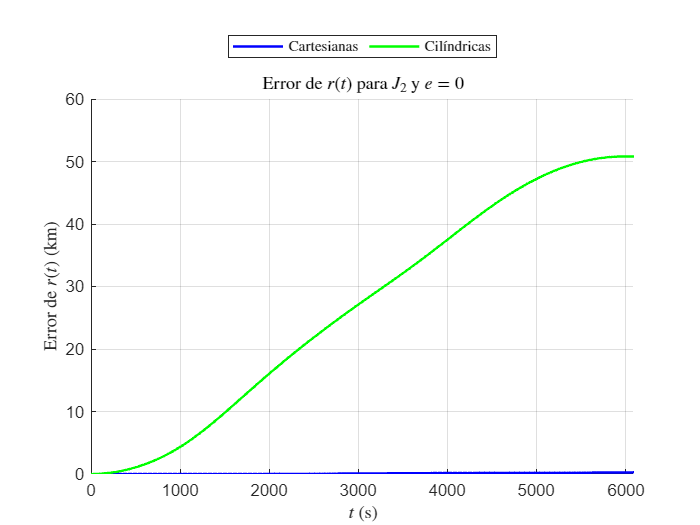

% Resolución
X0I = [x0I, y0I, z0I, dx0I, dy0I, dz0I];
opts = odeset('RelTol', 1e-12, 'AbsTol', 1e-5);

[~, dXdt_Kepler] = ode113(@(t, X) odeKepler(X, mu), t, X0I, opts);
dXdt = cowellZonals(X0I, t, mu, R, [J2; 0; 0; 0; 0], opts);

FAM   =  AM + dXdt_Kepler;
FCAM  = CAM + dXdt_Kepler;
rFAM  =  FAM(:, 1:3)/1e3;
rFCAM = FCAM(:, 1:3)/1e3;

r     = dXdt(:, 1:3)/1e3;

% Comparación
plotNumericErrorsNorm(rFAM, rFCAM, r, t, 'Cartesianas', 'Cil\''indricas', ...
    'Error de $r(t)$ para $J_2$ y $e = 0$', '$t$ (s)', 'Error de $r(t)$ (km)', 'b', 'g');